% 같은 SOH라도 입력패턴에 따라 SOH은 변경된다.
% 입력패턴만으로 SOH을 예측하기 힘들다.
% 현재 CNN / LSTM 을 입력패턴, 출력패턴으로 하는 것은 의미가 없는 것 같다.
% CNN / LSTM 에서는 개별 입력/출력 패턴이 아닌 전체 사이클이 입력되어야 한다.

% 선형회귀도 전제 사이클 입력에 따른 출력이 표현이 가능할까? 
% 모든 데이타가 합쳐지면 그냥 전체 데이타의 평균일 뿐이다. 오차도 매우 커질수 있다.

% 알고리즘
% SOH 를 예측한다.
% 입출력 패턴을 이용해서 SOH를 업데이트 한다.

% deltaRUL은 사용할 수 없다. 항상 1이므로 
% RUL을 계산하기 위해서는 아래 공식을 사용해야 한다. 
% current SOH * ( delta SOH) * n = eol SOH

% clear


% load ryan4_data.mat
% load ryan4_model_SOH.mat
%generate_model = true
 generate_model = false

generate_model = logical
   0


 save_model = false

save_model = logical
   0


if generate_model == false
    load ryan4_model_SOH.mat
end

# 필요한 데이타 로딩

%% https://kr.mathworks.com/help/matlab/ref/load.html

load('ryan4_data.mat','x_trainValid_Ic')
load('ryan4_data.mat','x_test_Ic_SOH')
load('ryan4_data.mat','xmin_Ic_SOH')
load('ryan4_data.mat','xrate_Ic_SOH')
load('ryan4_data.mat','xnorm_Ic')

load('ryan4_data.mat','x_trainValid_Vd')
load('ryan4_data.mat','x_test_Vd_SOH')
load('ryan4_data.mat','xmin_Vd_SOH')
load('ryan4_data.mat','xrate_Vd_SOH')
load('ryan4_data.mat','xnorm_Vd')

load('ryan4_data.mat','ynorm_SOH')
load('ryan4_data.mat','ymin_SOH')
load('ryan4_data.mat','yrate_SOH')

load('ryan4_data.mat','y_trainValid_SOH')
load('ryan4_data.mat','Y_trainValid_SOH')
load('ryan4_data.mat','y_test_SOH')
load('ryan4_data.mat','Y_test_SOH')
load('ryan4_data.mat','ymin_SOH')
load('ryan4_data.mat','yrate_SOH')

load('ryan4_data.mat','y_trainValid_DeltaSOH')
load('ryan4_data.mat','Y_trainValid_DeltaSOH')
load('ryan4_data.mat','y_test_DeltaSOH')
load('ryan4_data.mat','Y_test_DeltaSOH')
load('ryan4_data.mat','ymin_DeltaSOH')
load('ryan4_data.mat','yrate_DeltaSOH')

load('ryan4_data.mat','y_trainValid_DeltaRUL')
load('ryan4_data.mat','Y_trainValid_DeltaRUL')
load('ryan4_data.mat','y_test_DeltaRUL')
load('ryan4_data.mat','Y_test_DeltaRUL')
load('ryan4_data.mat','ymin_DeltaRUL')
load('ryan4_data.mat','yrate_DeltaRUL')

load('ryan4_data.mat','idxTrainAll')
load('ryan4_data.mat','idxValidAll')
load('ryan4_data.mat','idxTestAll')

load('ryan4_data.mat','idxTrain')
load('ryan4_data.mat','idxValid')
load('ryan4_data.mat','idxTest')

idxSearch = 1; % 316
idxSearch2 = 2; % 239

idxFind = idxTest(find(idxTest == idxTestSort(idxSearch)))

idxFind = 16

idxFindAll = find(idxTestAll_batIndex == idxFind)

idxFindAll =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


Y_test_SOH_test1 = Y_test_SOH(idxFindAll)

Y_test_SOH_test1 =     1.0477
    1.0476
    1.0474
    1.0473
    1.0471
    1.0470
    1.0468
    1.0467
    1.0465
    1.0464


idxFind2 = idxTest(find(idxTest == idxTestSort(idxSearch2)))

idxFind2 = 26

idxFindAll2 = find(idxTestAll_batIndex == idxFind2)

idxFindAll2 =    317   318   319   320   321   322   323   324   325   326   327   328   329   330   331   332   333   334   335   336   337   338   339   340   341   342   343   344   345   346   347   348   349   350   351   352   353   354   355   356   357   358   359   360   361   362   363   364   365   366


Y_test_SOH_test2 = Y_test_SOH(idxFindAll2)

Y_test_SOH_test2 =     1.0477
    1.0475
    1.0473
    1.0471
    1.0468
    1.0466
    1.0464
    1.0462
    1.0459
    1.0457


% Y_trainValid_SOH_DeltaSOH = [ Y_trainValid_SOH Y_trainValid_DeltaSOH ];
% Y_test_SOH_DeltaSOH = [ Y_test_SOH Y_test_DeltaSOH ];
% y_trainValid_SOH_DeltaSOH = [ y_trainValid_SOH y_trainValid_DeltaSOH ]; 
% y_test_SOH_DeltaSOH = [ y_test_SOH y_test_DeltaSOH ];
% ynorm_SOH_DeltaSOH = [ ynorm_SOH ynorm_DeltaSOH ];


# 머신러닝을 위한 기본 설정

epoc_count = 5;
epoc_count_lstm = 3;
%epoc_count = 10; % 시간이 너무 오래 걸린다.
cc_input_size = 20;
fnn_neuron_layer = 20;
fnn_neuron_layer3 = [40,20,10];

% 같은 SOH라도 입력패턴에 따라 SOH은 변경된다.
% 입력패턴만으로 SOH을 예측하기 힘들다.
% 현재 CNN / LSTM 을 입력패턴, 출력패턴으로 하는 것은 의미가 없는 것 같다.
% CNN / LSTM 에서는 개별 입력/출력 패턴이 아닌 전체 사이클이 입력되어야 한다.

% 선형회귀도 전제 사이클 입력에 따른 출력이 표현이 가능할까? 
% 모든 데이타가 합쳐지면 그냥 전체 데이타의 평균일 뿐이다. 오차도 매우 커질수 있다.

% 알고리즘
% SOH 를 예측한다.
% 입출력 패턴을 이용해서 SOH를 업데이트 한다.

% deltaRUL은 사용할 수 없다. 항상 1이므로 

# linear model create

# 선형회귀 - 모델 생성


%% https://kr.mathworks.com/help/matlab/ref/load.html
% load('ryan4_data.mat','x_trainValid_IcSOHFull_SOH','x_trainValid_Ic','y_trainValid_Ic_SOH')

if generate_model
    tic
    mdl_Linear_IcSOH = fitlm(x_trainValid_Ic,y_trainValid_SOH)
    toc 
    
    tic
    mdl_Linear_VdSOH = fitlm(x_trainValid_Vd,y_trainValid_SOH)
    toc

    tic
    mdl_Linear_IcDeltaSOH = fitlm(x_trainValid_Ic,y_trainValid_DeltaSOH)
    toc 
    
    tic
    mdl_Linear_VdDeltaSOH = fitlm(x_trainValid_Vd,y_trainValid_DeltaSOH)
    toc

%     tic
%     mdl_Linear_IcDeltaRUL = fitlm(x_trainValid_Ic,y_trainValid_DeltaRUL)
%     toc 
%     
%     tic
%     mdl_Linear_VdDeltaRUL = fitlm(x_trainValid_Vd,y_trainValid_DeltaRUL)
%     toc

    ryan4_model_SOH_desc = "ryan4_model_SOH_desc"
    %save('ryan4_model_SOH.mat','ryan4_model_SOH_desc' )
    save('ryan4_model_SOH.mat','mdl_Linear_IcSOH' ,'-append')
    save('ryan4_model_SOH.mat','mdl_Linear_VdSOH' ,'-append')
    save('ryan4_model_SOH.mat','mdl_Linear_IcDeltaSOH' ,'-append')
    save('ryan4_model_SOH.mat','mdl_Linear_VdDeltaSOH' ,'-append')
%     save('ryan4_model_SOH.mat','mdl_Linear_IcDeltaRUL' ,'-append')
%     save('ryan4_model_SOH.mat','mdl_Linear_VdDeltaRUL' ,'-append') 
    
end

if generate_model
    tic
    mdl_Linear_CapDeltaSohRul_fitrlinear = fitrlinear(y_trainValid_SOH_DeltaSOH,y_trainValid_RUL,"learner","leastsquares")
    toc    

    tic
    mdl_Linear_CapDeltaSohRul_fitrlinear_svm = fitrlinear(y_trainValid_SOH_DeltaSOH,y_trainValid_RUL,"learner","svm")
    toc  

    save('ryan4_model_SOH.mat','mdl_Linear_CapDeltaSohRul_fitrlinear' ,'-append')
    save('ryan4_model_SOH.mat','mdl_Linear_CapDeltaSohRul_fitrlinear_svm' ,'-append')    
end


yfit_trainValid_RUL = predict(mdl_Linear_CapDeltaSohRul_fitrlinear_svm,y_trainValid_SOH_DeltaSOH);
yfit_trainValid_RUL'

ans =     0.2705    0.2704    0.2703    0.2702    0.2702    0.2701    0.2700    0.2699    0.2697    0.2696    0.2695    0.2693    0.2692    0.2690    0.2689    0.2687    0.2685    0.2684    0.2683    0.2681    0.2680    0.2679    0.2678    0.2677    0.2676    0.2675    0.2674    0.2672    0.2671    0.2670    0.2668    0.2667    0.2665    0.2664    0.2662    0.2661    0.2659    0.2658    0.2656    0.2654    0.2652    0.2650    0.2648    0.2646    0.2644    0.2641    0.2639    0.2637    0.2635    0.2633


yfit_test_RUL = predict(mdl_Linear_CapDeltaSohRul_fitrlinear_svm,y_test_SOH_DeltaSOH);
yfit_test_RUL'

ans =     0.2631    0.2630    0.2628    0.2626    0.2625    0.2623    0.2620    0.2618    0.2615    0.2612    0.2608    0.2605    0.2601    0.2598    0.2594    0.2591    0.2588    0.2585    0.2582    0.2580    0.2578    0.2575    0.2573    0.2571    0.2568    0.2566    0.2563    0.2559    0.2556    0.2552    0.2548    0.2543    0.2538    0.2533    0.2528    0.2522    0.2516    0.2510    0.2503    0.2497    0.2490    0.2484    0.2478    0.2471    0.2467    0.2459    0.2453    0.2447    0.2441    0.2437



yfit_trainValid_RUL'

ans =     0.2705    0.2704    0.2703    0.2702    0.2702    0.2701    0.2700    0.2699    0.2697    0.2696    0.2695    0.2693    0.2692    0.2690    0.2689    0.2687    0.2685    0.2684    0.2683    0.2681    0.2680    0.2679    0.2678    0.2677    0.2676    0.2675    0.2674    0.2672    0.2671    0.2670    0.2668    0.2667    0.2665    0.2664    0.2662    0.2661    0.2659    0.2658    0.2656    0.2654    0.2652    0.2650    0.2648    0.2646    0.2644    0.2641    0.2639    0.2637    0.2635    0.2633


y_test_RUL'

ans =     0.2692    0.2684    0.2675    0.2667    0.2658    0.2650    0.2641    0.2632    0.2624    0.2615    0.2607    0.2598    0.2590    0.2581    0.2573    0.2564    0.2556    0.2547    0.2538    0.2530    0.2521    0.2513    0.2504    0.2496    0.2487    0.2479    0.2470    0.2462    0.2453    0.2444    0.2436    0.2427    0.2419    0.2410    0.2402    0.2393    0.2385    0.2376    0.2368    0.2359    0.2350    0.2342    0.2333    0.2325    0.2316    0.2308    0.2299    0.2291    0.2282    0.2274



Yfit_trainValid_RUL = yfit_trainValid_RUL * yrate_RUL + ymin_RUL;
Yfit_test_RUL = yfit_test_RUL * yrate_RUL + ymin_RUL;
%Y_test_RUL = y_test_Ic_RUL * yrate_Ic_RUL + ymin_Ic_RUL;


MAE_RUL = mean(abs(Yfit_trainValid_RUL-Y_trainValid_RUL))

MAE_RUL = 96.3617

adjMAE_RUL = MAE_RUL/range(Y_trainValid_RUL)

adjMAE_RUL = 0.0824

range(Y_trainValid_RUL) % Y_trainValid_RUL = range(X)는 X에 포함된 표본 데이터의 최댓값과 최솟값 간의 차이를 반환합니다.

ans = 1170


(Y_trainValid_RUL - Yfit_trainValid_RUL)'    % Errors

ans =   110.5126  109.6230  108.7173  107.8161  106.9193  106.0291  105.1470  104.2720  103.4067  102.5534  101.7094  100.8752  100.0519   99.2377   98.4283   97.6178   96.8004   95.9715   95.1287   94.2723   93.4069   92.5359   91.6603   90.7832   89.9090   89.0419   88.1797   87.3217   86.4678   85.6225   84.7882   83.9614   83.1384   82.3182   81.4986   80.6807   79.8675   79.0611   78.2645   77.4792   76.7034   75.9364   75.1782   74.4285   73.6863   72.9493   72.2137   71.4760   70.7351   69.9878


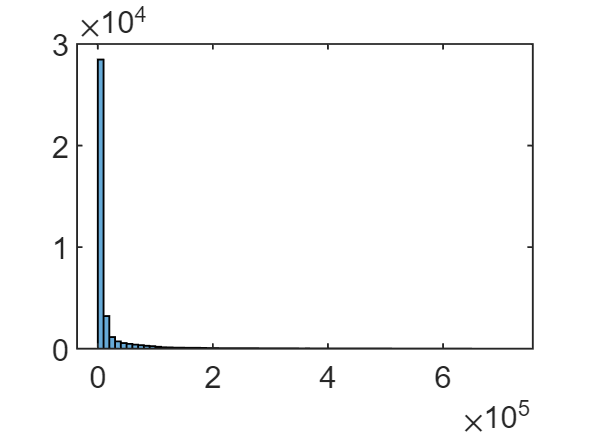

(Y_trainValid_RUL - Yfit_trainValid_RUL).^2;   % Squared Error
histogram((Y_trainValid_RUL - Yfit_trainValid_RUL).^2)

mean((Y_trainValid_RUL - Yfit_trainValid_RUL).^2);   % Mean Squared Error
RMSE_trainValid_RUL = sqrt(mean((Y_trainValid_RUL - Yfit_trainValid_RUL).^2))  % Root Mean Squared Error

RMSE_trainValid_RUL = 161.6589

Y_trainValid_diff_RUL = horzcat(Y_trainValid_RUL,(Y_trainValid_RUL-Yfit_trainValid_RUL))

Y_trainValid_diff_RUL = 1.0e+03 *

    0.4280    0.1105
    0.4270    0.1096
    0.4260    0.1087
    0.4250    0.1078
    0.4240    0.1069
    0.4230    0.1060
    0.4220    0.1051
    0.4210    0.1043
    0.4200    0.1034
    0.4190    0.1026


Y_trainValid_diff_percentage_RUL = abs(Y_trainValid_RUL-Yfit_trainValid_RUL)./Y_trainValid_RUL.*100

Y_trainValid_diff_percentage_RUL = 1.0e+04 *

    0.0026
    0.0026
    0.0026
    0.0025
    0.0025
    0.0025
    0.0025
    0.0025
    0.0025
    0.0024


Y_trainValid_diff_percentage_avg_RUL = sum(Y_trainValid_diff_percentage_RUL)/length(Y_trainValid_diff_percentage_RUL)

Y_trainValid_diff_percentage_avg_RUL = 133.8480

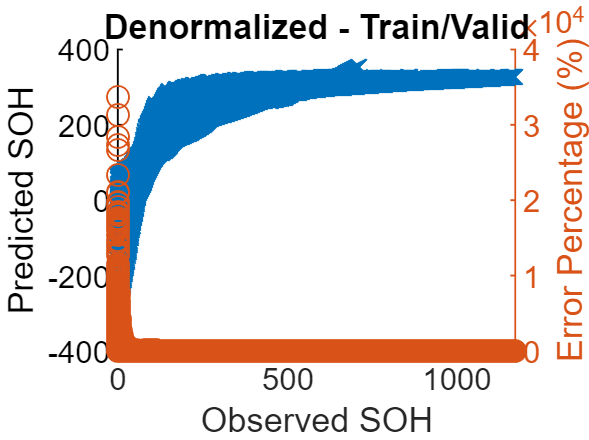

figure
hold on
plot(Y_trainValid_RUL,Yfit_trainValid_RUL,'x')
xlabel("Observed SOH")
ylabel("Predicted SOH")
%xlim([0 1.2]), ylim([0 1.2])

yyaxis right
ylabel('Error Percentage (%)')
plot(Y_trainValid_RUL,Y_trainValid_diff_percentage_RUL,'o');

hold off
title 'Denormalized - Train/Valid'


%%%%%%%%%%%%
RMSE_test_RUL = sqrt(mean((Y_test_RUL - Yfit_test_RUL).^2))

RMSE_test_RUL = 181.5800

Y_test_RUL - Yfit_test_RUL

ans =     7.1778
    6.3412
    5.5111
    4.7022
    3.9175
    3.1613
    2.4401
    1.7520
    1.0918
    0.4531


Y_test_diff_RUL = horzcat(Y_test_RUL,(Y_test_RUL-Yfit_test_RUL))

Y_test_diff_RUL = 1.0e+03 *

    0.3160    0.0072
    0.3150    0.0063
    0.3140    0.0055
    0.3130    0.0047
    0.3120    0.0039
    0.3110    0.0032
    0.3100    0.0024
    0.3090    0.0018
    0.3080    0.0011
    0.3070    0.0005


Y_test_diff_percentage_RUL = abs(Y_test_RUL-Yfit_test_RUL)./Y_test_RUL.*100

Y_test_diff_percentage_RUL = 1.0e+04 *

    0.0002
    0.0002
    0.0002
    0.0002
    0.0001
    0.0001
    0.0001
    0.0001
    0.0000
    0.0000


Y_test_diff_percentage_avg_RUL = sum(Y_test_diff_percentage_RUL)/length(Y_test_diff_percentage_RUL)

Y_test_diff_percentage_avg_RUL = 145.7157

num = 1:length(Y_test_RUL);


result = horzcat(num',Y_test_RUL,(Y_test_RUL-Yfit_test_RUL),Y_test_diff_percentage_RUL);
result % 배터리 번호 / SOH 관찰값 / 오차 / 오차 퍼센티지 

result = 1.0e+04 *

    0.0001    0.0316    0.0007    0.0002
    0.0002    0.0315    0.0006    0.0002
    0.0003    0.0314    0.0006    0.0002
    0.0004    0.0313    0.0005    0.0002
    0.0005    0.0312    0.0004    0.0001
    0.0006    0.0311    0.0003    0.0001
    0.0007    0.0310    0.0002    0.0001
    0.0008    0.0309    0.0002    0.0001
    0.0009    0.0308    0.0001    0.0000
    0.0010    0.0307    0.0000    0.0000


result_mdl_Linear_CapDeltaSohRul = table(num',Y_test_RUL,(Y_test_RUL-Yfit_test_RUL),Y_test_diff_percentage_RUL);
result_mdl_Linear_CapDeltaSohRul.Properties.VariableNames = {'bat num','SOH','오차','오차비율'};
result_mdl_Linear_CapDeltaSohRul

result_mdl_Linear_CapDeltaSohRul = 4488×4 table
    bat num    SOH      오차      오차비율
    _______    ___    ________    _______

       1       316      7.1778     2.2715
       2       315      6.3412     2.0131
       3       314      5.5111     1.7551
       4       313      4.7022     1.5023
       5       312      3.9175     1.2556
       6       311      3.1613     1.0165
       7       310      2.4401    0.78713
       8       309       1.752      0.567
       9       308      1.0918    0.35447
      10       307     0.45314     0.1476
      11       306    -0.16695    0.05456
      12       305    -0.76921     0.2522
      13       304     -1.3622    0.44809
      14       303     -1.9565    0.64573
      15       302     -2.5535    0.84552
      16       301     -3.1607     1.0501


result_mdl_Linear_CapDeltaSohRul_summary = table(RMSE_test_RUL,Y_test_diff_percentage_avg_RUL);
result_mdl_Linear_CapDeltaSohRul_summary.Properties.VariableNames = {'RMSE','평균오차비율'};
result_mdl_Linear_CapDeltaSohRul_summary 

result_mdl_Linear_CapDeltaSohRul_summary = 1×2 table
     RMSE     평균오차비율
    ______    __________

    181.58      145.72  




RMSE_test_RUL

RMSE_test_RUL = 181.5800

Y_test_diff_percentage_avg_RUL

Y_test_diff_percentage_avg_RUL = 145.7157

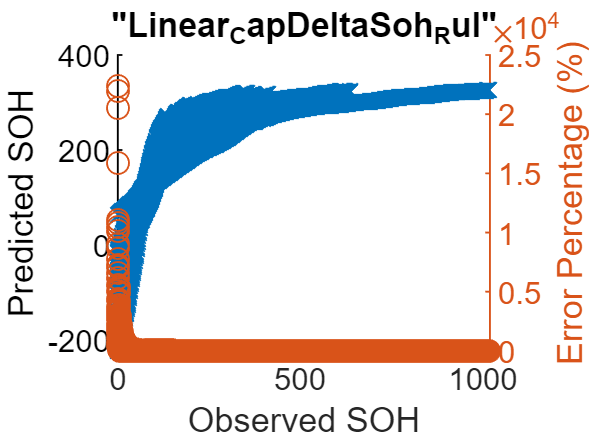


figure
hold on
plot(Y_test_RUL,Yfit_test_RUL,'x')
xlabel("Observed SOH")
ylabel("Predicted SOH")
%xlim([0 1.2]), ylim([0 1.2])

yyaxis right
ylabel('Error Percentage (%)')
plot(Y_test_RUL,Y_test_diff_percentage_RUL,'o');

hold off
title "Linear_CapDeltaSoh_Rul"

# fnn model create - 20 

# FNN 모델 생성 - 신형회귀와 동일한 20개 뉴런

# mdl_Fnn_CapDeltaSohRul 

if generate_model
   
    mdl_Fnn_CapDeltaSohRul = feedforwardnet(fnn_neuron_layer); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
    mdl_Fnn_CapDeltaSohRul.divideFcn = 'divideind';
    mdl_Fnn_CapDeltaSohRul.divideParam.trainInd = idxTrainAll;
    mdl_Fnn_CapDeltaSohRul.divideParam.valInd = idxValidAll;
    mdl_Fnn_CapDeltaSohRul.divideParam.testInd = idxTestAll; 
    mdl_Fnn_CapDeltaSohRul.trainParam.showWindow = 0; 
    mdl_Fnn_CapDeltaSohRul.trainParam.epochs = epoc_count; % 전체 데이타를 300번 반복 이용해라
    tic
    [mdl_Fnn_CapDeltaSohRul ] = train(mdl_Fnn_CapDeltaSohRul, ynorm_SOH_DeltaSOH', ynorm_RUL', 'useparallel',  'yes');
    toc
    
    save('ryan4_model_SOH.mat','mdl_Fnn_CapDeltaSohRul' ,'-append')

end 

# mdl_Fnn_CapDeltaSohRul - test

yfit_trainValid_RUL = mdl_Fnn_CapDeltaSohRul(y_trainValid_SOH_DeltaSOH')';
yfit_trainValid_RUL'

ans =     0.4149    0.4149    0.4150    0.4151    0.4151    0.4151    0.4150    0.4148    0.4145    0.4142    0.4138    0.4132    0.4126    0.4119    0.4112    0.4105    0.4098    0.4093    0.4089    0.4086    0.4083    0.4082    0.4080    0.4079    0.4078    0.4076    0.4073    0.4070    0.4067    0.4063    0.4058    0.4053    0.4047    0.4041    0.4035    0.4029    0.4022    0.4015    0.4007    0.3998    0.3988    0.3978    0.3967    0.3955    0.3943    0.3930    0.3917    0.3905    0.3893    0.3881


yfit_test_RUL = mdl_Fnn_CapDeltaSohRul(y_test_SOH_DeltaSOH')';
yfit_test_RUL'

ans =     0.3441    0.3441    0.3440    0.3437    0.3433    0.3426    0.3417    0.3406    0.3392    0.3377    0.3361    0.3344    0.3326    0.3308    0.3291    0.3274    0.3260    0.3247    0.3237    0.3229    0.3222    0.3215    0.3209    0.3202    0.3194    0.3184    0.3172    0.3157    0.3140    0.3121    0.3100    0.3076    0.3050    0.3022    0.2992    0.2960    0.2926    0.2892    0.2857    0.2822    0.2788    0.2755    0.2722    0.2691    0.2673    0.2630    0.2602    0.2575    0.2550    0.2530



yfit_trainValid_RUL'

ans =     0.4149    0.4149    0.4150    0.4151    0.4151    0.4151    0.4150    0.4148    0.4145    0.4142    0.4138    0.4132    0.4126    0.4119    0.4112    0.4105    0.4098    0.4093    0.4089    0.4086    0.4083    0.4082    0.4080    0.4079    0.4078    0.4076    0.4073    0.4070    0.4067    0.4063    0.4058    0.4053    0.4047    0.4041    0.4035    0.4029    0.4022    0.4015    0.4007    0.3998    0.3988    0.3978    0.3967    0.3955    0.3943    0.3930    0.3917    0.3905    0.3893    0.3881


y_test_RUL'

ans =     0.2692    0.2684    0.2675    0.2667    0.2658    0.2650    0.2641    0.2632    0.2624    0.2615    0.2607    0.2598    0.2590    0.2581    0.2573    0.2564    0.2556    0.2547    0.2538    0.2530    0.2521    0.2513    0.2504    0.2496    0.2487    0.2479    0.2470    0.2462    0.2453    0.2444    0.2436    0.2427    0.2419    0.2410    0.2402    0.2393    0.2385    0.2376    0.2368    0.2359    0.2350    0.2342    0.2333    0.2325    0.2316    0.2308    0.2299    0.2291    0.2282    0.2274



Yfit_trainValid_RUL = yfit_trainValid_RUL * yrate_RUL + ymin_RUL;
Yfit_test_RUL = yfit_test_RUL * yrate_RUL + ymin_RUL;
%Y_test_RUL = y_test_Ic_RUL * yrate_Ic_RUL + ymin_Ic_RUL;


MAE_RUL = mean(abs(Yfit_trainValid_RUL-Y_trainValid_RUL))

MAE_RUL = 58.7298

adjMAE_RUL = MAE_RUL/range(Y_trainValid_RUL)

adjMAE_RUL = 0.0502

range(Y_trainValid_RUL) % Y_trainValid_RUL = range(X)는 X에 포함된 표본 데이터의 최댓값과 최솟값 간의 차이를 반환합니다.

ans = 1170


(Y_trainValid_RUL - Yfit_trainValid_RUL)'    % Errors

ans =   -58.4193  -59.3874  -60.5226  -61.6089  -62.6486  -63.6177  -64.5023  -65.3130  -66.0217  -66.6072  -67.0977  -67.4881  -67.7695  -67.9590  -68.1037  -68.2653  -68.5035  -68.8638  -69.3699  -70.0187  -70.7619  -71.5621  -72.4099  -73.2730  -74.1053  -74.8638  -75.5726  -76.2377  -76.8620  -77.3977  -77.8233  -78.1740  -78.4878  -78.7774  -79.0626  -79.3346  -79.5624  -79.7240  -79.7911  -79.7480  -79.6157  -79.4004  -79.1050  -78.7328  -78.2944  -77.8140  -77.3302  -76.8771  -76.4659  -76.1287


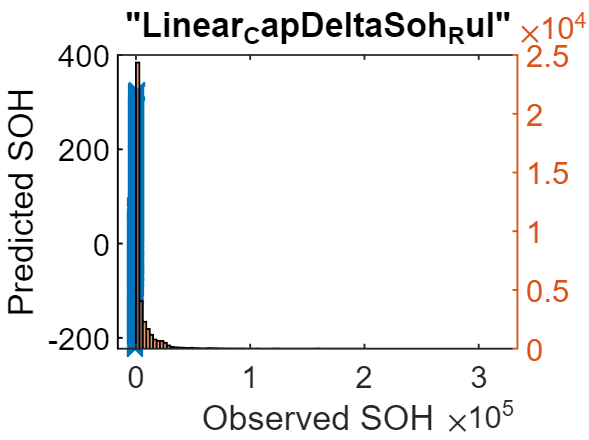

(Y_trainValid_RUL - Yfit_trainValid_RUL).^2;   % Squared Error
histogram((Y_trainValid_RUL - Yfit_trainValid_RUL).^2)

mean((Y_trainValid_RUL - Yfit_trainValid_RUL).^2);   % Mean Squared Error
RMSE_trainValid_RUL = sqrt(mean((Y_trainValid_RUL - Yfit_trainValid_RUL).^2))  % Root Mean Squared Error

RMSE_trainValid_RUL = 93.2475

Y_trainValid_diff_RUL = horzcat(Y_trainValid_RUL,(Y_trainValid_RUL-Yfit_trainValid_RUL))

Y_trainValid_diff_RUL = 1.0e+03 *

    0.4280   -0.0584
    0.4270   -0.0594
    0.4260   -0.0605
    0.4250   -0.0616
    0.4240   -0.0626
    0.4230   -0.0636
    0.4220   -0.0645
    0.4210   -0.0653
    0.4200   -0.0660
    0.4190   -0.0666


Y_trainValid_diff_percentage_RUL = abs(Y_trainValid_RUL-Yfit_trainValid_RUL)./Y_trainValid_RUL.*100

Y_trainValid_diff_percentage_RUL = 1.0e+04 *

    0.0014
    0.0014
    0.0014
    0.0014
    0.0015
    0.0015
    0.0015
    0.0016
    0.0016
    0.0016


Y_trainValid_diff_percentage_avg_RUL = sum(Y_trainValid_diff_percentage_RUL)/length(Y_trainValid_diff_percentage_RUL)

Y_trainValid_diff_percentage_avg_RUL = 45.8623

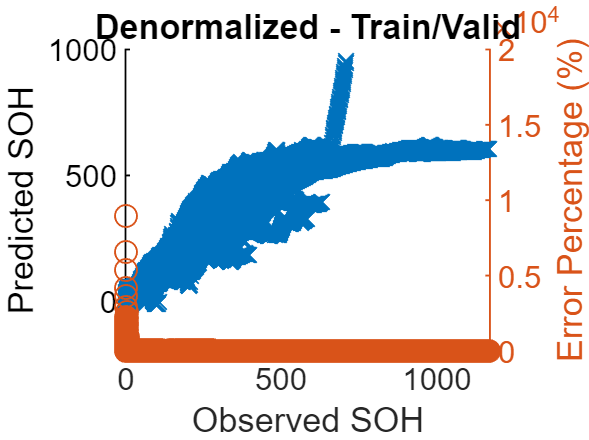

figure
hold on
plot(Y_trainValid_RUL,Yfit_trainValid_RUL,'x')
xlabel("Observed SOH")
ylabel("Predicted SOH")
%xlim([0 1.2]), ylim([0 1.2])

yyaxis right
ylabel('Error Percentage (%)')
plot(Y_trainValid_RUL,Y_trainValid_diff_percentage_RUL,'o');

hold off
title 'Denormalized - Train/Valid'


%%%%%%%%%%%%
RMSE_test_RUL = sqrt(mean((Y_test_RUL - Yfit_test_RUL).^2))

RMSE_test_RUL = 102.4717

Y_test_RUL - Yfit_test_RUL

ans =   -87.5969
  -88.5520
  -89.4487
  -90.1566
  -90.6495
  -90.8919
  -90.8283
  -90.4796
  -89.8972
  -89.1397


Y_test_diff_RUL = horzcat(Y_test_RUL,(Y_test_RUL-Yfit_test_RUL))

Y_test_diff_RUL = 1.0e+03 *

    0.3160   -0.0876
    0.3150   -0.0886
    0.3140   -0.0894
    0.3130   -0.0902
    0.3120   -0.0906
    0.3110   -0.0909
    0.3100   -0.0908
    0.3090   -0.0905
    0.3080   -0.0899
    0.3070   -0.0891


Y_test_diff_percentage_RUL = abs(Y_test_RUL-Yfit_test_RUL)./Y_test_RUL.*100

Y_test_diff_percentage_RUL = 1.0e+03 *

    0.0277
    0.0281
    0.0285
    0.0288
    0.0291
    0.0292
    0.0293
    0.0293
    0.0292
    0.0290


Y_test_diff_percentage_avg_RUL = sum(Y_test_diff_percentage_RUL)/length(Y_test_diff_percentage_RUL)

Y_test_diff_percentage_avg_RUL = 42.6343

num = 1:length(Y_test_RUL);


result = horzcat(num',Y_test_RUL,(Y_test_RUL-Yfit_test_RUL),Y_test_diff_percentage_RUL);
result % 배터리 번호 / SOH 관찰값 / 오차 / 오차 퍼센티지 

result = 1.0e+03 *

    0.0010    0.3160   -0.0876    0.0277
    0.0020    0.3150   -0.0886    0.0281
    0.0030    0.3140   -0.0894    0.0285
    0.0040    0.3130   -0.0902    0.0288
    0.0050    0.3120   -0.0906    0.0291
    0.0060    0.3110   -0.0909    0.0292
    0.0070    0.3100   -0.0908    0.0293
    0.0080    0.3090   -0.0905    0.0293
    0.0090    0.3080   -0.0899    0.0292
    0.0100    0.3070   -0.0891    0.0290


result_mdl_Fnn_CapDeltaSohRul = table(num',Y_test_RUL,(Y_test_RUL-Yfit_test_RUL),Y_test_diff_percentage_RUL);
result_mdl_Fnn_CapDeltaSohRul.Properties.VariableNames = {'bat num','SOH','오차','오차비율'};
result_mdl_Fnn_CapDeltaSohRul

result_mdl_Fnn_CapDeltaSohRul = 4488×4 table
    bat num    SOH     오차      오차비율
    _______    ___    _______    _______

       1       316    -87.597    27.721 
       2       315    -88.552    28.112 
       3       314    -89.449    28.487 
       4       313    -90.157    28.804 
       5       312    -90.649    29.054 
       6       311    -90.892    29.226 
       7       310    -90.828    29.299 
       8       309     -90.48    29.281 
       9       308    -89.897    29.187 
      10       307     -89.14    29.036 
      11       306    -88.237    28.836 
      12       305    -87.199     28.59 
      13       304    -86.102    28.323 
      14       303    -85.039    28.066 
      15       302     -84.02    27.821 
      16       301    -83.111    27.612 


result_mdl_Fnn_CapDeltaSohRul_summary = table(RMSE_test_RUL,Y_test_diff_percentage_avg_RUL);
result_mdl_Fnn_CapDeltaSohRul_summary.Properties.VariableNames = {'RMSE','평균오차비율'};
result_mdl_Fnn_CapDeltaSohRul_summary 

result_mdl_Fnn_CapDeltaSohRul_summary = 1×2 table
     RMSE     평균오차비율
    ______    __________

    102.47      42.634  




RMSE_test_RUL

RMSE_test_RUL = 102.4717

Y_test_diff_percentage_avg_RUL

Y_test_diff_percentage_avg_RUL = 42.6343

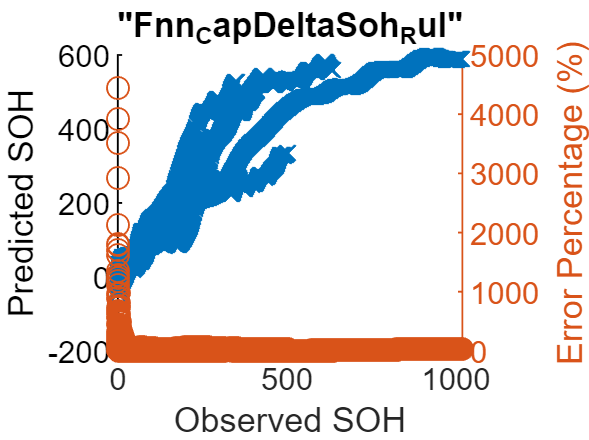


figure
hold on
plot(Y_test_RUL,Yfit_test_RUL,'x')
xlabel("Observed SOH")
ylabel("Predicted SOH")
%xlim([0 1.2]), ylim([0 1.2])

yyaxis right
ylabel('Error Percentage (%)')
plot(Y_test_RUL,Y_test_diff_percentage_RUL,'o');

hold off
title "Fnn_CapDeltaSoh_Rul"


% idxTestAll
% idxTestAll_batIndex  % 16 ... 26 ...
% idxTestAll_batIndex1 = (idxTestAll_batIndex == 16)
% idxTestAll_batIndex2 = (idxTestAll_batIndex == 26)
% idxTest
% idxAll
% %  1     2   3   4   5   6  7 
% % 76	48	62	28	26	47	16	99	92	106	84	119
% 
% idxTestAll_test1 = idxTestAll(find(idxTestAll_batIndex == idxTest(7)))
% idxTestAll_test2 = idxTestAll(find(idxTestAll_batIndex == idxTest(5)))
% 
% Y_test_RUL_test1 = Y_test_RUL(find(idxTestAll_batIndex == idxTest(7)))
% Y_test_RUL_test2 = Y_test_RUL(find(idxTestAll_batIndex == idxTest(5)))
% 
% RUL_test1 = RUL(idxTestAll_test1)
% RUL_test2 = RUL(idxTestAll_test2)
% %Y_test_RUL_test11 = Y_test_RUL(idxTestAll_test1) % not work
% %Y_test_RUL_test22 = Y_test_RUL(idxTestAll_test1) % not work
% 
% %CapRUL(idxTestAll_test1)

idxTestSort(1)

ans = 16

idxTest(7)

ans = 16

find(idxTest == idxTestSort(1))

ans = 7


idxSearch = 1; % 316
idxSearch2 = 2; % 239

idxFind = idxTest(find(idxTest == idxTestSort(idxSearch)))

idxFind = 16

idxFindAll = find(idxTestAll_batIndex == idxFind)

idxFindAll =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


Y_test_RUL_test1 = Y_test_RUL(idxFindAll)

Y_test_RUL_test1 =    316
   315
   314
   313
   312
   311
   310
   309
   308
   307


Y_test_SOH_test1 = Y_test_SOH(idxFindAll)

Y_test_SOH_test1 =     1.0477
    1.0476
    1.0474
    1.0473
    1.0471
    1.0470
    1.0468
    1.0467
    1.0465
    1.0464


Yfit_test_RUL_test1 = Yfit_test_RUL(idxFindAll)

Yfit_test_RUL_test1 =   403.5969
  403.5520
  403.4487
  403.1566
  402.6495
  401.8919
  400.8283
  399.4796
  397.8972
  396.1397



idxFind2 = idxTest(find(idxTest == idxTestSort(idxSearch2)))

idxFind2 = 26

idxFindAll2 = find(idxTestAll_batIndex == idxFind2)

idxFindAll2 =    317   318   319   320   321   322   323   324   325   326   327   328   329   330   331   332   333   334   335   336   337   338   339   340   341   342   343   344   345   346   347   348   349   350   351   352   353   354   355   356   357   358   359   360   361   362   363   364   365   366


Y_test_RUL_test2 = Y_test_RUL(idxFindAll2)

Y_test_RUL_test2 =    239
   238
   237
   236
   235
   234
   233
   232
   231
   230


Yfit_test_RUL_test2 = Yfit_test_RUL(idxFindAll2)

Yfit_test_RUL_test2 =   323.0816
  323.0588
  317.8272
  312.7566
  307.8903
  303.2803
  298.9460
  294.9129
  291.1495
  287.5495


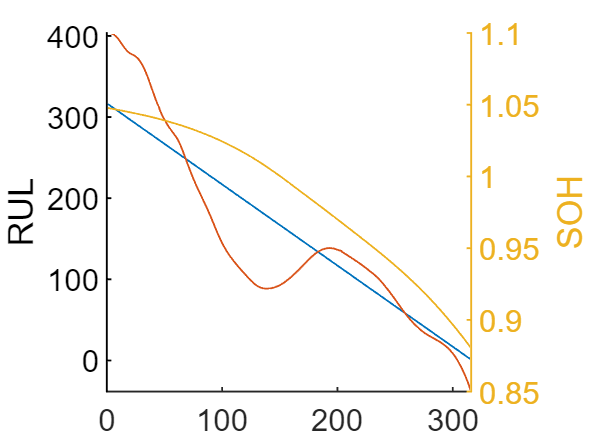



figure, hold on
plot(Y_test_RUL_test1)
plot(Yfit_test_RUL_test1)
ylabel('RUL')

yyaxis right
ylabel('SOH')
plot(Y_test_SOH_test1)
hold off

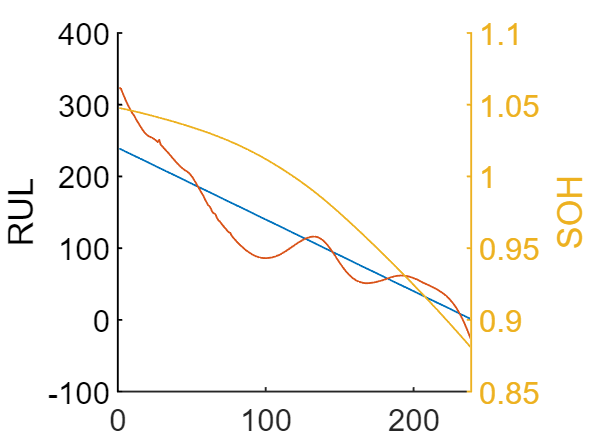


figure, hold on
plot(Y_test_RUL_test2)
plot(Yfit_test_RUL_test2)
ylabel('RUL')

yyaxis right
ylabel('SOH')
plot(Y_test_SOH_test2)
hold off

if generate_model
    mdl_Fnn_IcSOH = feedforwardnet(fnn_neuron_layer); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
    mdl_Fnn_IcSOH.divideFcn = 'divideind';
    mdl_Fnn_IcSOH.divideParam.trainInd = idxTrainAll;
    mdl_Fnn_IcSOH.divideParam.valInd = idxValidAll;
    mdl_Fnn_IcSOH.divideParam.testInd = idxTestAll; 
    mdl_Fnn_IcSOH.trainParam.showWindow = 0; 
    mdl_Fnn_IcSOH.trainParam.epochs = epoc_count; % 전체 데이타를 300번 반복 이용해라
    tic
    [mdl_Fnn_IcSOH ] = train(mdl_Fnn_IcSOH, xnorm_Ic', ynorm_SOH', 'useparallel',  'yes');
    toc

    mdl_Fnn_VdSOH = feedforwardnet(fnn_neuron_layer); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
    mdl_Fnn_VdSOH.divideFcn = 'divideind';
    mdl_Fnn_VdSOH.divideParam.trainInd = idxTrainAll;
    mdl_Fnn_VdSOH.divideParam.valInd = idxValidAll;
    mdl_Fnn_VdSOH.divideParam.testInd = idxTestAll; 
        
    %netFNN1__1.divideParam
    % https://kr.mathworks.com/matlabcentral/answers/314483-how-to-disable-popup-of-training-windows-for-neural-network-in-matlab
    mdl_Fnn_VdSOH.trainParam.showWindow = 0; 
    mdl_Fnn_VdSOH.trainParam.epochs = epoc_count; % 전체 데이타를 300번 반복 이용해라
    tic
    [mdl_Fnn_VdSOH ] = train(mdl_Fnn_VdSOH, xnorm_Vd', ynorm_SOH', 'useparallel',  'yes');
    toc

    %%%%%%%%%%%
    mdl_Fnn_IcDeltaSOH = feedforwardnet(fnn_neuron_layer); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
    mdl_Fnn_IcDeltaSOH.divideFcn = 'divideind';
    mdl_Fnn_IcDeltaSOH.divideParam.trainInd = idxTrainAll;
    mdl_Fnn_IcDeltaSOH.divideParam.valInd = idxValidAll;
    mdl_Fnn_IcDeltaSOH.divideParam.testInd = idxTestAll; 
        
    %netFNN1__1.divideParam
    % https://kr.mathworks.com/matlabcentral/answers/314483-how-to-disable-popup-of-training-windows-for-neural-network-in-matlab
    mdl_Fnn_IcDeltaSOH.trainParam.showWindow = 0; 
    mdl_Fnn_IcDeltaSOH.trainParam.epochs = epoc_count; % 전체 데이타를 300번 반복 이용해라
    tic
    [mdl_Fnn_IcDeltaSOH ] = train(mdl_Fnn_IcDeltaSOH, xnorm_Ic', ynorm_DeltaSOH', 'useparallel',  'yes');
    toc

    mdl_Fnn_VdDeltaSOH = feedforwardnet(fnn_neuron_layer); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
    mdl_Fnn_VdDeltaSOH.divideFcn = 'divideind';
    mdl_Fnn_VdDeltaSOH.divideParam.trainInd = idxTrainAll;
    mdl_Fnn_VdDeltaSOH.divideParam.valInd = idxValidAll;
    mdl_Fnn_VdDeltaSOH.divideParam.testInd = idxTestAll; 
        
    %netFNN1__1.divideParam
    % https://kr.mathworks.com/matlabcentral/answers/314483-how-to-disable-popup-of-training-windows-for-neural-network-in-matlab
    mdl_Fnn_VdDeltaSOH.trainParam.showWindow = 0; 
    mdl_Fnn_VdDeltaSOH.trainParam.epochs = epoc_count; % 전체 데이타를 300번 반복 이용해라
    tic
    [mdl_Fnn_VdDeltaSOH ] = train(mdl_Fnn_VdDeltaSOH, xnorm_Vd', ynorm_DeltaSOH', 'useparallel',  'yes');
    toc

    save('ryan4_model_SOH.mat','mdl_Fnn_IcSOH' ,'-append')
    save('ryan4_model_SOH.mat','mdl_Fnn_VdSOH' ,'-append')    
    save('ryan4_model_SOH.mat','mdl_Fnn_IcDeltaSOH' ,'-append')
    save('ryan4_model_SOH.mat','mdl_Fnn_VdDeltaSOH' ,'-append')        
end

% if generate_model
%     mdl_Fnn_IcDeltaRUL = feedforwardnet(fnn_neuron_layer); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
%     mdl_Fnn_IcDeltaRUL.divideFcn = 'divideind';
%     mdl_Fnn_IcDeltaRUL.divideParam.trainInd = idxTrainAll;
%     mdl_Fnn_IcDeltaRUL.divideParam.valInd = idxValidAll;
%     mdl_Fnn_IcDeltaRUL.divideParam.testInd = idxTestAll; 
%         
%     %netFNN1__1.divideParam
%     % https://kr.mathworks.com/matlabcentral/answers/314483-how-to-disable-popup-of-training-windows-for-neural-network-in-matlab
%     mdl_Fnn_IcDeltaRUL.trainParam.showWindow = 0; 
%     mdl_Fnn_IcDeltaRUL.trainParam.epochs = epoc_count; % 전체 데이타를 300번 반복 이용해라
%     tic
%     [mdl_Fnn_IcDeltaRUL ] = train(mdl_Fnn_IcDeltaRUL, xnorm_Ic', ynorm_DeltaRUL', 'useparallel',  'yes');
%     toc
% 
%     mdl_Fnn_VdDeltaRUL = feedforwardnet(fnn_neuron_layer); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
%     mdl_Fnn_VdDeltaRUL.divideFcn = 'divideind';
%     mdl_Fnn_VdDeltaRUL.divideParam.trainInd = idxTrainAll;
%     mdl_Fnn_VdDeltaRUL.divideParam.valInd = idxValidAll;
%     mdl_Fnn_VdDeltaRUL.divideParam.testInd = idxTestAll; 
%         
%     %netFNN1__1.divideParam
%     % https://kr.mathworks.com/matlabcentral/answers/314483-how-to-disable-popup-of-training-windows-for-neural-network-in-matlab
%     mdl_Fnn_VdDeltaRUL.trainParam.showWindow = 0; 
%     mdl_Fnn_VdDeltaRUL.trainParam.epochs = epoc_count; % 전체 데이타를 300번 반복 이용해라
%     tic
%     [mdl_Fnn_VdDeltaRUL ] = train(mdl_Fnn_VdDeltaRUL, xnorm_Vd', ynorm_DeltaRUL', 'useparallel',  'yes');
%     toc
%   
%     save('ryan4_model_SOH.mat','mdl_Fnn_IcDeltaRUL' ,'-append')
%     save('ryan4_model_SOH.mat','mdl_Fnn_VdDeltaRUL' ,'-append')        
% end

# FNN 모델 생성 - 3개 layer로 더 deep하게 -  40 20 10개 뉴런

if generate_model
    
    mdl_Fnn3_CapDeltaSohRul = feedforwardnet(fnn_neuron_layer3); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
    mdl_Fnn3_CapDeltaSohRul.divideFcn = 'divideind';
    mdl_Fnn3_CapDeltaSohRul.divideParam.trainInd = idxTrainAll;
    mdl_Fnn3_CapDeltaSohRul.divideParam.valInd = idxValidAll;
    mdl_Fnn3_CapDeltaSohRul.divideParam.testInd = idxTestAll; 
    mdl_Fnn3_CapDeltaSohRul.trainParam.showWindow = 0; 
    mdl_Fnn3_CapDeltaSohRul.trainParam.epochs = epoc_count; % 전체 데이타를 300번 반복 이용해라
    tic
    [mdl_Fnn3_CapDeltaSohRul ] = train(mdl_Fnn3_CapDeltaSohRul, ynorm_SOH_DeltaSOH', ynorm_RUL', 'useparallel',  'yes');
    toc

    save('ryan4_model_SOH.mat','mdl_Fnn3_CapDeltaSohRul' ,'-append')
end



yfit_trainValid_RUL = mdl_Fnn3_CapDeltaSohRul(y_trainValid_SOH_DeltaSOH')';
yfit_trainValid_RUL'

ans =     0.3112    0.3113    0.3117    0.3120    0.3122    0.3123    0.3123    0.3123    0.3120    0.3116    0.3110    0.3104    0.3095    0.3085    0.3075    0.3065    0.3057    0.3049    0.3044    0.3041    0.3040    0.3039    0.3039    0.3039    0.3038    0.3037    0.3035    0.3032    0.3029    0.3024    0.3018    0.3011    0.3004    0.2996    0.2989    0.2981    0.2973    0.2964    0.2953    0.2942    0.2929    0.2915    0.2901    0.2886    0.2870    0.2853    0.2837    0.2822    0.2807    0.2793


yfit_test_RUL = mdl_Fnn3_CapDeltaSohRul(y_test_SOH_DeltaSOH')';
yfit_test_RUL'

ans =     0.2273    0.2274    0.2274    0.2274    0.2272    0.2268    0.2262    0.2255    0.2246    0.2237    0.2226    0.2215    0.2204    0.2194    0.2184    0.2174    0.2166    0.2160    0.2155    0.2151    0.2148    0.2145    0.2143    0.2140    0.2137    0.2132    0.2126    0.2119    0.2111    0.2102    0.2092    0.2081    0.2070    0.2058    0.2045    0.2032    0.2019    0.2006    0.1994    0.1983    0.1972    0.1962    0.1953    0.1945    0.1941    0.1931    0.1925    0.1920    0.1915    0.1912



yfit_trainValid_RUL'

ans =     0.3112    0.3113    0.3117    0.3120    0.3122    0.3123    0.3123    0.3123    0.3120    0.3116    0.3110    0.3104    0.3095    0.3085    0.3075    0.3065    0.3057    0.3049    0.3044    0.3041    0.3040    0.3039    0.3039    0.3039    0.3038    0.3037    0.3035    0.3032    0.3029    0.3024    0.3018    0.3011    0.3004    0.2996    0.2989    0.2981    0.2973    0.2964    0.2953    0.2942    0.2929    0.2915    0.2901    0.2886    0.2870    0.2853    0.2837    0.2822    0.2807    0.2793


y_test_RUL'

ans =     0.2692    0.2684    0.2675    0.2667    0.2658    0.2650    0.2641    0.2632    0.2624    0.2615    0.2607    0.2598    0.2590    0.2581    0.2573    0.2564    0.2556    0.2547    0.2538    0.2530    0.2521    0.2513    0.2504    0.2496    0.2487    0.2479    0.2470    0.2462    0.2453    0.2444    0.2436    0.2427    0.2419    0.2410    0.2402    0.2393    0.2385    0.2376    0.2368    0.2359    0.2350    0.2342    0.2333    0.2325    0.2316    0.2308    0.2299    0.2291    0.2282    0.2274



Yfit_trainValid_RUL = yfit_trainValid_RUL * yrate_RUL + ymin_RUL;
Yfit_test_RUL = yfit_test_RUL * yrate_RUL + ymin_RUL;
%Y_test_RUL = y_test_Ic_RUL * yrate_Ic_RUL + ymin_Ic_RUL;


MAE_RUL = mean(abs(Yfit_trainValid_RUL-Y_trainValid_RUL))

MAE_RUL = 47.2085

adjMAE_RUL = MAE_RUL/range(Y_trainValid_RUL)

adjMAE_RUL = 0.0403

range(Y_trainValid_RUL) % Y_trainValid_RUL = range(X)는 X에 포함된 표본 데이터의 최댓값과 최솟값 간의 차이를 반환합니다.

ans = 1170


(Y_trainValid_RUL - Yfit_trainValid_RUL)'    % Errors

ans =    62.9237   61.7727   60.3409   58.9904   57.7176   56.5632   55.5506   54.6619   53.9440   53.4317   53.0763   52.8848   52.8701   53.0012   53.1985   53.3599   53.3888   53.2138   52.7988   52.1512   51.3498   50.4556   49.4839   48.4866   47.5379   46.7069   45.9544   45.2706   44.6505   44.1699   43.8617   43.6686   43.5288   43.4217   43.3160   43.2250   43.1968   43.2639   43.4678   43.8296   44.3140   44.9080   45.6044   46.3946   47.2597   48.1622   49.0452   49.8612   50.5962   51.2086


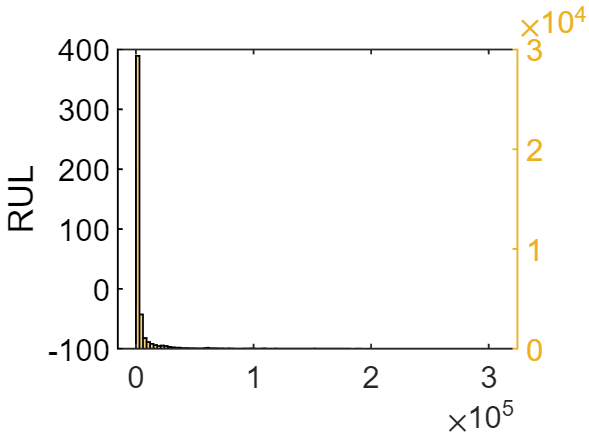

(Y_trainValid_RUL - Yfit_trainValid_RUL).^2;   % Squared Error
histogram((Y_trainValid_RUL - Yfit_trainValid_RUL).^2)

mean((Y_trainValid_RUL - Yfit_trainValid_RUL).^2);   % Mean Squared Error
RMSE_trainValid_RUL = sqrt(mean((Y_trainValid_RUL - Yfit_trainValid_RUL).^2))  % Root Mean Squared Error

RMSE_trainValid_RUL = 84.7343

Y_trainValid_diff_RUL = horzcat(Y_trainValid_RUL,(Y_trainValid_RUL-Yfit_trainValid_RUL))

Y_trainValid_diff_RUL = 1.0e+03 *

    0.4280    0.0629
    0.4270    0.0618
    0.4260    0.0603
    0.4250    0.0590
    0.4240    0.0577
    0.4230    0.0566
    0.4220    0.0556
    0.4210    0.0547
    0.4200    0.0539
    0.4190    0.0534


Y_trainValid_diff_percentage_RUL = abs(Y_trainValid_RUL-Yfit_trainValid_RUL)./Y_trainValid_RUL.*100

Y_trainValid_diff_percentage_RUL = 1.0e+03 *

    0.0147
    0.0145
    0.0142
    0.0139
    0.0136
    0.0134
    0.0132
    0.0130
    0.0128
    0.0128


Y_trainValid_diff_percentage_avg_RUL = sum(Y_trainValid_diff_percentage_RUL)/length(Y_trainValid_diff_percentage_RUL)

Y_trainValid_diff_percentage_avg_RUL = 44.5468

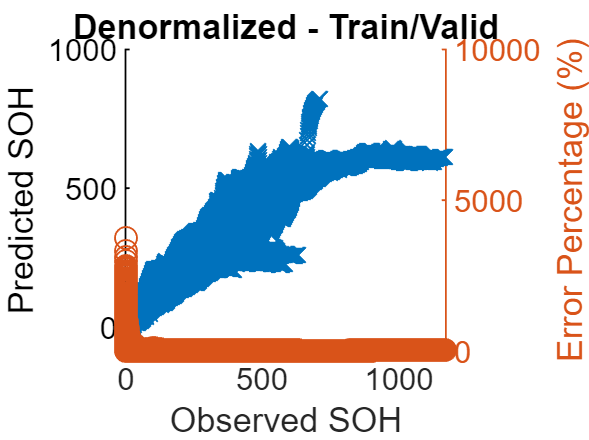

figure
hold on
plot(Y_trainValid_RUL,Yfit_trainValid_RUL,'x')
xlabel("Observed SOH")
ylabel("Predicted SOH")
%xlim([0 1.2]), ylim([0 1.2])

yyaxis right
ylabel('Error Percentage (%)')
plot(Y_trainValid_RUL,Y_trainValid_diff_percentage_RUL,'o');

hold off
title 'Denormalized - Train/Valid'


%%%%%%%%%%%%
RMSE_test_RUL = sqrt(mean((Y_test_RUL - Yfit_test_RUL).^2))

RMSE_test_RUL = 103.7819

Y_test_RUL - Yfit_test_RUL

ans =    49.1082
   47.9903
   46.9175
   45.9899
   45.2266
   44.6526
   44.3060
   44.1642
   44.1815
   44.3081


Y_test_diff_RUL = horzcat(Y_test_RUL,(Y_test_RUL-Yfit_test_RUL))

Y_test_diff_RUL = 1.0e+03 *

    0.3160    0.0491
    0.3150    0.0480
    0.3140    0.0469
    0.3130    0.0460
    0.3120    0.0452
    0.3110    0.0447
    0.3100    0.0443
    0.3090    0.0442
    0.3080    0.0442
    0.3070    0.0443


Y_test_diff_percentage_RUL = abs(Y_test_RUL-Yfit_test_RUL)./Y_test_RUL.*100

Y_test_diff_percentage_RUL = 1.0e+03 *

    0.0155
    0.0152
    0.0149
    0.0147
    0.0145
    0.0144
    0.0143
    0.0143
    0.0143
    0.0144


Y_test_diff_percentage_avg_RUL = sum(Y_test_diff_percentage_RUL)/length(Y_test_diff_percentage_RUL)

Y_test_diff_percentage_avg_RUL = 45.1349

num = 1:length(Y_test_RUL);


result = horzcat(num',Y_test_RUL,(Y_test_RUL-Yfit_test_RUL),Y_test_diff_percentage_RUL);
result % 배터리 번호 / SOH 관찰값 / 오차 / 오차 퍼센티지 

result = 1.0e+03 *

    0.0010    0.3160    0.0491    0.0155
    0.0020    0.3150    0.0480    0.0152
    0.0030    0.3140    0.0469    0.0149
    0.0040    0.3130    0.0460    0.0147
    0.0050    0.3120    0.0452    0.0145
    0.0060    0.3110    0.0447    0.0144
    0.0070    0.3100    0.0443    0.0143
    0.0080    0.3090    0.0442    0.0143
    0.0090    0.3080    0.0442    0.0143
    0.0100    0.3070    0.0443    0.0144


result_mdl_Fnn3_CapDeltaSohRul = table(num',Y_test_RUL,(Y_test_RUL-Yfit_test_RUL),Y_test_diff_percentage_RUL);
result_mdl_Fnn3_CapDeltaSohRul.Properties.VariableNames = {'bat num','SOH','오차','오차비율'};
result_mdl_Fnn3_CapDeltaSohRul

result_mdl_Fnn3_CapDeltaSohRul = 4488×4 table
    bat num    SOH     오차     오차비율
    _______    ___    ______    _______

       1       316    49.108    15.541 
       2       315     47.99    15.235 
       3       314    46.918    14.942 
       4       313     45.99    14.693 
       5       312    45.227    14.496 
       6       311    44.653    14.358 
       7       310    44.306    14.292 
       8       309    44.164    14.293 
       9       308    44.182    14.345 
      10       307    44.308    14.433 
      11       306    44.516    14.548 
      12       305    44.794    14.687 
      13       304    45.084     14.83 
      14       303    45.322    14.958 
      15       302    45.504    15.067 
      16       301    45.589    15.146 


result_mdl_Fnn3_CapDeltaSohRul_summary = table(RMSE_test_RUL,Y_test_diff_percentage_avg_RUL);
result_mdl_Fnn3_CapDeltaSohRul_summary.Properties.VariableNames = {'RMSE','평균오차비율'};
result_mdl_Fnn3_CapDeltaSohRul_summary 

result_mdl_Fnn3_CapDeltaSohRul_summary = 1×2 table
     RMSE     평균오차비율
    ______    __________

    103.78      45.135  




RMSE_test_RUL

RMSE_test_RUL = 103.7819

Y_test_diff_percentage_avg_RUL

Y_test_diff_percentage_avg_RUL = 45.1349

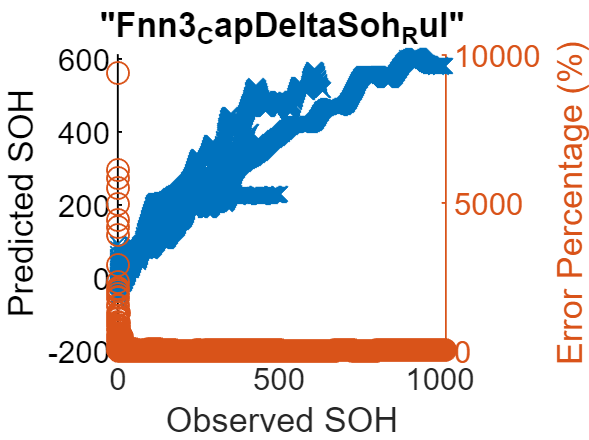


figure
hold on
plot(Y_test_RUL,Yfit_test_RUL,'x')
xlabel("Observed SOH")
ylabel("Predicted SOH")
%xlim([0 1.2]), ylim([0 1.2])

yyaxis right
ylabel('Error Percentage (%)')
plot(Y_test_RUL,Y_test_diff_percentage_RUL,'o');

hold off
title "Fnn3_CapDeltaSoh_Rul"



idxSearch = 1; % 316
idxSearch2 = 2; % 239

idxFind = idxTest(find(idxTest == idxTestSort(idxSearch)))

idxFind = 16

idxFindAll = find(idxTestAll_batIndex == idxFind)

idxFindAll = 1×316
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


Y_test_RUL_test1 = Y_test_RUL(idxFindAll)

Y_test_RUL_test1 = 316×1
   316
   315
   314
   313
   312
   311
   310
   309
   308
   307


Y_test_SOH_test1 = Y_test_SOH(idxFindAll)

Y_test_SOH_test1 = 316×1
    1.0477
    1.0476
    1.0474
    1.0473
    1.0471
    1.0470
    1.0468
    1.0467
    1.0465
    1.0464


Yfit_test_RUL_test1 = Yfit_test_RUL(idxFindAll)

Yfit_test_RUL_test1 = 316×1
  266.8918
  267.0097
  267.0825
  267.0101
  266.7734
  266.3474
  265.6940
  264.8358
  263.8185
  262.6919



idxFind2 = idxTest(find(idxTest == idxTestSort(idxSearch2)))

idxFind2 = 26

idxFindAll2 = find(idxTestAll_batIndex == idxFind2)

idxFindAll2 = 1×239
   317   318   319   320   321   322   323   324   325   326   327   328   329   330   331   332   333   334   335   336   337   338   339   340   341   342   343   344   345   346


Y_test_RUL_test2 = Y_test_RUL(idxFindAll2)

Y_test_RUL_test2 = 239×1
   239
   238
   237
   236
   235
   234
   233
   232
   231
   230


Yfit_test_RUL_test2 = Yfit_test_RUL(idxFindAll2)

Yfit_test_RUL_test2 = 239×1
  225.4595
  225.5818
  224.0731
  222.7049
  221.4782
  220.3946
  219.4464
  218.6278
  217.9203
  217.2923


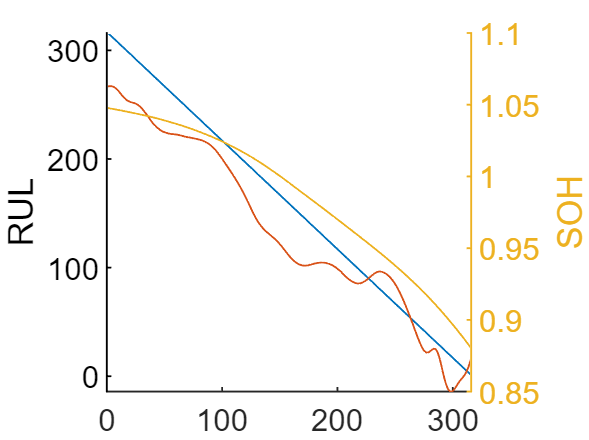



figure, hold on
plot(Y_test_RUL_test1)
plot(Yfit_test_RUL_test1)
ylabel('RUL')

yyaxis right
ylabel('SOH')
plot(Y_test_SOH_test1)
hold off

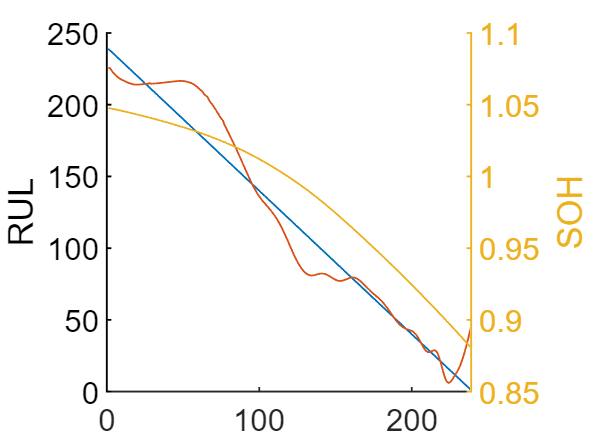


figure, hold on
plot(Y_test_RUL_test2)
plot(Yfit_test_RUL_test2)
ylabel('RUL')

yyaxis right
ylabel('SOH')
plot(Y_test_SOH_test2)
hold off

if generate_model
    mdl_Fnn3_IcSOH = feedforwardnet(fnn_neuron_layer3); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
    mdl_Fnn3_IcSOH.divideFcn = 'divideind';
    mdl_Fnn3_IcSOH.divideParam.trainInd = idxTrainAll;
    mdl_Fnn3_IcSOH.divideParam.valInd = idxValidAll;
    mdl_Fnn3_IcSOH.divideParam.testInd = idxTestAll; 
        
    %netFNN1__1.divideParam
    % https://kr.mathworks.com/matlabcentral/answers/314483-how-to-disable-popup-of-training-windows-for-neural-network-in-matlab
    mdl_Fnn3_IcSOH.trainParam.showWindow = 0; 
    mdl_Fnn3_IcSOH.trainParam.epochs = epoc_count; % 전체 데이타를 300번 반복 이용해라
    tic
    [mdl_Fnn3_IcSOH ] = train(mdl_Fnn3_IcSOH, xnorm_Ic', ynorm_SOH', 'useparallel',  'yes');
    toc

    mdl_Fnn3_VdSOH = feedforwardnet(fnn_neuron_layer3); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
    mdl_Fnn3_VdSOH.divideFcn = 'divideind';
    mdl_Fnn3_VdSOH.divideParam.trainInd = idxTrainAll;
    mdl_Fnn3_VdSOH.divideParam.valInd = idxValidAll;
    mdl_Fnn3_VdSOH.divideParam.testInd = idxTestAll; 
        
    %netFNN1__1.divideParam
    % https://kr.mathworks.com/matlabcentral/answers/314483-how-to-disable-popup-of-training-windows-for-neural-network-in-matlab
    mdl_Fnn3_VdSOH.trainParam.showWindow = 0; 
    mdl_Fnn3_VdSOH.trainParam.epochs = epoc_count; % 전체 데이타를 300번 반복 이용해라
    tic
    [mdl_Fnn3_VdSOH ] = train(mdl_Fnn3_VdSOH, xnorm_Vd', ynorm_SOH', 'useparallel',  'yes');
    toc
%%%%%%%%%%%
    mdl_Fnn3_IcDeltaSOH = feedforwardnet(fnn_neuron_layer3); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
    mdl_Fnn3_IcDeltaSOH.divideFcn = 'divideind';
    mdl_Fnn3_IcDeltaSOH.divideParam.trainInd = idxTrainAll;
    mdl_Fnn3_IcDeltaSOH.divideParam.valInd = idxValidAll;
    mdl_Fnn3_IcDeltaSOH.divideParam.testInd = idxTestAll; 
        
    %netFNN1__1.divideParam
    % https://kr.mathworks.com/matlabcentral/answers/314483-how-to-disable-popup-of-training-windows-for-neural-network-in-matlab
    mdl_Fnn3_IcDeltaSOH.trainParam.showWindow = 0; 
    mdl_Fnn3_IcDeltaSOH.trainParam.epochs = epoc_count; % 전체 데이타를 300번 반복 이용해라
    tic
    [mdl_Fnn3_IcDeltaSOH ] = train(mdl_Fnn3_IcDeltaSOH, xnorm_Ic', ynorm_DeltaSOH', 'useparallel',  'yes');
    toc

    mdl_Fnn3_VdDeltaSOH = feedforwardnet(fnn_neuron_layer3); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
    mdl_Fnn3_VdDeltaSOH.divideFcn = 'divideind';
    mdl_Fnn3_VdDeltaSOH.divideParam.trainInd = idxTrainAll;
    mdl_Fnn3_VdDeltaSOH.divideParam.valInd = idxValidAll;
    mdl_Fnn3_VdDeltaSOH.divideParam.testInd = idxTestAll; 
        
    %netFNN1__1.divideParam
    % https://kr.mathworks.com/matlabcentral/answers/314483-how-to-disable-popup-of-training-windows-for-neural-network-in-matlab
    mdl_Fnn3_VdDeltaSOH.trainParam.showWindow = 0; 
    mdl_Fnn3_VdDeltaSOH.trainParam.epochs = epoc_count; % 전체 데이타를 300번 반복 이용해라
    tic
    [mdl_Fnn3_VdDeltaSOH ] = train(mdl_Fnn3_VdDeltaSOH, xnorm_Vd', ynorm_DeltaSOH', 'useparallel',  'yes');
    toc

    save('ryan4_model_SOH.mat','mdl_Fnn3_IcSOH' ,'-append')
    save('ryan4_model_SOH.mat','mdl_Fnn3_VdSOH' ,'-append')    
    save('ryan4_model_SOH.mat','mdl_Fnn3_IcDeltaSOH' ,'-append')
    save('ryan4_model_SOH.mat','mdl_Fnn3_VdDeltaSOH' ,'-append') 
end

% if generate_model
%     mdl_Fnn3_IcDeltaRUL = feedforwardnet(fnn_neuron_layer3); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
%     mdl_Fnn3_IcDeltaRUL.divideFcn = 'divideind';
%     mdl_Fnn3_IcDeltaRUL.divideParam.trainInd = idxTrainAll;
%     mdl_Fnn3_IcDeltaRUL.divideParam.valInd = idxValidAll;
%     mdl_Fnn3_IcDeltaRUL.divideParam.testInd = idxTestAll; 
%         
%     %netFNN1__1.divideParam
%     % https://kr.mathworks.com/matlabcentral/answers/314483-how-to-disable-popup-of-training-windows-for-neural-network-in-matlab
%     mdl_Fnn3_IcDeltaRUL.trainParam.showWindow = 0; 
%     mdl_Fnn3_IcDeltaRUL.trainParam.epochs = epoc_count; % 전체 데이타를 300번 반복 이용해라
%     tic
%     [mdl_Fnn3_IcDeltaRUL ] = train(mdl_Fnn3_IcDeltaRUL, xnorm_Ic', ynorm_DeltaRUL', 'useparallel',  'yes');
%     toc
% 
%     mdl_Fnn3_VdDeltaRUL = feedforwardnet(fnn_neuron_layer3); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
%     mdl_Fnn3_VdDeltaRUL.divideFcn = 'divideind';
%     mdl_Fnn3_VdDeltaRUL.divideParam.trainInd = idxTrainAll;
%     mdl_Fnn3_VdDeltaRUL.divideParam.valInd = idxValidAll;
%     mdl_Fnn3_VdDeltaRUL.divideParam.testInd = idxTestAll; 
%         
%     %netFNN1__1.divideParam
%     % https://kr.mathworks.com/matlabcentral/answers/314483-how-to-disable-popup-of-training-windows-for-neural-network-in-matlab
%     mdl_Fnn3_VdDeltaRUL.trainParam.showWindow = 0; 
%     mdl_Fnn3_VdDeltaRUL.trainParam.epochs = epoc_count; % 전체 데이타를 300번 반복 이용해라
%     tic
%     [mdl_Fnn3_VdDeltaRUL ] = train(mdl_Fnn3_VdDeltaRUL, xnorm_Vd', ynorm_DeltaRUL', 'useparallel',  'yes');
%     toc
% 
%     save('ryan4_model_SOH.mat','mdl_Fnn3_IcDeltaRUL' ,'-append')
%     save('ryan4_model_SOH.mat','mdl_Fnn3_VdDeltaRUL' ,'-append')     
% end

# 선형회귀 - 예측 - Ic (20)

#### 전류 패턴에 따른 라이프 사이클 예측 - 100개가 아니 20개로 

#### 선형회귀 - 정규화 필요 없지만 정규화해도 된다. 다른 머신러닝 방법을 위해 정규화 된것을 사용하자.

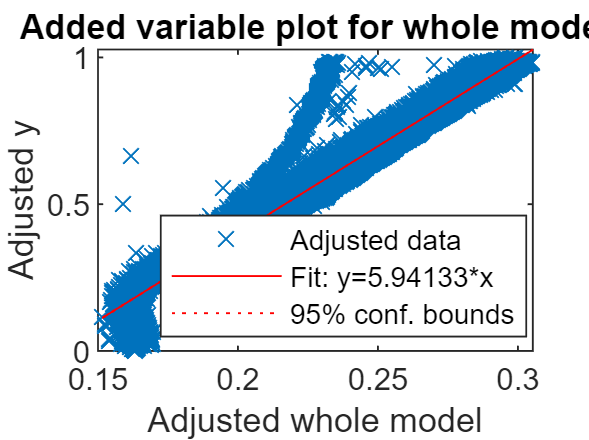

% coeff_IcSOH = mdl_Linear_IcSOH.Coefficients.Estimate;
% coeff_IcSOH'
% x_trainValid_Ic(1,:)
% yhat_trainValid_IcSOH = x_trainValid_Ic*coeff_IcSOH(2:21)+coeff_IcSOH(1);
% yhat_trainValid_IcSOH'

% figure
% hold on
% plot(y_trainValid_SOH,yhat_trainValid_IcSOH,'x')
% xlabel("Observed SOH")
% ylabel("Predicted SOH")
% hold off
% title 'Normalized'


figure
plot(mdl_Linear_IcSOH)

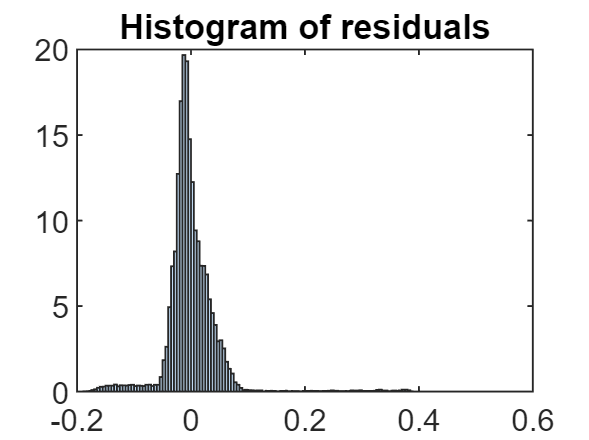

plotResiduals(mdl_Linear_IcSOH)


figure
yfit_trainValid_SOH = predict(mdl_Linear_IcSOH,x_trainValid_Ic);
yfit_trainValid_SOH'

ans = 1×38367
    0.9899    0.9642    0.9650    0.9730    0.9748    0.9603    0.9753    0.9597    0.9792    0.9780    0.9659    0.9564    0.9562    0.9710    0.9741    0.9538    0.9536    0.9755    0.9516    0.9516    0.9520    0.9531    0.9758    0.9500    0.9481    0.9472    0.9713    0.9461    0.9756    0.9454


yfit_test_SOH = predict(mdl_Linear_IcSOH,x_test_Ic_SOH);
yfit_test_SOH'

ans = 1×4488
    0.9970    0.9943    0.9943    0.9926    0.9917    0.9898    0.9894    0.9884    0.9870    0.9861    0.9852    0.9829    0.9819    0.9815    0.9816    0.9803    0.9794    0.9788    0.9604    0.9593    0.9760    0.9775    0.9777    0.9610    0.9785    0.9782    0.9599    0.9761    0.9745    0.9718



y_trainValid_SOH'

ans = 1×38367
    0.9878    0.9872    0.9867    0.9861    0.9855    0.9849    0.9843    0.9837    0.9832    0.9826    0.9820    0.9814    0.9808    0.9802    0.9796    0.9790    0.9784    0.9778    0.9772    0.9766    0.9760    0.9754    0.9748    0.9742    0.9736    0.9730    0.9724    0.9718    0.9712    0.9706


y_test_SOH'

ans = 1×4488
    0.9869    0.9861    0.9852    0.9843    0.9835    0.9826    0.9817    0.9809    0.9800    0.9791    0.9782    0.9773    0.9764    0.9755    0.9745    0.9736    0.9727    0.9717    0.9708    0.9698    0.9689    0.9679    0.9670    0.9660    0.9650    0.9641    0.9631    0.9621    0.9611    0.9601



Yfit_trainValid_SOH = yfit_trainValid_SOH * yrate_SOH + ymin_SOH;
Yfit_test_SOH = yfit_test_SOH * yrate_SOH + ymin_SOH;
%Y_test_SOH = y_test_Ic_SOH * yrate_Ic_SOH + ymin_Ic_SOH;


MAE_IcSOH = mean(abs(Yfit_trainValid_SOH-Y_trainValid_SOH))

MAE_IcSOH = 0.0048

adjMAE_IcSOH = MAE_IcSOH/range(Y_trainValid_SOH)

adjMAE_IcSOH = 0.0279

range(Y_trainValid_SOH) % Y_trainValid_SOH = range(X)는 X에 포함된 표본 데이터의 최댓값과 최솟값 간의 차이를 반환합니다.

ans = 0.1734


(Y_trainValid_SOH - Yfit_trainValid_SOH)'    % Errors

ans = 1×38367
   -0.0004    0.0040    0.0038    0.0023    0.0019    0.0043    0.0016    0.0042    0.0007    0.0008    0.0028    0.0044    0.0043    0.0016    0.0010    0.0044    0.0043    0.0004    0.0044    0.0043    0.0042    0.0039   -0.0002    0.0042    0.0044    0.0045    0.0002    0.0045   -0.0008    0.0044


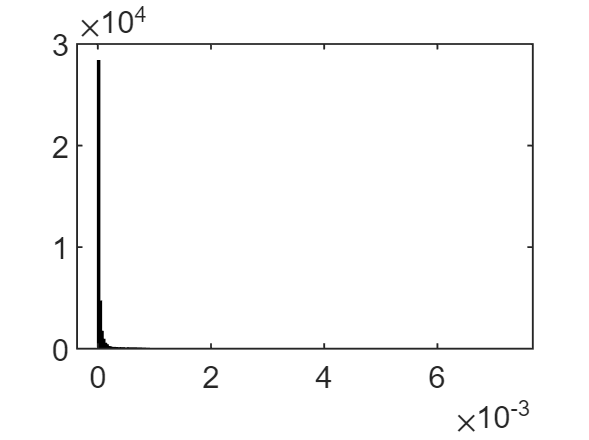

(Y_trainValid_SOH - Yfit_trainValid_SOH).^2;   % Squared Error
histogram((Y_trainValid_SOH - Yfit_trainValid_SOH).^2)

mean((Y_trainValid_SOH - Yfit_trainValid_SOH).^2);   % Mean Squared Error
RMSE_trainValid_IcSOH = sqrt(mean((Y_trainValid_SOH - Yfit_trainValid_SOH).^2))  % Root Mean Squared Error

RMSE_trainValid_IcSOH = 0.0083

Y_trainValid_diff_IcSOH = horzcat(Y_trainValid_SOH,(Y_trainValid_SOH-Yfit_trainValid_SOH))

Y_trainValid_diff_IcSOH = 38367×2
    1.0479   -0.0004
    1.0478    0.0040
    1.0477    0.0038
    1.0476    0.0023
    1.0475    0.0019
    1.0474    0.0043
    1.0473    0.0016
    1.0472    0.0042
    1.0471    0.0007
    1.0470    0.0008


Y_trainValid_diff_percentage_IcSOH = abs(Y_trainValid_SOH-Yfit_trainValid_SOH)./Y_trainValid_SOH.*100

Y_trainValid_diff_percentage_IcSOH = 38367×1
    0.0338
    0.3825
    0.3594
    0.2169
    0.1773
    0.4073
    0.1501
    0.3997
    0.0666
    0.0763


Y_trainValid_diff_percentage_avg_IcSOH = sum(Y_trainValid_diff_percentage_IcSOH)/length(Y_trainValid_diff_percentage_IcSOH)

Y_trainValid_diff_percentage_avg_IcSOH = 0.4956

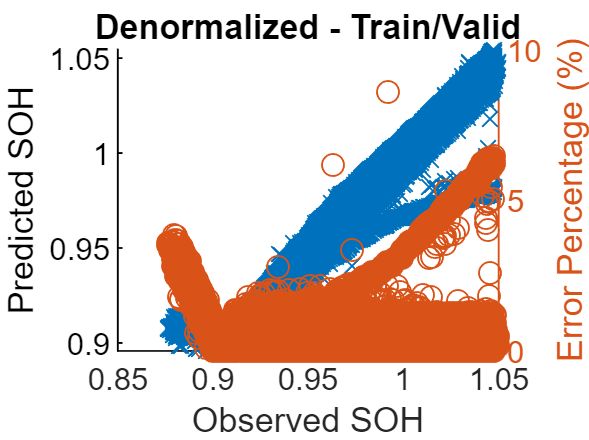

figure
hold on
plot(Y_trainValid_SOH,Yfit_trainValid_SOH,'x')
xlabel("Observed SOH")
ylabel("Predicted SOH")
%xlim([0 1.2]), ylim([0 1.2])

yyaxis right
ylabel('Error Percentage (%)')
plot(Y_trainValid_SOH,Y_trainValid_diff_percentage_IcSOH,'o');

hold off
title 'Denormalized - Train/Valid'


%%%%%%%%%%%%
RMSE_test_IcSOH = sqrt(mean((Y_test_SOH - Yfit_test_SOH).^2))

RMSE_test_IcSOH = 0.0060

Y_test_SOH - Yfit_test_SOH

ans = 4488×1
   -0.0017
   -0.0014
   -0.0016
   -0.0014
   -0.0014
   -0.0012
   -0.0013
   -0.0013
   -0.0012
   -0.0012


Y_test_diff_IcSOH = horzcat(Y_test_SOH,(Y_test_SOH-Yfit_test_SOH))

Y_test_diff_IcSOH = 4488×2
    1.0477   -0.0017
    1.0476   -0.0014
    1.0474   -0.0016
    1.0473   -0.0014
    1.0471   -0.0014
    1.0470   -0.0012
    1.0468   -0.0013
    1.0467   -0.0013
    1.0465   -0.0012
    1.0464   -0.0012


Y_test_diff_percentage_IcSOH = abs(Y_test_SOH-Yfit_test_SOH)./Y_test_SOH.*100

Y_test_diff_percentage_IcSOH = 4488×1
    0.1663
    0.1362
    0.1506
    0.1364
    0.1370
    0.1188
    0.1274
    0.1248
    0.1166
    0.1156


Y_test_diff_percentage_avg_IcSOH = sum(Y_test_diff_percentage_IcSOH)/length(Y_test_diff_percentage_IcSOH)

Y_test_diff_percentage_avg_IcSOH = 0.4444

num = 1:length(Y_test_SOH);


result = horzcat(num',Y_test_SOH,(Y_test_SOH-Yfit_test_SOH),Y_test_diff_percentage_IcSOH);
result % 배터리 번호 / SOH 관찰값 / 오차 / 오차 퍼센티지 

result = 4488×4
    1.0000    1.0477   -0.0017    0.1663
    2.0000    1.0476   -0.0014    0.1362
    3.0000    1.0474   -0.0016    0.1506
    4.0000    1.0473   -0.0014    0.1364
    5.0000    1.0471   -0.0014    0.1370
    6.0000    1.0470   -0.0012    0.1188
    7.0000    1.0468   -0.0013    0.1274
    8.0000    1.0467   -0.0013    0.1248
    9.0000    1.0465   -0.0012    0.1166
   10.0000    1.0464   -0.0012    0.1156


result_mdl_Linear_IcSOH = table(num',Y_test_SOH,(Y_test_SOH-Yfit_test_SOH),Y_test_diff_percentage_IcSOH);
result_mdl_Linear_IcSOH.Properties.VariableNames = {'bat num','SOH','오차','오차비율'};
result_mdl_Linear_IcSOH

result_mdl_Linear_IcSOH = 4488×4 table
    bat num     SOH         오차        오차비율 
    _______    ______    ___________    ________

       1       1.0477     -0.0017427     0.16633
       2       1.0476      -0.001427     0.13622
       3       1.0474     -0.0015774      0.1506
       4       1.0473     -0.0014289     0.13644
       5       1.0471     -0.0014343     0.13697
       6        1.047     -0.0012436     0.11878
       7       1.0468     -0.0013339     0.12742
       8       1.0467     -0.0013058     0.12475
       9       1.0465     -0.0012203      0.1166
      10       1.0464       -0.00121     0.11564
      11       1.0462     -0.0012219     0.11679
      12        1.046    -0.00096732    0.092474
      13       1.0459    -0.00095181    0.091005
      14       1.0457     -0.0010458     0.10001
      15       1.0456     -0.0012275      0.1

result_mdl_Linear_IcSOH_summary = table(RMSE_test_IcSOH,Y_test_diff_percentage_avg_IcSOH);
result_mdl_Linear_IcSOH_summary.Properties.VariableNames = {'RMSE','평균오차비율'};
result_mdl_Linear_IcSOH_summary 

result_mdl_Linear_IcSOH_summary = 1×2 table
      RMSE      평균오차비율
    ________    __________

    0.006005     0.44441  




RMSE_test_IcSOH

RMSE_test_IcSOH = 0.0060

Y_test_diff_percentage_avg_IcSOH

Y_test_diff_percentage_avg_IcSOH = 0.4444

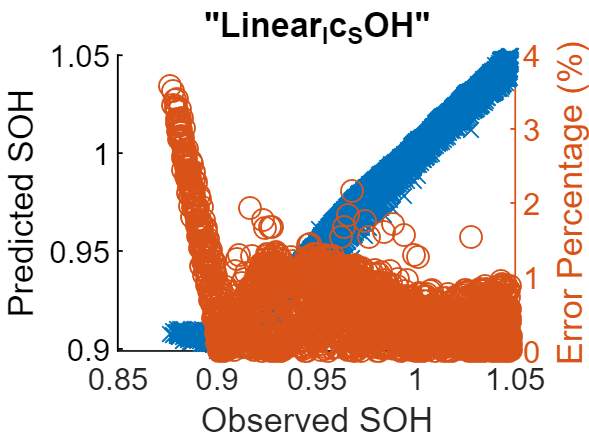


figure
hold on
plot(Y_test_SOH,Yfit_test_SOH,'x')
xlabel("Observed SOH")
ylabel("Predicted SOH")
%xlim([0 1.2]), ylim([0 1.2])

yyaxis right
ylabel('Error Percentage (%)')
plot(Y_test_SOH,Y_test_diff_percentage_IcSOH,'o');

hold off
title "Linear_Ic_SOH"

Yfit_test_SOH_test1 = Yfit_test_SOH(idxFindAll)

Yfit_test_SOH_test1 = 316×1
    1.0495
    1.0490
    1.0490
    1.0487
    1.0486
    1.0482
    1.0481
    1.0480
    1.0477
    1.0476


Y_test_SOH_test1 - Yfit_test_SOH_test1

ans = 316×1
   -0.0017
   -0.0014
   -0.0016
   -0.0014
   -0.0014
   -0.0012
   -0.0013
   -0.0013
   -0.0012
   -0.0012


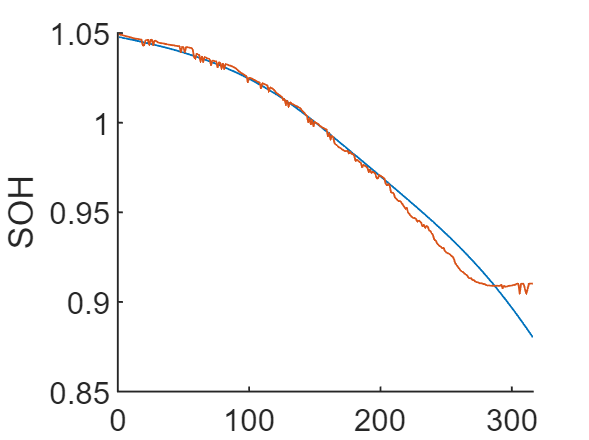




figure, hold on
plot(Y_test_SOH_test1)
plot(Yfit_test_SOH_test1)
ylabel('SOH')
hold off

# 선형회귀 - 예측 - Vd (20)

#### 전류 패턴에 따른 라이프 사이클 예측 - 100개가 아니 20개로 

#### 선형회귀 - 정규화 필요 없지만 정규화해도 된다. 다른 머신러닝 방법을 위해 정규화 된것을 사용하자.

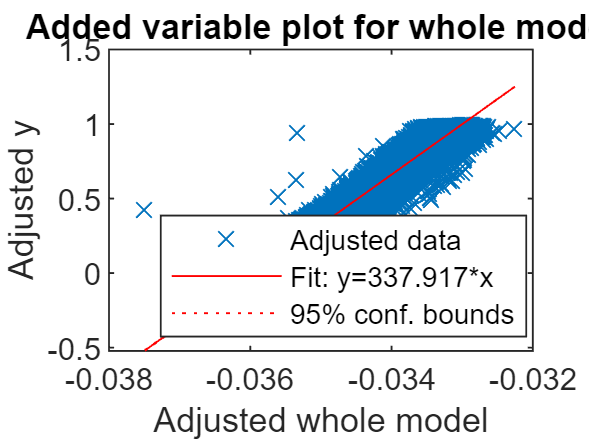

% coeff_VdSOH = mdl_Linear_VdSOH.Coefficients.Estimate;
% coeff_VdSOH'
% x_trainValid_Vd(1,:)
% yhat_trainValid_VdSOH = x_trainValid_Vd*coeff_VdSOH(2:21)+coeff_VdSOH(1);
% yhat_trainValid_VdSOH'
% figure
% hold on
% plot(y_trainValid_SOH,yhat_trainValid_VdSOH,'x')
% xlabel("Observed SOH")
% ylabel("Predicted SOH")
% hold off
% title 'Normalized'

figure
plot(mdl_Linear_VdSOH)

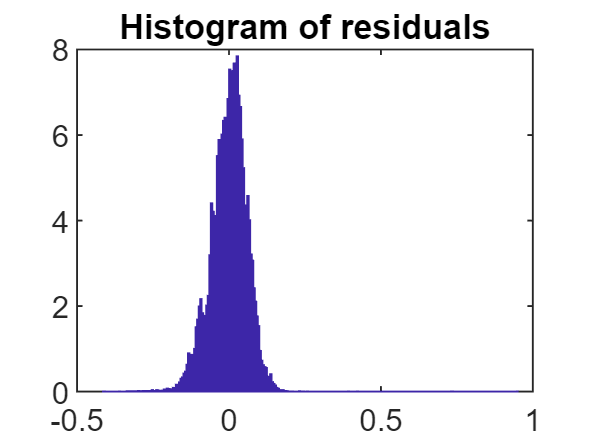

plotResiduals(mdl_Linear_VdSOH)

figure
yfit_trainValid_SOH = predict(mdl_Linear_VdSOH,x_trainValid_Vd);
yfit_trainValid_SOH'

ans = 1×38367
    1.0006    1.0076    0.9981    0.9953    0.9992    1.0001    0.9965    0.9996    0.9934    1.0004    0.9973    0.9999    0.9974    1.0027    0.9987    0.9911    0.9990    0.9952    1.0010    0.9896    0.9881    0.9854    0.9822    0.9889    0.9897    0.9954    0.9919    0.9924    0.9870    0.9850


yfit_test_SOH = predict(mdl_Linear_VdSOH,x_test_Vd_SOH);
yfit_test_SOH'

ans = 1×4488
    0.9332    0.9298    0.9263    0.9271    0.9273    0.9241    0.9308    0.9279    0.9272    0.9246    0.9344    0.9183    0.9240    0.9277    0.9243    0.9154    0.9188    0.9188    0.9119    0.9179    0.9221    0.9080    0.9090    0.9048    0.9066    0.9007    0.9014    0.9003    0.9032    0.9099



y_trainValid_SOH'

ans = 1×38367
    0.9878    0.9872    0.9867    0.9861    0.9855    0.9849    0.9843    0.9837    0.9832    0.9826    0.9820    0.9814    0.9808    0.9802    0.9796    0.9790    0.9784    0.9778    0.9772    0.9766    0.9760    0.9754    0.9748    0.9742    0.9736    0.9730    0.9724    0.9718    0.9712    0.9706


y_test_SOH'

ans = 1×4488
    0.9869    0.9861    0.9852    0.9843    0.9835    0.9826    0.9817    0.9809    0.9800    0.9791    0.9782    0.9773    0.9764    0.9755    0.9745    0.9736    0.9727    0.9717    0.9708    0.9698    0.9689    0.9679    0.9670    0.9660    0.9650    0.9641    0.9631    0.9621    0.9611    0.9601



Yfit_trainValid_SOH = yfit_trainValid_SOH * yrate_SOH + ymin_SOH;
Yfit_test_SOH = yfit_test_SOH * yrate_SOH + ymin_SOH;
%Y_test_SOH = y_test_Vd_SOH * yrate_Vd_SOH + ymin_Vd_SOH;


MAE_VdSOH = mean(abs(Yfit_trainValid_SOH-Y_trainValid_SOH))

MAE_VdSOH = 0.0079

adjMAE_VdSOH = MAE_VdSOH/range(Y_trainValid_SOH)

adjMAE_VdSOH = 0.0454

range(Y_trainValid_SOH) % Y_trainValid_SOH = range(X)는 X에 포함된 표본 데이터의 최댓값과 최솟값 간의 차이를 반환합니다.

ans = 0.1734


(Y_trainValid_SOH - Yfit_trainValid_SOH)'    % Errors

ans = 1×38367
   -0.0022   -0.0035   -0.0020   -0.0016   -0.0024   -0.0026   -0.0021   -0.0028   -0.0018   -0.0031   -0.0027   -0.0032   -0.0029   -0.0039   -0.0033   -0.0021   -0.0036   -0.0030   -0.0041   -0.0023   -0.0021   -0.0017   -0.0013   -0.0025   -0.0028   -0.0039   -0.0034   -0.0036   -0.0028   -0.0025


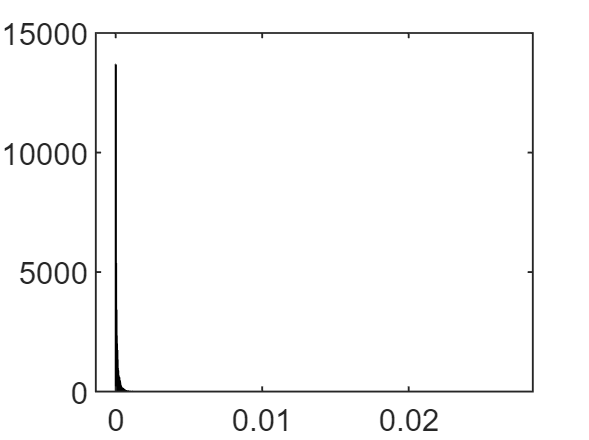

(Y_trainValid_SOH - Yfit_trainValid_SOH).^2;   % Squared Error
histogram((Y_trainValid_SOH - Yfit_trainValid_SOH).^2)

mean((Y_trainValid_SOH - Yfit_trainValid_SOH).^2);   % Mean Squared Error
RMSE_trainValid_VdSOH = sqrt(mean((Y_trainValid_SOH - Yfit_trainValid_SOH).^2))  % Root Mean Squared Error

RMSE_trainValid_VdSOH = 0.0101

Y_trainValid_diff_VdSOH = horzcat(Y_trainValid_SOH,(Y_trainValid_SOH-Yfit_trainValid_SOH))

Y_trainValid_diff_VdSOH = 38367×2
    1.0479   -0.0022
    1.0478   -0.0035
    1.0477   -0.0020
    1.0476   -0.0016
    1.0475   -0.0024
    1.0474   -0.0026
    1.0473   -0.0021
    1.0472   -0.0028
    1.0471   -0.0018
    1.0470   -0.0031


Y_trainValid_diff_percentage_VdSOH = abs(Y_trainValid_SOH-Yfit_trainValid_SOH)./Y_trainValid_SOH.*100

Y_trainValid_diff_percentage_VdSOH = 38367×1
    0.2113
    0.3382
    0.1905
    0.1532
    0.2273
    0.2522
    0.2016
    0.2637
    0.1691
    0.2961


Y_trainValid_diff_percentage_avg_VdSOH = sum(Y_trainValid_diff_percentage_VdSOH)/length(Y_trainValid_diff_percentage_VdSOH)

Y_trainValid_diff_percentage_avg_VdSOH = 0.7917

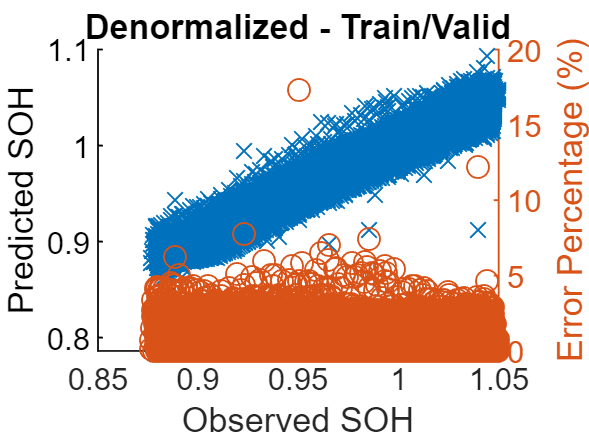

figure
hold on
plot(Y_trainValid_SOH,Yfit_trainValid_SOH,'x')
xlabel("Observed SOH")
ylabel("Predicted SOH")
%xlim([0 1.2]), ylim([0 1.2])

yyaxis right
ylabel('Error Percentage (%)')
plot(Y_trainValid_SOH,Y_trainValid_diff_percentage_VdSOH,'o');

hold off
title 'Denormalized - Train/Valid'


%%%%%%%%%%%%
RMSE_test_VdSOH = sqrt(mean((Y_test_SOH - Yfit_test_SOH).^2))

RMSE_test_VdSOH = 0.0102

Y_test_SOH - Yfit_test_SOH

ans = 4488×1
    0.0093
    0.0098
    0.0102
    0.0099
    0.0098
    0.0102
    0.0088
    0.0092
    0.0092
    0.0095


Y_test_diff_VdSOH = horzcat(Y_test_SOH,(Y_test_SOH-Yfit_test_SOH))

Y_test_diff_VdSOH = 4488×2
    1.0477    0.0093
    1.0476    0.0098
    1.0474    0.0102
    1.0473    0.0099
    1.0471    0.0098
    1.0470    0.0102
    1.0468    0.0088
    1.0467    0.0092
    1.0465    0.0092
    1.0464    0.0095


Y_test_diff_percentage_VdSOH = abs(Y_test_SOH-Yfit_test_SOH)./Y_test_SOH.*100

Y_test_diff_percentage_VdSOH = 4488×1
    0.8908
    0.9320
    0.9770
    0.9490
    0.9317
    0.9705
    0.8445
    0.8796
    0.8765
    0.9046


Y_test_diff_percentage_avg_VdSOH = sum(Y_test_diff_percentage_VdSOH)/length(Y_test_diff_percentage_VdSOH)

Y_test_diff_percentage_avg_VdSOH = 0.7737

num = 1:length(Y_test_SOH);


result = horzcat(num',Y_test_SOH,(Y_test_SOH-Yfit_test_SOH),Y_test_diff_percentage_VdSOH);
result % 배터리 번호 / SOH 관찰값 / 오차 / 오차 퍼센티지 

result = 4488×4
    1.0000    1.0477    0.0093    0.8908
    2.0000    1.0476    0.0098    0.9320
    3.0000    1.0474    0.0102    0.9770
    4.0000    1.0473    0.0099    0.9490
    5.0000    1.0471    0.0098    0.9317
    6.0000    1.0470    0.0102    0.9705
    7.0000    1.0468    0.0088    0.8445
    8.0000    1.0467    0.0092    0.8796
    9.0000    1.0465    0.0092    0.8765
   10.0000    1.0464    0.0095    0.9046


result_mdl_Linear_VdSOH = table(num',Y_test_SOH,(Y_test_SOH-Yfit_test_SOH),Y_test_diff_percentage_VdSOH);
result_mdl_Linear_VdSOH.Properties.VariableNames = {'bat num','SOH','오차','오차비율'};
result_mdl_Linear_VdSOH

result_mdl_Linear_VdSOH = 4488×4 table
    bat num     SOH        오차       오차비율
    _______    ______    _________    _______

       1       1.0477    0.0093326    0.89075
       2       1.0476    0.0097638    0.93204
       3       1.0474     0.010233    0.97696
       4       1.0473    0.0099388    0.94902
       5       1.0471    0.0097565    0.93175
       6        1.047     0.010161    0.97048
       7       1.0468    0.0088408    0.84454
       8       1.0467    0.0092065     0.8796
       9       1.0465    0.0091728    0.87652
      10       1.0464    0.0094658    0.90464
      11       1.0462    0.0076129    0.72767
      12        1.046     0.010251    0.98001
      13       1.0459    0.0090934    0.86944
      14       1.0457    0.0082982    0.79354
      15       1.0456    0.0087306    0.83501
      16       1.0454     0.010109    0.96698


result_mdl_Linear_VdSOH_summary = table(RMSE_test_VdSOH,Y_test_diff_percentage_avg_VdSOH);
result_mdl_Linear_VdSOH_summary.Properties.VariableNames = {'RMSE','평균오차비율'};
result_mdl_Linear_VdSOH_summary 

result_mdl_Linear_VdSOH_summary = 1×2 table
      RMSE      평균오차비율
    ________    __________

    0.010161     0.77366  




RMSE_test_VdSOH

RMSE_test_VdSOH = 0.0102

Y_test_diff_percentage_avg_VdSOH

Y_test_diff_percentage_avg_VdSOH = 0.7737

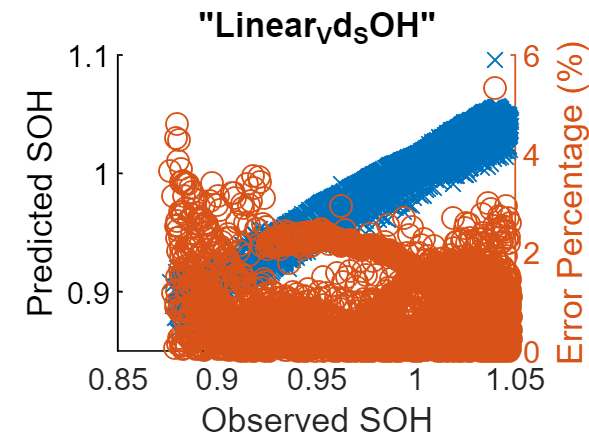


figure
hold on
plot(Y_test_SOH,Yfit_test_SOH,'x')
xlabel("Observed SOH")
ylabel("Predicted SOH")
%xlim([0 1.2]), ylim([0 1.2])

yyaxis right
ylabel('Error Percentage (%)')
plot(Y_test_SOH,Y_test_diff_percentage_VdSOH,'o');

hold off
title "Linear_Vd_SOH"

idxSearch = 1; % 316
idxSearch2 = 2; % 239

idxFind = idxTest(find(idxTest == idxTestSort(idxSearch)))

idxFind = 16

idxFindAll = find(idxTestAll_batIndex == idxFind)

idxFindAll = 1×316
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


Y_test_SOH_test1 = Y_test_SOH(idxFindAll)

Y_test_SOH_test1 = 316×1
    1.0477
    1.0476
    1.0474
    1.0473
    1.0471
    1.0470
    1.0468
    1.0467
    1.0465
    1.0464


Yfit_test_SOH_test1 = Yfit_test_SOH(idxFindAll)

Yfit_test_SOH_test1 = 316×1
    1.0384
    1.0378
    1.0372
    1.0373
    1.0374
    1.0368
    1.0380
    1.0375
    1.0373
    1.0369



idxFind2 = idxTest(find(idxTest == idxTestSort(idxSearch2)))

idxFind2 = 26

idxFindAll2 = find(idxTestAll_batIndex == idxFind2)

idxFindAll2 = 1×239
   317   318   319   320   321   322   323   324   325   326   327   328   329   330   331   332   333   334   335   336   337   338   339   340   341   342   343   344   345   346


Y_test_SOH_test2 = Y_test_SOH(idxFindAll2)

Y_test_SOH_test2 = 239×1
    1.0477
    1.0475
    1.0473
    1.0471
    1.0468
    1.0466
    1.0464
    1.0462
    1.0459
    1.0457


Y_test_SOH_test1 - Yfit_test_SOH_test1

ans = 316×1
    0.0093
    0.0098
    0.0102
    0.0099
    0.0098
    0.0102
    0.0088
    0.0092
    0.0092
    0.0095


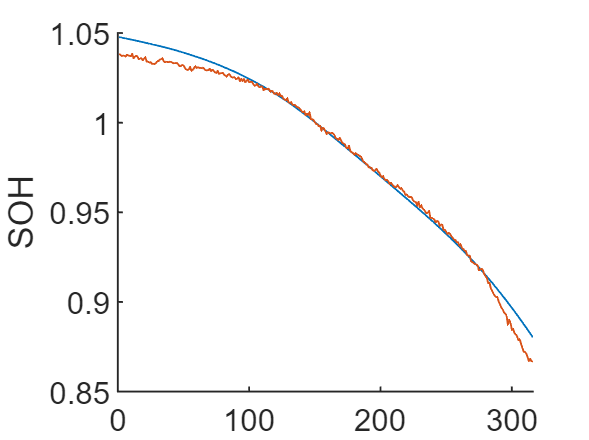



figure, hold on
plot(Y_test_SOH_test1)
plot(Yfit_test_SOH_test1)
ylabel('SOH')
hold off

# 선형회귀 - 예측 - Ic (20) -DeltaSOH

#### 전류 패턴에 따른 라이프 사이클 예측 - 100개가 아니 20개로 

#### 선형회귀 - 정규화 필요 없지만 정규화해도 된다. 다른 머신러닝 방법을 위해 정규화 된것을 사용하자.

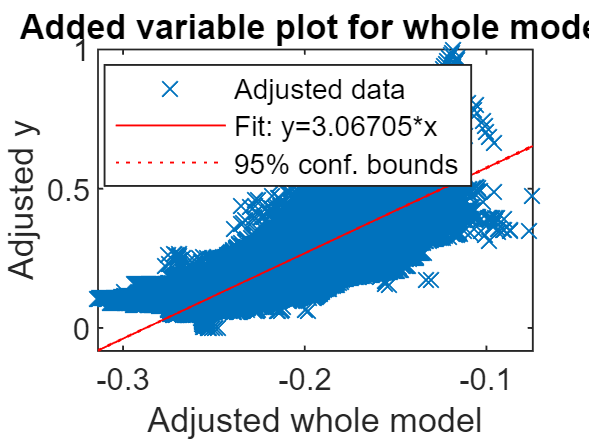

% coeff_IcSOH = mdl_Linear_IcSOH.Coefficients.Estimate;
% coeff_IcSOH'
% x_trainValid_Ic(1,:)
% yhat_trainValid_IcSOH = x_trainValid_Ic*coeff_IcSOH(2:21)+coeff_IcSOH(1);
% yhat_trainValid_IcSOH'

% figure
% hold on
% plot(y_trainValid_SOH,yhat_trainValid_IcSOH,'x')
% xlabel("Observed SOH")
% ylabel("Predicted SOH")
% hold off
% title 'Normalized'


figure
plot(mdl_Linear_IcDeltaSOH)

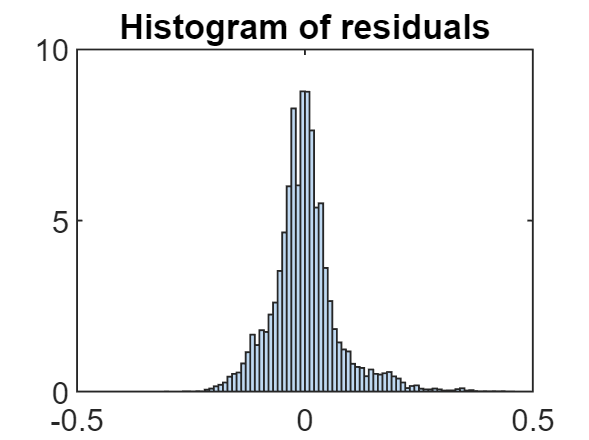

plotResiduals(mdl_Linear_IcDeltaSOH)


figure
yfit_trainValid_DeltaSOH = predict(mdl_Linear_IcDeltaSOH,x_trainValid_Ic);
yfit_trainValid_DeltaSOH'

ans = 1×38367
    0.0589    0.0500    0.0500    0.0549    0.0555    0.0510    0.0566    0.0513    0.0593    0.0596    0.0556    0.0517    0.0515    0.0584    0.0596    0.0522    0.0523    0.0612    0.0527    0.0525    0.0521    0.0522    0.0622    0.0524    0.0530    0.0534    0.0741    0.0540    0.1044    0.0541


yfit_test_DeltaSOH = predict(mdl_Linear_IcDeltaSOH,x_test_Ic);
yfit_test_DeltaSOH'

ans = 1×4488
    0.1449    0.1454    0.1455    0.1457    0.1459    0.1462    0.1462    0.1463    0.1466    0.1468    0.1470    0.1473    0.1475    0.1475    0.1475    0.1477    0.1479    0.1480    0.1414    0.1416    0.1484    0.1483    0.1481    0.1413    0.1479    0.1480    0.1415    0.1484    0.1487    0.1491



y_trainValid_DeltaSOH'

ans = 1×38367
    0.0716    0.0716    0.0716    0.0715    0.0715    0.0715    0.0715    0.0716    0.0716    0.0717    0.0718    0.0719    0.0720    0.0722    0.0723    0.0725    0.0726    0.0727    0.0728    0.0729    0.0729    0.0729    0.0730    0.0730    0.0730    0.0730    0.0731    0.0731    0.0732    0.0733


y_test_DeltaSOH'

ans = 1×4488
    0.0885    0.0885    0.0885    0.0886    0.0887    0.0888    0.0890    0.0893    0.0897    0.0901    0.0905    0.0909    0.0914    0.0918    0.0923    0.0927    0.0931    0.0934    0.0937    0.0939    0.0941    0.0943    0.0944    0.0946    0.0948    0.0951    0.0954    0.0958    0.0963    0.0968



Yfit_trainValid_DeltaSOH = yfit_trainValid_DeltaSOH * yrate_DeltaSOH + ymin_DeltaSOH;
Yfit_test_DeltaSOH = yfit_test_DeltaSOH * yrate_DeltaSOH + ymin_DeltaSOH;
%Y_test_DeltaSOH = y_test_Ic_DeltaSOH * yrate_Ic_DeltaSOH + ymin_Ic_DeltaSOH;


MAE_IcDeltaSOH = mean(abs(Yfit_trainValid_DeltaSOH-Y_trainValid_DeltaSOH))

MAE_IcDeltaSOH = 1.4853e-04

adjMAE_IcDeltaSOH = MAE_IcDeltaSOH/range(Y_trainValid_DeltaSOH)

adjMAE_IcDeltaSOH = 0.0517

range(Y_trainValid_DeltaSOH) % Y_trainValid_DeltaSOH = range(X)는 X에 포함된 표본 데이터의 최댓값과 최솟값 간의 차이를 반환합니다.

ans = 0.0029


(Y_trainValid_DeltaSOH - Yfit_trainValid_DeltaSOH)'    % Errors

ans = 1×38367
1.0e+00 *

    0.0000    0.0001    0.0001    0.0000    0.0000    0.0001    0.0000    0.0001    0.0000    0.0000    0.0000    0.0001    0.0001    0.0000    0.0000    0.0001    0.0001    0.0000    0.0001    0.0001    0.0001    0.0001    0.0000    0.0001    0.0001    0.0001   -0.0000    0.0001   -0.0001    0.0001


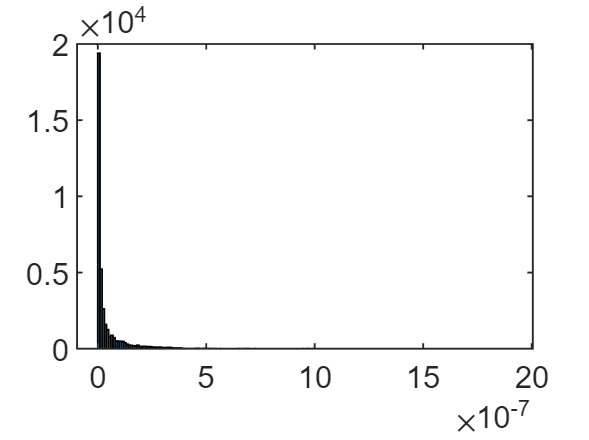

(Y_trainValid_DeltaSOH - Yfit_trainValid_DeltaSOH).^2;   % Squared Error
histogram((Y_trainValid_DeltaSOH - Yfit_trainValid_DeltaSOH).^2)

mean((Y_trainValid_DeltaSOH - Yfit_trainValid_DeltaSOH).^2);   % Mean Squared Error
RMSE_trainValid_IcDeltaSOH = sqrt(mean((Y_trainValid_DeltaSOH - Yfit_trainValid_DeltaSOH).^2))  % Root Mean Squared Error

RMSE_trainValid_IcDeltaSOH = 2.1373e-04

Y_trainValid_diff_IcDeltaSOH = horzcat(Y_trainValid_DeltaSOH,(Y_trainValid_DeltaSOH-Yfit_trainValid_DeltaSOH))

Y_trainValid_diff_IcDeltaSOH = 38367×2
1.0e+00 *

    0.0001    0.0000
    0.0001    0.0001
    0.0001    0.0001
    0.0001    0.0000
    0.0001    0.0000
    0.0001    0.0001
    0.0001    0.0000
    0.0001    0.0001
    0.0001    0.0000
    0.0001    0.0000


Y_trainValid_diff_percentage_IcDeltaSOH = abs(Y_trainValid_DeltaSOH-Yfit_trainValid_DeltaSOH)./Y_trainValid_DeltaSOH.*100

Y_trainValid_diff_percentage_IcDeltaSOH = 38367×1
   35.9971
   61.4150
   61.3784
   47.4944
   45.5266
   58.4827
   42.4097
   57.6890
   34.9051
   34.3285


Y_trainValid_diff_percentage_avg_IcDeltaSOH = sum(Y_trainValid_diff_percentage_IcDeltaSOH)/length(Y_trainValid_diff_percentage_IcDeltaSOH)

Y_trainValid_diff_percentage_avg_IcDeltaSOH = 51.1531

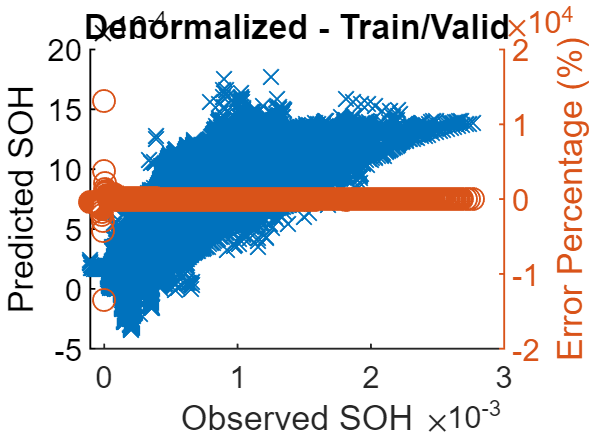

figure
hold on
plot(Y_trainValid_DeltaSOH,Yfit_trainValid_DeltaSOH,'x')
xlabel("Observed SOH")
ylabel("Predicted SOH")
%xlim([0 1.2]), ylim([0 1.2])

yyaxis right
ylabel('Error Percentage (%)')
plot(Y_trainValid_DeltaSOH,Y_trainValid_diff_percentage_IcDeltaSOH,'o');

hold off
title 'Denormalized - Train/Valid'


%%%%%%%%%%%%
RMSE_test_IcDeltaSOH = sqrt(mean((Y_test_DeltaSOH - Yfit_test_DeltaSOH).^2))

RMSE_test_IcDeltaSOH = 2.1444e-04

Y_test_DeltaSOH - Yfit_test_DeltaSOH

ans = 4488×1
1.0e-03 *

   -0.1622
   -0.1637
   -0.1639
   -0.1643
   -0.1644
   -0.1649
   -0.1644
   -0.1639
   -0.1638
   -0.1632


Y_test_diff_IcDeltaSOH = horzcat(Y_test_DeltaSOH,(Y_test_DeltaSOH-Yfit_test_DeltaSOH))

Y_test_diff_IcDeltaSOH = 4488×2
1.0e+00 *

    0.0001   -0.0002
    0.0001   -0.0002
    0.0001   -0.0002
    0.0001   -0.0002
    0.0002   -0.0002
    0.0002   -0.0002
    0.0002   -0.0002
    0.0002   -0.0002
    0.0002   -0.0002
    0.0002   -0.0002


Y_test_diff_percentage_IcDeltaSOH = abs(Y_test_DeltaSOH-Yfit_test_DeltaSOH)./Y_test_DeltaSOH.*100

Y_test_diff_percentage_IcDeltaSOH = 4488×1
  108.3841
  109.3740
  109.5058
  109.6264
  109.5275
  109.4771
  108.7351
  107.7544
  107.0198
  105.8684


Y_test_diff_percentage_avg_IcDeltaSOH = sum(Y_test_diff_percentage_IcDeltaSOH)/length(Y_test_diff_percentage_IcDeltaSOH)

Y_test_diff_percentage_avg_IcDeltaSOH = 39.6910

num = 1:length(Y_test_DeltaSOH);


result = horzcat(num',Y_test_DeltaSOH,(Y_test_DeltaSOH-Yfit_test_DeltaSOH),Y_test_diff_percentage_IcDeltaSOH);
result % 배터리 번호 / DeltaSOH 관찰값 / 오차 / 오차 퍼센티지 

result = 4488×4
    1.0000    0.0001   -0.0002  108.3841
    2.0000    0.0001   -0.0002  109.3740
    3.0000    0.0001   -0.0002  109.5058
    4.0000    0.0001   -0.0002  109.6264
    5.0000    0.0002   -0.0002  109.5275
    6.0000    0.0002   -0.0002  109.4771
    7.0000    0.0002   -0.0002  108.7351
    8.0000    0.0002   -0.0002  107.7544
    9.0000    0.0002   -0.0002  107.0198
   10.0000    0.0002   -0.0002  105.8684


result_mdl_Linear_IcDeltaSOH = table(num',Y_test_DeltaSOH,(Y_test_DeltaSOH-Yfit_test_DeltaSOH),Y_test_diff_percentage_IcDeltaSOH);
result_mdl_Linear_IcDeltaSOH.Properties.VariableNames = {'bat num','DeltaSOH','오차','오차비율'};
result_mdl_Linear_IcDeltaSOH

result_mdl_Linear_IcDeltaSOH = 4488×4 table
    bat num     DeltaSOH        오차        오차비율
    _______    __________    ___________    _______

       1       0.00014965    -0.00016219    108.38 
       2       0.00014965    -0.00016367    109.37 
       3       0.00014968    -0.00016391    109.51 
       4       0.00014984    -0.00016426    109.63 
       5       0.00015013    -0.00016444    109.53 
       6       0.00015059    -0.00016486    109.48 
       7       0.00015124    -0.00016445    108.74 
       8       0.00015207    -0.00016386    107.75 
       9       0.00015306     -0.0001638    107.02 
      10       0.00015416    -0.00016321    105.87 
      11       0.00015536    -0.00016245    104.56 
      12       0.00015666    -0.00016219    103.53 
      13         0.000158    -0.00016138    102.14 
      14       0.00015932    -0.00016005    

result_mdl_Linear_IcDeltaSOH_summary = table(RMSE_test_IcDeltaSOH,Y_test_diff_percentage_avg_IcDeltaSOH);
result_mdl_Linear_IcDeltaSOH_summary.Properties.VariableNames = {'RMSE','평균오차비율'};
result_mdl_Linear_IcDeltaSOH_summary 

result_mdl_Linear_IcDeltaSOH_summary = 1×2 table
       RMSE       평균오차비율
    __________    __________

    0.00021444      39.691  




RMSE_test_IcDeltaSOH

RMSE_test_IcDeltaSOH = 2.1444e-04

Y_test_diff_percentage_avg_IcDeltaSOH

Y_test_diff_percentage_avg_IcDeltaSOH = 39.6910

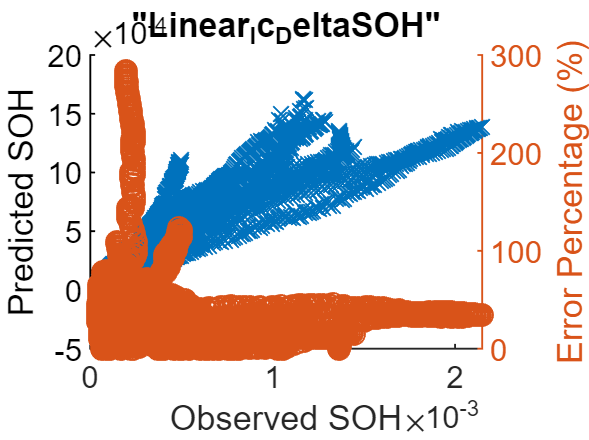


figure
hold on
plot(Y_test_DeltaSOH,Yfit_test_DeltaSOH,'x')
xlabel("Observed SOH")
ylabel("Predicted SOH")
%xlim([0 1.2]), ylim([0 1.2])

yyaxis right
ylabel('Error Percentage (%)')
plot(Y_test_DeltaSOH,Y_test_diff_percentage_IcDeltaSOH,'o');

hold off
title "Linear_Ic_DeltaSOH"

% Y_test_SOH - (Y_trainValid_DeltaSOH) * n < Cap_EOL
T_test_SOH_EOL = Y_test_SOH -Cap_EOL

T_test_SOH_EOL = 4488×1
    0.1673
    0.1672
    0.1670
    0.1669
    0.1667
    0.1666
    0.1664
    0.1663
    0.1661
    0.1660



%coeff = linspace(0.5,1,length(Y_test_DeltaSOH))'
coeff =0.1

coeff = 0.1000

x = Y_test_RUL  / max(Y_test_RUL) 

x = 4488×1
    0.3101
    0.3091
    0.3081
    0.3072
    0.3062
    0.3052
    0.3042
    0.3032
    0.3023
    0.3013


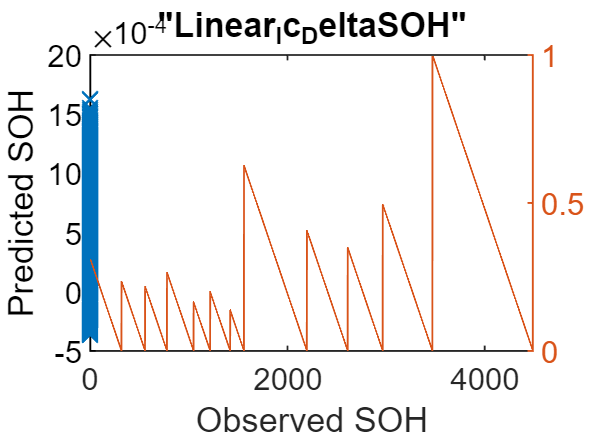

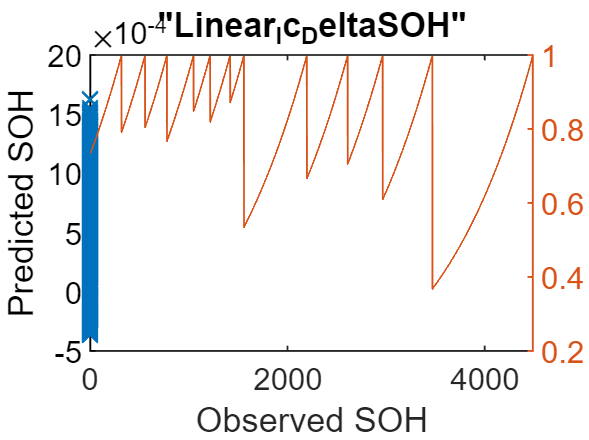

plot(x)
plot( exp(-1  *  x ))


Y_test_DeltaSOH_adj = Y_test_DeltaSOH .* exp(-1  *  x )

Y_test_DeltaSOH_adj = 4488×1
1.0e+00 *

    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001


Yfit_RUL =  T_test_SOH_EOL  ./ Y_test_DeltaSOH .* exp(-1  *  x ) ./ 2.6

Yfit_RUL = 4488×1
  315.4175
  315.4449
  315.3938
  315.0898
  314.4989
  313.5760
  312.2516
  310.5603
  308.5769
  306.3845


error = Y_test_RUL - Yfit_RUL

error = 4488×1
    0.5825
   -0.4449
   -1.3938
   -2.0898
   -2.4989
   -2.5760
   -2.2516
   -1.5603
   -0.5769
    0.6155


error_mean = mean(error);
error_mean

error_mean = 68.3049

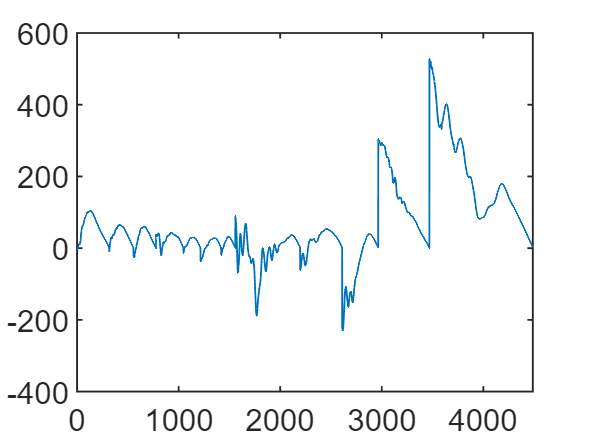

figure
plot(error)

# 선형회귀 - 예측 - Vd (20) -DeltaSOH

#### 전류 패턴에 따른 라이프 사이클 예측 - 100개가 아니 20개로 

#### 선형회귀 - 정규화 필요 없지만 정규화해도 된다. 다른 머신러닝 방법을 위해 정규화 된것을 사용하자.

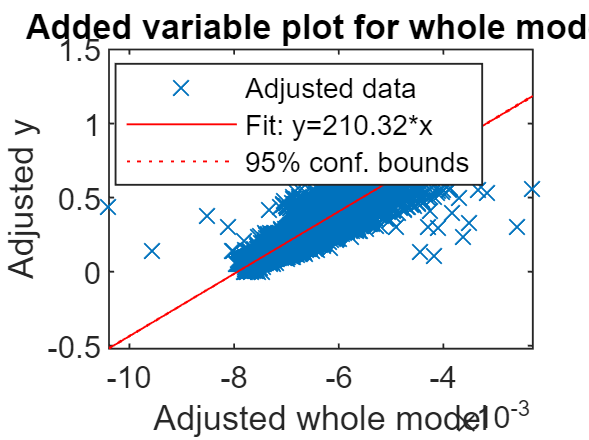

% coeff_VdDeltaSOH = mdl_Linear_VdDeltaSOH.Coefficients.Estimate;
% coeff_VdDeltaSOH'
% x_trainValid_Vd(1,:)
% yhat_trainValid_VdDeltaSOH = x_trainValid_Vd*coeff_VdDeltaSOH(2:21)+coeff_VdDeltaSOH(1);
% yhat_trainValid_VdDeltaSOH'
% figure
% hold on
% plot(y_trainValid_DeltaSOH,yhat_trainValid_VdDeltaSOH,'x')
% xlabel("Observed SOH")
% ylabel("Predicted SOH")
% hold off
% title 'Normalized'

figure
plot(mdl_Linear_VdDeltaSOH)

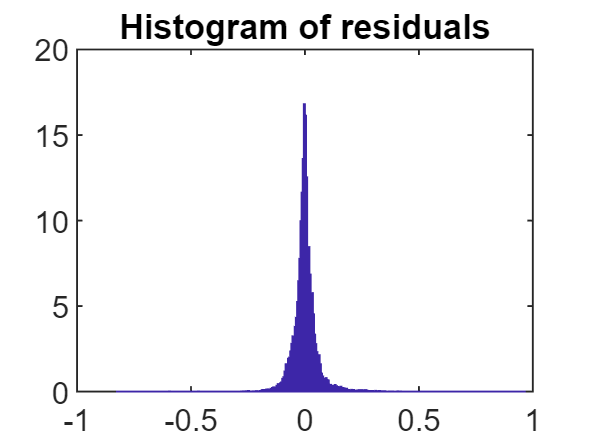

plotResiduals(mdl_Linear_VdDeltaSOH)

figure
yfit_trainValid_DeltaSOH = predict(mdl_Linear_VdDeltaSOH,x_trainValid_Vd);
yfit_trainValid_DeltaSOH'

ans = 1×38367
    0.0672    0.0636    0.0716    0.0604    0.0609    0.0644    0.0651    0.0626    0.0565    0.0675    0.0593    0.0667    0.0614    0.0596    0.0579    0.0570    0.0616    0.0645    0.0659    0.0530    0.0576    0.0682    0.0604    0.0606    0.0624    0.0697    0.0611    0.0702    0.0597    0.0607


yfit_test_DeltaSOH = predict(mdl_Linear_VdDeltaSOH,x_test_Vd);
yfit_test_DeltaSOH'

ans = 1×4488
    0.0739    0.0663    0.0688    0.0816    0.0804    0.0713    0.0807    0.0705    0.0743    0.0805    0.0823    0.0745    0.0792    0.0818    0.0762    0.0836    0.0751    0.0840    0.0767    0.0859    0.0811    0.0688    0.0773    0.0689    0.0674    0.0710    0.0777    0.0758    0.0793    0.0904



y_trainValid_DeltaSOH'

ans = 1×38367
    0.0716    0.0716    0.0716    0.0715    0.0715    0.0715    0.0715    0.0716    0.0716    0.0717    0.0718    0.0719    0.0720    0.0722    0.0723    0.0725    0.0726    0.0727    0.0728    0.0729    0.0729    0.0729    0.0730    0.0730    0.0730    0.0730    0.0731    0.0731    0.0732    0.0733


y_test_DeltaSOH'

ans = 1×4488
    0.0885    0.0885    0.0885    0.0886    0.0887    0.0888    0.0890    0.0893    0.0897    0.0901    0.0905    0.0909    0.0914    0.0918    0.0923    0.0927    0.0931    0.0934    0.0937    0.0939    0.0941    0.0943    0.0944    0.0946    0.0948    0.0951    0.0954    0.0958    0.0963    0.0968



Yfit_trainValid_DeltaSOH = yfit_trainValid_DeltaSOH * yrate_DeltaSOH + ymin_DeltaSOH;
Yfit_test_DeltaSOH = yfit_test_DeltaSOH * yrate_DeltaSOH + ymin_DeltaSOH;
%Y_test_DeltaSOH = y_test_Vd_DeltaSOH * yrate_Vd_DeltaSOH + ymin_Vd_DeltaSOH;


MAE_VdDeltaSOH = mean(abs(Yfit_trainValid_DeltaSOH-Y_trainValid_DeltaSOH))

MAE_VdDeltaSOH = 9.6870e-05

adjMAE_VdDeltaSOH = MAE_VdDeltaSOH/range(Y_trainValid_DeltaSOH)

adjMAE_VdDeltaSOH = 0.0337

range(Y_trainValid_DeltaSOH) % Y_trainValid_DeltaSOH = range(X)는 X에 포함된 표본 데이터의 최댓값과 최솟값 간의 차이를 반환합니다.

ans = 0.0029


(Y_trainValid_DeltaSOH - Yfit_trainValid_DeltaSOH)'    % Errors

ans = 1×38367
1.0e+00 *

    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


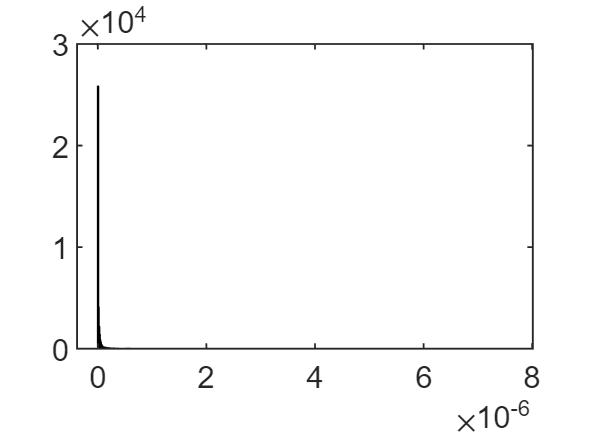

(Y_trainValid_DeltaSOH - Yfit_trainValid_DeltaSOH).^2;   % Squared Error
histogram((Y_trainValid_DeltaSOH - Yfit_trainValid_DeltaSOH).^2)

mean((Y_trainValid_DeltaSOH - Yfit_trainValid_DeltaSOH).^2);   % Mean Squared Error
RMSE_trainValid_VdDeltaSOH = sqrt(mean((Y_trainValid_DeltaSOH - Yfit_trainValid_DeltaSOH).^2))  % Root Mean Squared Error

RMSE_trainValid_VdDeltaSOH = 1.5318e-04

Y_trainValid_diff_VdDeltaSOH = horzcat(Y_trainValid_DeltaSOH,(Y_trainValid_DeltaSOH-Yfit_trainValid_DeltaSOH))

Y_trainValid_diff_VdDeltaSOH = 38367×2
1.0e+00 *

    0.0001    0.0000
    0.0001    0.0000
    0.0001   -0.0000
    0.0001    0.0000
    0.0001    0.0000
    0.0001    0.0000
    0.0001    0.0000
    0.0001    0.0000
    0.0001    0.0000
    0.0001    0.0000


Y_trainValid_diff_percentage_VdDeltaSOH = abs(Y_trainValid_DeltaSOH-Yfit_trainValid_DeltaSOH)./Y_trainValid_DeltaSOH.*100

Y_trainValid_diff_percentage_VdDeltaSOH = 38367×1
   12.4333
   22.7987
    0.1857
   31.7646
   30.2264
   20.3608
   18.2708
   25.5632
   43.0348
   11.8758


Y_trainValid_diff_percentage_avg_VdDeltaSOH = sum(Y_trainValid_diff_percentage_VdDeltaSOH)/length(Y_trainValid_diff_percentage_VdDeltaSOH)

Y_trainValid_diff_percentage_avg_VdDeltaSOH = 32.5064

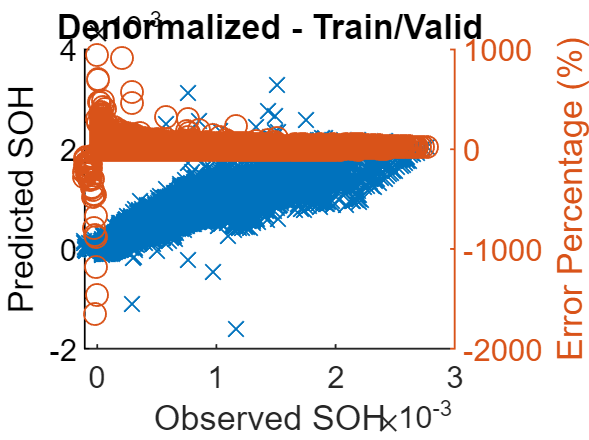

figure
hold on
plot(Y_trainValid_DeltaSOH,Yfit_trainValid_DeltaSOH,'x')
xlabel("Observed SOH")
ylabel("Predicted SOH")
%xlim([0 1.2]), ylim([0 1.2])

yyaxis right
ylabel('Error Percentage (%)')
plot(Y_trainValid_DeltaSOH,Y_trainValid_diff_percentage_VdDeltaSOH,'o');

hold off
title 'Denormalized - Train/Valid'


%%%%%%%%%%%%
RMSE_test_VdDeltaSOH = sqrt(mean((Y_test_DeltaSOH - Yfit_test_DeltaSOH).^2))

RMSE_test_VdDeltaSOH = 1.4453e-04

Y_test_DeltaSOH - Yfit_test_DeltaSOH

ans = 4488×1
1.0e-03 *

    0.0419
    0.0636
    0.0566
    0.0200
    0.0238
    0.0504
    0.0239
    0.0540
    0.0443
    0.0276


Y_test_diff_VdDeltaSOH = horzcat(Y_test_DeltaSOH,(Y_test_DeltaSOH-Yfit_test_DeltaSOH))

Y_test_diff_VdDeltaSOH = 4488×2
1.0e+00 *

    0.0001    0.0000
    0.0001    0.0001
    0.0001    0.0001
    0.0001    0.0000
    0.0002    0.0000
    0.0002    0.0001
    0.0002    0.0000
    0.0002    0.0001
    0.0002    0.0000
    0.0002    0.0000


Y_test_diff_percentage_VdDeltaSOH = abs(Y_test_DeltaSOH-Yfit_test_DeltaSOH)./Y_test_DeltaSOH.*100

Y_test_diff_percentage_VdDeltaSOH = 4488×1
   28.0112
   42.5199
   37.7908
   13.3595
   15.8302
   33.4801
   15.8014
   35.5403
   28.9586
   17.9059


Y_test_diff_percentage_avg_VdDeltaSOH = sum(Y_test_diff_percentage_VdDeltaSOH)/length(Y_test_diff_percentage_VdDeltaSOH)

Y_test_diff_percentage_avg_VdDeltaSOH = 30.4611

num = 1:length(Y_test_DeltaSOH);


result = horzcat(num',Y_test_DeltaSOH,(Y_test_DeltaSOH-Yfit_test_DeltaSOH),Y_test_diff_percentage_VdDeltaSOH);
result % 배터리 번호 / DeltaSOH 관찰값 / 오차 / 오차 퍼센티지 

result = 4488×4
    1.0000    0.0001    0.0000   28.0112
    2.0000    0.0001    0.0001   42.5199
    3.0000    0.0001    0.0001   37.7908
    4.0000    0.0001    0.0000   13.3595
    5.0000    0.0002    0.0000   15.8302
    6.0000    0.0002    0.0001   33.4801
    7.0000    0.0002    0.0000   15.8014
    8.0000    0.0002    0.0001   35.5403
    9.0000    0.0002    0.0000   28.9586
   10.0000    0.0002    0.0000   17.9059


result_mdl_Linear_VdDeltaSOH = table(num',Y_test_DeltaSOH,(Y_test_DeltaSOH-Yfit_test_DeltaSOH),Y_test_diff_percentage_VdDeltaSOH);
result_mdl_Linear_VdDeltaSOH.Properties.VariableNames = {'bat num','DeltaSOH','오차','오차비율'};
result_mdl_Linear_VdDeltaSOH

result_mdl_Linear_VdDeltaSOH = 4488×4 table
    bat num     DeltaSOH        오차       오차비율
    _______    __________    __________    _______

       1       0.00014965    4.1917e-05    28.011 
       2       0.00014965    6.3629e-05     42.52 
       3       0.00014968    5.6566e-05    37.791 
       4       0.00014984    2.0018e-05    13.359 
       5       0.00015013    2.3766e-05     15.83 
       6       0.00015059    5.0417e-05     33.48 
       7       0.00015124    2.3898e-05    15.801 
       8       0.00015207    5.4046e-05     35.54 
       9       0.00015306    4.4323e-05    28.959 
      10       0.00015416    2.7604e-05    17.906 
      11       0.00015536    2.3432e-05    15.082 
      12       0.00015666    4.7347e-05    30.223 
      13         0.000158    3.5107e-05     22.22 
      14       0.00015932    2.8998e-05    18.201 
      15

result_mdl_Linear_VdDeltaSOH_summary = table(RMSE_test_VdDeltaSOH,Y_test_diff_percentage_avg_VdDeltaSOH);
result_mdl_Linear_VdDeltaSOH_summary.Properties.VariableNames = {'RMSE','평균오차비율'};
result_mdl_Linear_VdDeltaSOH_summary 

result_mdl_Linear_VdDeltaSOH_summary = 1×2 table
       RMSE       평균오차비율
    __________    __________

    0.00014453      30.461  




RMSE_test_VdDeltaSOH

RMSE_test_VdDeltaSOH = 1.4453e-04

Y_test_diff_percentage_avg_VdDeltaSOH

Y_test_diff_percentage_avg_VdDeltaSOH = 30.4611

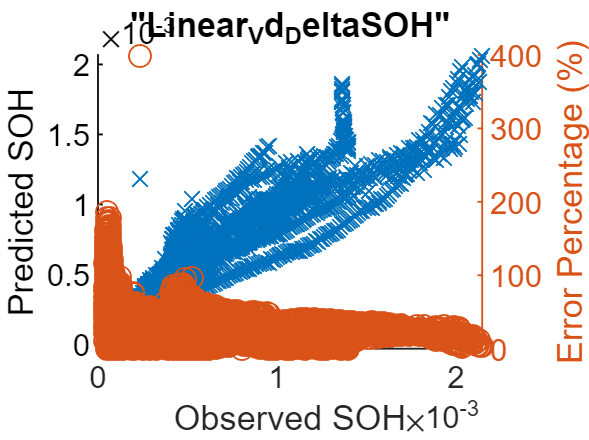


figure
hold on
plot(Y_test_DeltaSOH,Yfit_test_DeltaSOH,'x')
xlabel("Observed SOH")
ylabel("Predicted SOH")
%xlim([0 1.2]), ylim([0 1.2])

yyaxis right
ylabel('Error Percentage (%)')
plot(Y_test_DeltaSOH,Y_test_diff_percentage_VdDeltaSOH,'o');

hold off
title "Linear_Vd_DeltaSOH"

# 선형회귀 - 예측 - Ic (20) -DeltaRUL

#### 전류 패턴에 따른 라이프 사이클 예측 - 100개가 아니 20개로 

#### 선형회귀 - 정규화 필요 없지만 정규화해도 된다. 다른 머신러닝 방법을 위해 정규화 된것을 사용하자.

% % coeff_IcSOH = mdl_Linear_IcSOH.Coefficients.Estimate;
% % coeff_IcSOH'
% % x_trainValid_Ic(1,:)
% % yhat_trainValid_IcSOH = x_trainValid_Ic*coeff_IcSOH(2:21)+coeff_IcSOH(1);
% % yhat_trainValid_IcSOH'
% 
% % figure
% % hold on
% % plot(y_trainValid_SOH,yhat_trainValid_IcSOH,'x')
% % xlabel("Observed SOH")
% % ylabel("Predicted SOH")
% % hold off
% % title 'Normalized'
% 
% 
% figure
% plot(mdl_Linear_IcDeltaRUL)
% plotResiduals(mdl_Linear_IcDeltaRUL)
% 
% figure
% yfit_trainValid_DeltaRUL = predict(mdl_Linear_IcDeltaRUL,x_trainValid_Ic);
% yfit_trainValid_DeltaRUL'
% yfit_test_DeltaRUL = predict(mdl_Linear_IcDeltaRUL,x_test_Ic);
% yfit_test_DeltaRUL'
% 
% y_trainValid_DeltaRUL'
% y_test_DeltaRUL'
% Yfit_trainValid_DeltaRUL = yfit_trainValid_DeltaRUL * yrate_DeltaRUL + ymin_DeltaRUL;
% Yfit_test_DeltaRUL = yfit_test_DeltaRUL * yrate_DeltaRUL + ymin_DeltaRUL;
% 
% MAE_IcDeltaRUL = mean(abs(Yfit_trainValid_DeltaRUL-Y_trainValid_DeltaRUL))
% adjMAE_IcDeltaRUL = MAE_IcDeltaRUL/range(Y_trainValid_DeltaRUL)
% range(Y_trainValid_DeltaRUL) % Y_trainValid_DeltaRUL = range(X)는 X에 포함된 표본 데이터의 최댓값과 최솟값 간의 차이를 반환합니다.
% 
% (Y_trainValid_DeltaRUL - Yfit_trainValid_DeltaRUL)'    % Errors
% (Y_trainValid_DeltaRUL - Yfit_trainValid_DeltaRUL).^2;   % Squared Error
% histogram((Y_trainValid_DeltaRUL - Yfit_trainValid_DeltaRUL).^2)
% mean((Y_trainValid_DeltaRUL - Yfit_trainValid_DeltaRUL).^2);   % Mean Squared Error
% RMSE_trainValid_IcDeltaRUL = sqrt(mean((Y_trainValid_DeltaRUL - Yfit_trainValid_DeltaRUL).^2))  % Root Mean Squared Error
% 
% RMSE_test_IcDeltaRUL = sqrt(mean((Y_test_DeltaRUL - Yfit_test_DeltaRUL).^2))
% Y_test_DeltaRUL - Yfit_test_DeltaRUL
% Y_test_diff_IcDeltaRUL = horzcat(Y_test_DeltaRUL,(Y_test_DeltaRUL-Yfit_test_DeltaRUL))
% Y_test_diff_percentage_IcDeltaRUL = abs(Y_test_DeltaRUL-Yfit_test_DeltaRUL)./Y_test_DeltaRUL.*100
% Y_test_diff_percentage_avg_IcDeltaRUL = sum(Y_test_diff_percentage_IcDeltaRUL)/length(Y_test_diff_percentage_IcDeltaRUL)
% Y_trainValid_diff_IcDeltaRUL = horzcat(Y_trainValid_DeltaRUL,(Y_trainValid_DeltaRUL-Yfit_trainValid_DeltaRUL))
% Y_trainValid_diff_percentage_IcDeltaRUL = abs(Y_trainValid_DeltaRUL-Yfit_trainValid_DeltaRUL)./Y_trainValid_DeltaRUL.*100
% Y_trainValid_diff_percentage_avg_IcDeltaRUL = sum(Y_trainValid_diff_percentage_IcDeltaRUL)/length(Y_trainValid_diff_percentage_IcDeltaRUL)
% num = 1:length(Y_trainValid_DeltaRUL);
% 
% 
% result = horzcat(num',Y_trainValid_DeltaRUL,(Y_trainValid_DeltaRUL-Yfit_trainValid_DeltaRUL),Y_trainValid_diff_percentage_IcDeltaRUL);
% result % 배터리 번호 / DeltaRUL 관찰값 / 오차 / 오차 퍼센티지 
% result_mdl_Linear_IcDeltaRUL = table(num',Y_trainValid_DeltaRUL,(Y_trainValid_DeltaRUL-Yfit_trainValid_DeltaRUL),Y_trainValid_diff_percentage_IcDeltaRUL);
% result_mdl_Linear_IcDeltaRUL.Properties.VariableNames = {'bat num','DeltaRUL','오차','오차비율'};
% result_mdl_Linear_IcDeltaRUL
% result_mdl_Linear_IcDeltaRUL_summary = table(RMSE_test_IcDeltaRUL,Y_trainValid_diff_percentage_avg_IcDeltaRUL);
% result_mdl_Linear_IcDeltaRUL_summary.Properties.VariableNames = {'RMSE','평균오차비율'};
% result_mdl_Linear_IcDeltaRUL_summary 
% 
% figure
% hold on
% plot(Y_trainValid_DeltaRUL,Yfit_trainValid_DeltaRUL,'x')
% xlabel("Observed SOH")
% ylabel("Predicted SOH")
% %xlim([0 1.2]), ylim([0 1.2])
% 
% yyaxis right
% ylabel('Error Percentage (%)')
% plot(Y_trainValid_DeltaRUL,Y_trainValid_diff_percentage_IcDeltaRUL,'o');
% 
% hold off
% title 'Denormalized - Train/Valid'
% RMSE_test_IcDeltaRUL
% Y_trainValid_diff_percentage_avg_IcDeltaRUL
% 
% figure
% hold on
% plot(Y_test_DeltaRUL,Yfit_test_DeltaRUL,'x')
% xlabel("Observed SOH")
% ylabel("Predicted SOH")
% %xlim([0 1.2]), ylim([0 1.2])
% 
% yyaxis right
% ylabel('Error Percentage (%)')
% plot(Y_test_DeltaRUL,Y_test_diff_percentage_IcDeltaRUL,'o');
% 
% hold off
% title 'Denormalized - Test'


# 선형회귀 - 예측 - Vd (20) -DeltaRUL

#### 전류 패턴에 따른 라이프 사이클 예측 - 100개가 아니 20개로 

#### 선형회귀 - 정규화 필요 없지만 정규화해도 된다. 다른 머신러닝 방법을 위해 정규화 된것을 사용하자.

% % coeff_VdDeltaRUL = mdl_Linear_VdDeltaRUL.Coefficients.Estimate;
% % coeff_VdDeltaRUL'
% % x_trainValid_Vd(1,:)
% % yhat_trainValid_VdDeltaRUL = x_trainValid_Vd*coeff_VdDeltaRUL(2:21)+coeff_VdDeltaRUL(1);
% % yhat_trainValid_VdDeltaRUL'
% % figure
% % hold on
% % plot(y_trainValid_DeltaRUL,yhat_trainValid_VdDeltaRUL,'x')
% % xlabel("Observed SOH")
% % ylabel("Predicted SOH")
% % hold off
% % title 'Normalized'
% 
% figure
% plot(mdl_Linear_VdDeltaRUL)
% plotResiduals(mdl_Linear_VdDeltaRUL)
% figure
% yfit_trainValid_DeltaRUL = predict(mdl_Linear_VdDeltaRUL,x_trainValid_Vd);
% yfit_trainValid_DeltaRUL'
% yfit_test_DeltaRUL = predict(mdl_Linear_VdDeltaRUL,x_test_Vd);
% yfit_test_DeltaRUL'
% 
% y_trainValid_DeltaRUL'
% y_test_DeltaRUL'
% Yfit_trainValid_DeltaRUL = yfit_trainValid_DeltaRUL * yrate_DeltaRUL + ymin_DeltaRUL;
% Yfit_test_DeltaRUL = yfit_test_DeltaRUL * yrate_DeltaRUL + ymin_DeltaRUL;
% 
% MAE_VdDeltaRUL = mean(abs(Yfit_trainValid_DeltaRUL-Y_trainValid_DeltaRUL))
% adjMAE_VdDeltaRUL = MAE_VdDeltaRUL/range(Y_trainValid_DeltaRUL)
% range(Y_trainValid_DeltaRUL) % Y_trainValid_DeltaRUL = range(X)는 X에 포함된 표본 데이터의 최댓값과 최솟값 간의 차이를 반환합니다.
% 
% (Y_trainValid_DeltaRUL - Yfit_trainValid_DeltaRUL)'    % Errors
% (Y_trainValid_DeltaRUL - Yfit_trainValid_DeltaRUL).^2;   % Squared Error
% histogram((Y_trainValid_DeltaRUL - Yfit_trainValid_DeltaRUL).^2)
% mean((Y_trainValid_DeltaRUL - Yfit_trainValid_DeltaRUL).^2);   % Mean Squared Error
% RMSE_trainValid_VdDeltaRUL = sqrt(mean((Y_trainValid_DeltaRUL - Yfit_trainValid_DeltaRUL).^2))  % Root Mean Squared Error
% 
% RMSE_test_VdDeltaRUL = sqrt(mean((Y_test_DeltaRUL - Yfit_test_DeltaRUL).^2))
% Y_test_DeltaRUL - Yfit_test_DeltaRUL
% Y_test_diff_VdDeltaRUL = horzcat(Y_test_DeltaRUL,(Y_test_DeltaRUL-Yfit_test_DeltaRUL))
% Y_test_diff_percentage_VdDeltaRUL = abs(Y_test_DeltaRUL-Yfit_test_DeltaRUL)./Y_test_DeltaRUL.*100
% Y_test_diff_percentage_avg_VdDeltaRUL = sum(Y_test_diff_percentage_VdDeltaRUL)/length(Y_test_diff_percentage_VdDeltaRUL)
% Y_trainValid_diff_VdDeltaRUL = horzcat(Y_trainValid_DeltaRUL,(Y_trainValid_DeltaRUL-Yfit_trainValid_DeltaRUL))
% Y_trainValid_diff_percentage_VdDeltaRUL = abs(Y_trainValid_DeltaRUL-Yfit_trainValid_DeltaRUL)./Y_trainValid_DeltaRUL.*100
% Y_trainValid_diff_percentage_avg_VdDeltaRUL = sum(Y_trainValid_diff_percentage_VdDeltaRUL)/length(Y_trainValid_diff_percentage_VdDeltaRUL)
% num = 1:length(Y_trainValid_DeltaRUL);
% 
% 
% result = horzcat(num',Y_trainValid_DeltaRUL,(Y_trainValid_DeltaRUL-Yfit_trainValid_DeltaRUL),Y_trainValid_diff_percentage_VdDeltaRUL);
% result % 배터리 번호 / DeltaRUL 관찰값 / 오차 / 오차 퍼센티지 
% result_mdl_Linear_VdDeltaRUL = table(num',Y_trainValid_DeltaRUL,(Y_trainValid_DeltaRUL-Yfit_trainValid_DeltaRUL),Y_trainValid_diff_percentage_VdDeltaRUL);
% result_mdl_Linear_VdDeltaRUL.Properties.VariableNames = {'bat num','DeltaRUL','오차','오차비율'};
% result_mdl_Linear_VdDeltaRUL
% result_mdl_Linear_VdDeltaRUL_summary = table(RMSE_test_VdDeltaRUL,Y_trainValid_diff_percentage_avg_VdDeltaRUL);
% result_mdl_Linear_VdDeltaRUL_summary.Properties.VariableNames = {'RMSE','평균오차비율'};
% result_mdl_Linear_VdDeltaRUL_summary 
% 
% figure
% hold on
% plot(Y_trainValid_DeltaRUL,Yfit_trainValid_DeltaRUL,'x')
% xlabel("Observed SOH")
% ylabel("Predicted SOH")
% %xlim([0 1.2]), ylim([0 1.2])
% 
% yyaxis right
% ylabel('Error Percentage (%)')
% plot(Y_trainValid_DeltaRUL,Y_trainValid_diff_percentage_VdDeltaRUL,'o');
% 
% hold off
% title 'Denormalized - Train/Valid'
% RMSE_test_VdDeltaRUL
% Y_trainValid_diff_percentage_avg_VdDeltaRUL
% 
% figure
% hold on
% plot(Y_test_DeltaRUL,Yfit_test_DeltaRUL,'x')
% xlabel("Observed SOH")
% ylabel("Predicted SOH")
% %%xlim([0 1.2]), ylim([0 1.2])
% 
% yyaxis right
% ylabel('Error Percentage (%)')
% plot(Y_test_DeltaRUL,Y_test_diff_percentage_VdDeltaRUL,'o');
% 
% hold off
% title 'Denormalized - Test'

# Fnn Ic_SOH

yfit_trainValid_SOH = mdl_Fnn_IcSOH(xnorm_Ic([idxTrainAll idxValidAll ], :)')';
yfit_trainValid_SOH'

ans = 1×38367
    1.0100    0.9645    0.9658    0.9866    0.9897    0.9608    0.9919    0.9606    0.9985    0.9972    0.9780    0.9564    0.9558    0.9881    0.9928    0.9538    0.9535    0.9952    0.9516    0.9512    0.9508    0.9523    0.9956    0.9486    0.9469    0.9465    0.9912    0.9462    0.9960    0.9454


yfit_test_SOH = mdl_Fnn_IcSOH(xnorm_Ic( idxTestAll, :)')';
yfit_test_SOH'

ans = 1×4488
    0.9804    0.9781    0.9780    0.9767    0.9760    0.9744    0.9741    0.9733    0.9720    0.9713    0.9706    0.9686    0.9678    0.9675    0.9677    0.9666    0.9657    0.9654    0.9607    0.9597    0.9630    0.9642    0.9646    0.9613    0.9652    0.9650    0.9602    0.9632    0.9618    0.9596



y_trainValid_SOH'

ans = 1×38367
    0.9878    0.9872    0.9867    0.9861    0.9855    0.9849    0.9843    0.9837    0.9832    0.9826    0.9820    0.9814    0.9808    0.9802    0.9796    0.9790    0.9784    0.9778    0.9772    0.9766    0.9760    0.9754    0.9748    0.9742    0.9736    0.9730    0.9724    0.9718    0.9712    0.9706


y_test_SOH'

ans = 1×4488
    0.9869    0.9861    0.9852    0.9843    0.9835    0.9826    0.9817    0.9809    0.9800    0.9791    0.9782    0.9773    0.9764    0.9755    0.9745    0.9736    0.9727    0.9717    0.9708    0.9698    0.9689    0.9679    0.9670    0.9660    0.9650    0.9641    0.9631    0.9621    0.9611    0.9601



Yfit_trainValid_SOH = yfit_trainValid_SOH * yrate_SOH + ymin_SOH;
Yfit_test_SOH = yfit_test_SOH * yrate_SOH + ymin_SOH;
%Y_test_SOH = y_test_Ic_SOH * yrate_Ic_SOH + ymin_Ic_SOH;


MAE_IcSOH = mean(abs(Yfit_trainValid_SOH-Y_trainValid_SOH))

MAE_IcSOH = 0.0019

adjMAE_IcSOH = MAE_IcSOH/range(Y_trainValid_SOH)

adjMAE_IcSOH = 0.0108

range(Y_trainValid_SOH) % Y_trainValid_SOH = range(X)는 X에 포함된 표본 데이터의 최댓값과 최솟값 간의 차이를 반환합니다.

ans = 0.1734


(Y_trainValid_SOH - Yfit_trainValid_SOH)'    % Errors

ans = 1×38367
   -0.0039    0.0040    0.0036   -0.0001   -0.0007    0.0042   -0.0013    0.0040   -0.0027   -0.0025    0.0007    0.0043    0.0043   -0.0014   -0.0023    0.0044    0.0043   -0.0030    0.0045    0.0044    0.0044    0.0040   -0.0036    0.0045    0.0046    0.0046   -0.0033    0.0045   -0.0043    0.0044


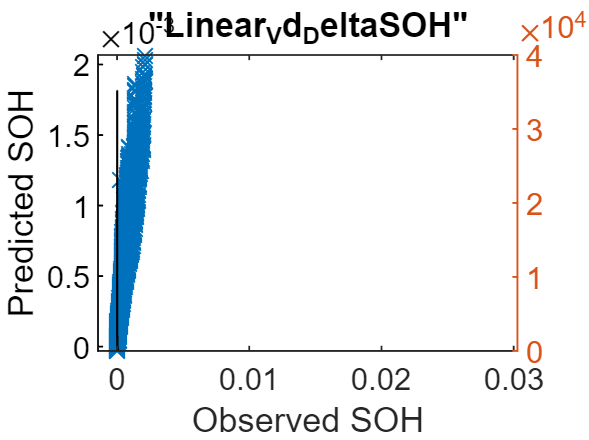

(Y_trainValid_SOH - Yfit_trainValid_SOH).^2;   % Squared Error
histogram((Y_trainValid_SOH - Yfit_trainValid_SOH).^2)

mean((Y_trainValid_SOH - Yfit_trainValid_SOH).^2);   % Mean Squared Error
RMSE_trainValid_IcSOH = sqrt(mean((Y_trainValid_SOH - Yfit_trainValid_SOH).^2))  % Root Mean Squared Error

RMSE_trainValid_IcSOH = 0.0028

Y_trainValid_diff_IcSOH = horzcat(Y_trainValid_SOH,(Y_trainValid_SOH-Yfit_trainValid_SOH))

Y_trainValid_diff_IcSOH = 38367×2
    1.0479   -0.0039
    1.0478    0.0040
    1.0477    0.0036
    1.0476   -0.0001
    1.0475   -0.0007
    1.0474    0.0042
    1.0473   -0.0013
    1.0472    0.0040
    1.0471   -0.0027
    1.0470   -0.0025


Y_trainValid_diff_percentage_IcSOH = abs(Y_trainValid_SOH-Yfit_trainValid_SOH)./Y_trainValid_SOH.*100

Y_trainValid_diff_percentage_IcSOH = 38367×1
    0.3683
    0.3775
    0.3453
    0.0087
    0.0693
    0.4006
    0.1252
    0.3833
    0.2541
    0.2426


Y_trainValid_diff_percentage_avg_IcSOH = sum(Y_trainValid_diff_percentage_IcSOH)/length(Y_trainValid_diff_percentage_IcSOH)

Y_trainValid_diff_percentage_avg_IcSOH = 0.1883

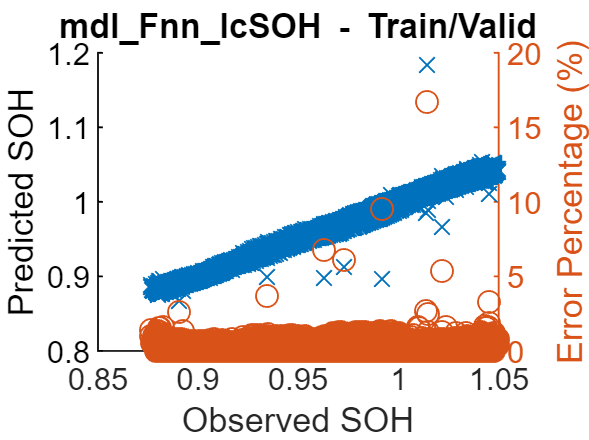

figure
hold on
plot(Y_trainValid_SOH,Yfit_trainValid_SOH,'x')
xlabel("Observed SOH")
ylabel("Predicted SOH")
%xlim([0 1.2]), ylim([0 1.2])

yyaxis right
ylabel('Error Percentage (%)')
plot(Y_trainValid_SOH,Y_trainValid_diff_percentage_IcSOH,'o');

hold off
title 'mdl\_Fnn\_IcSOH - Train/Valid'


%%%%%%%%%%%%
RMSE_test_IcSOH = sqrt(mean((Y_test_SOH - Yfit_test_SOH).^2))

RMSE_test_IcSOH = 0.0021

Y_test_SOH - Yfit_test_SOH

ans = 4488×1
    0.0011
    0.0014
    0.0012
    0.0013
    0.0013
    0.0014
    0.0013
    0.0013
    0.0014
    0.0014


Y_test_diff_IcSOH = horzcat(Y_test_SOH,(Y_test_SOH-Yfit_test_SOH))

Y_test_diff_IcSOH = 4488×2
    1.0477    0.0011
    1.0476    0.0014
    1.0474    0.0012
    1.0473    0.0013
    1.0471    0.0013
    1.0470    0.0014
    1.0468    0.0013
    1.0467    0.0013
    1.0465    0.0014
    1.0464    0.0014


Y_test_diff_percentage_IcSOH = abs(Y_test_SOH-Yfit_test_SOH)./Y_test_SOH.*100

Y_test_diff_percentage_IcSOH = 4488×1
    0.1079
    0.1319
    0.1190
    0.1273
    0.1242
    0.1354
    0.1272
    0.1252
    0.1316
    0.1296


Y_test_diff_percentage_avg_IcSOH = sum(Y_test_diff_percentage_IcSOH)/length(Y_test_diff_percentage_IcSOH)

Y_test_diff_percentage_avg_IcSOH = 0.1672

num = 1:length(Y_test_SOH);


result = horzcat(num',Y_test_SOH,(Y_test_SOH-Yfit_test_SOH),Y_test_diff_percentage_IcSOH);
result % 배터리 번호 / SOH 관찰값 / 오차 / 오차 퍼센티지 

result = 4488×4
    1.0000    1.0477    0.0011    0.1079
    2.0000    1.0476    0.0014    0.1319
    3.0000    1.0474    0.0012    0.1190
    4.0000    1.0473    0.0013    0.1273
    5.0000    1.0471    0.0013    0.1242
    6.0000    1.0470    0.0014    0.1354
    7.0000    1.0468    0.0013    0.1272
    8.0000    1.0467    0.0013    0.1252
    9.0000    1.0465    0.0014    0.1316
   10.0000    1.0464    0.0014    0.1296


result_mdl_Fnn_IcSOH = table(num',Y_test_SOH,(Y_test_SOH-Yfit_test_SOH),Y_test_diff_percentage_IcSOH);
result_mdl_Fnn_IcSOH.Properties.VariableNames = {'bat num','SOH','오차','오차비율'};
result_mdl_Fnn_IcSOH

result_mdl_Fnn_IcSOH = 4488×4 table
    bat num     SOH        오차       오차비율
    _______    ______    _________    _______

       1       1.0477      0.00113    0.10786
       2       1.0476    0.0013818     0.1319
       3       1.0474    0.0012469    0.11904
       4       1.0473    0.0013331    0.12729
       5       1.0471    0.0013005     0.1242
       6        1.047    0.0014179    0.13543
       7       1.0468    0.0013311    0.12716
       8       1.0467    0.0013109    0.12524
       9       1.0465    0.0013772     0.1316
      10       1.0464     0.001356    0.12959
      11       1.0462    0.0013251    0.12665
      12        1.046    0.0015058    0.14395
      13       1.0459     0.001496    0.14304
      14       1.0457    0.0013806    0.13202
      15       1.0456     0.001194     0.1142
      16       1.0454    0.0012127    0.11601


result_mdl_Fnn_IcSOH_summary = table(RMSE_test_IcSOH,Y_test_diff_percentage_avg_IcSOH);
result_mdl_Fnn_IcSOH_summary.Properties.VariableNames = {'RMSE','평균오차비율'};
result_mdl_Fnn_IcSOH_summary 

result_mdl_Fnn_IcSOH_summary = 1×2 table
      RMSE       평균오차비율
    _________    __________

    0.0021202     0.16718  




RMSE_test_IcSOH

RMSE_test_IcSOH = 0.0021

Y_test_diff_percentage_avg_IcSOH

Y_test_diff_percentage_avg_IcSOH = 0.1672

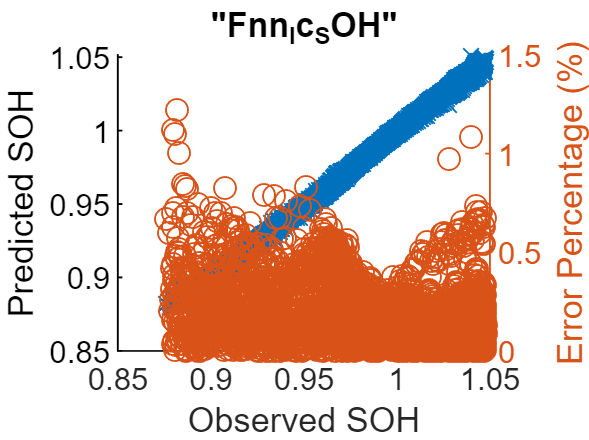


figure
hold on
plot(Y_test_SOH,Yfit_test_SOH,'x')
xlabel("Observed SOH")
ylabel("Predicted SOH")
%xlim([0 1.2]), ylim([0 1.2])

yyaxis right
ylabel('Error Percentage (%)')
plot(Y_test_SOH,Y_test_diff_percentage_IcSOH,'o');

hold off
title "Fnn_Ic_SOH"

%%%%%%%%%%%%%

# Fnn Vd_SOH

yfit_trainValid_SOH = mdl_Fnn_VdSOH(xnorm_Vd([idxTrainAll idxValidAll ], :)')';
yfit_trainValid_SOH'

ans = 1×38367
    0.9880    0.9909    0.9858    0.9868    0.9889    0.9894    0.9871    0.9879    0.9855    0.9861    0.9879    0.9876    0.9866    0.9887    0.9870    0.9863    0.9878    0.9863    0.9871    0.9854    0.9848    0.9819    0.9799    0.9819    0.9834    0.9818    0.9847    0.9824    0.9832    0.9814


yfit_test_SOH = mdl_Fnn_VdSOH(xnorm_Vd( idxTestAll, :)')';
yfit_test_SOH'

ans = 1×4488
    0.9435    0.9443    0.9439    0.9409    0.9388    0.9398    0.9402    0.9417    0.9398    0.9385    0.9403    0.9347    0.9351    0.9366    0.9364    0.9303    0.9314    0.9304    0.9288    0.9283    0.9319    0.9265    0.9291    0.9251    0.9280    0.9235    0.9209    0.9205    0.9215    0.9207



y_trainValid_SOH'

ans = 1×38367
    0.9878    0.9872    0.9867    0.9861    0.9855    0.9849    0.9843    0.9837    0.9832    0.9826    0.9820    0.9814    0.9808    0.9802    0.9796    0.9790    0.9784    0.9778    0.9772    0.9766    0.9760    0.9754    0.9748    0.9742    0.9736    0.9730    0.9724    0.9718    0.9712    0.9706


y_test_SOH'

ans = 1×4488
    0.9869    0.9861    0.9852    0.9843    0.9835    0.9826    0.9817    0.9809    0.9800    0.9791    0.9782    0.9773    0.9764    0.9755    0.9745    0.9736    0.9727    0.9717    0.9708    0.9698    0.9689    0.9679    0.9670    0.9660    0.9650    0.9641    0.9631    0.9621    0.9611    0.9601



Yfit_trainValid_SOH = yfit_trainValid_SOH * yrate_SOH + ymin_SOH;
Yfit_test_SOH = yfit_test_SOH * yrate_SOH + ymin_SOH;
%Y_test_SOH = y_test_Vd_SOH * yrate_Vd_SOH + ymin_Vd_SOH;


MAE_VdSOH = mean(abs(Yfit_trainValid_SOH-Y_trainValid_SOH))

MAE_VdSOH = 0.0073

adjMAE_VdSOH = MAE_VdSOH/range(Y_trainValid_SOH)

adjMAE_VdSOH = 0.0423

range(Y_trainValid_SOH) % Y_trainValid_SOH = range(X)는 X에 포함된 표본 데이터의 최댓값과 최솟값 간의 차이를 반환합니다.

ans = 0.1734


(Y_trainValid_SOH - Yfit_trainValid_SOH)'    % Errors

ans = 1×38367
   -0.0000   -0.0006    0.0001   -0.0001   -0.0006   -0.0008   -0.0005   -0.0007   -0.0004   -0.0006   -0.0010   -0.0011   -0.0010   -0.0015   -0.0013   -0.0013   -0.0016   -0.0015   -0.0017   -0.0015   -0.0015   -0.0011   -0.0009   -0.0013   -0.0017   -0.0015   -0.0021   -0.0018   -0.0021   -0.0019


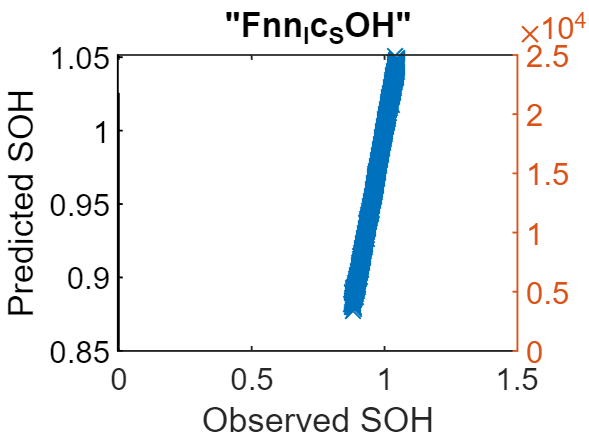

(Y_trainValid_SOH - Yfit_trainValid_SOH).^2;   % Squared Error
histogram((Y_trainValid_SOH - Yfit_trainValid_SOH).^2)

mean((Y_trainValid_SOH - Yfit_trainValid_SOH).^2);   % Mean Squared Error
RMSE_trainValid_VdSOH = sqrt(mean((Y_trainValid_SOH - Yfit_trainValid_SOH).^2))  % Root Mean Squared Error

RMSE_trainValid_VdSOH = 0.0097

Y_trainValid_diff_VdSOH = horzcat(Y_trainValid_SOH,(Y_trainValid_SOH-Yfit_trainValid_SOH))

Y_trainValid_diff_VdSOH = 38367×2
    1.0479   -0.0000
    1.0478   -0.0006
    1.0477    0.0001
    1.0476   -0.0001
    1.0475   -0.0006
    1.0474   -0.0008
    1.0473   -0.0005
    1.0472   -0.0007
    1.0471   -0.0004
    1.0470   -0.0006


Y_trainValid_diff_percentage_VdSOH = abs(Y_trainValid_SOH-Yfit_trainValid_SOH)./Y_trainValid_SOH.*100

Y_trainValid_diff_percentage_VdSOH = 38367×1
    0.0024
    0.0615
    0.0140
    0.0116
    0.0568
    0.0751
    0.0453
    0.0690
    0.0395
    0.0587


Y_trainValid_diff_percentage_avg_VdSOH = sum(Y_trainValid_diff_percentage_VdSOH)/length(Y_trainValid_diff_percentage_VdSOH)

Y_trainValid_diff_percentage_avg_VdSOH = 0.7415

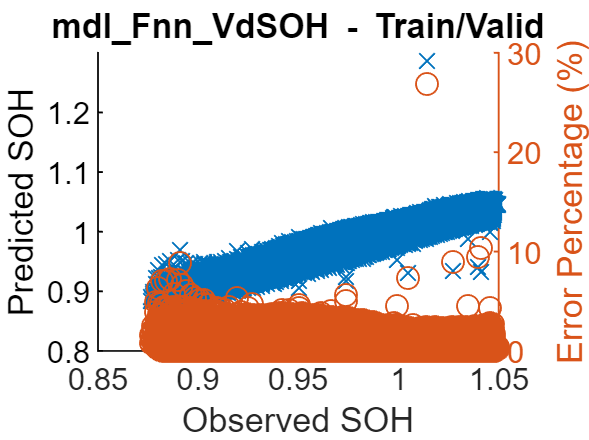

figure
hold on
plot(Y_trainValid_SOH,Yfit_trainValid_SOH,'x')
xlabel("Observed SOH")
ylabel("Predicted SOH")
%xlim([0 1.2]), ylim([0 1.2])

yyaxis right
ylabel('Error Percentage (%)')
plot(Y_trainValid_SOH,Y_trainValid_diff_percentage_VdSOH,'o');

hold off
title 'mdl\_Fnn\_VdSOH - Train/Valid'


%%%%%%%%%%%%
RMSE_test_VdSOH = sqrt(mean((Y_test_SOH - Yfit_test_SOH).^2))

RMSE_test_VdSOH = 0.0093

Y_test_SOH - Yfit_test_SOH

ans = 4488×1
    0.0075
    0.0073
    0.0072
    0.0076
    0.0078
    0.0074
    0.0072
    0.0068
    0.0070
    0.0070


Y_test_diff_VdSOH = horzcat(Y_test_SOH,(Y_test_SOH-Yfit_test_SOH))

Y_test_diff_VdSOH = 4488×2
    1.0477    0.0075
    1.0476    0.0073
    1.0474    0.0072
    1.0473    0.0076
    1.0471    0.0078
    1.0470    0.0074
    1.0468    0.0072
    1.0467    0.0068
    1.0465    0.0070
    1.0464    0.0070


Y_test_diff_percentage_VdSOH = abs(Y_test_SOH-Yfit_test_SOH)./Y_test_SOH.*100

Y_test_diff_percentage_VdSOH = 4488×1
    0.7200
    0.6930
    0.6852
    0.7212
    0.7408
    0.7093
    0.6896
    0.6495
    0.6660
    0.6736


Y_test_diff_percentage_avg_VdSOH = sum(Y_test_diff_percentage_VdSOH)/length(Y_test_diff_percentage_VdSOH)

Y_test_diff_percentage_avg_VdSOH = 0.7136

num = 1:length(Y_test_SOH);


result = horzcat(num',Y_test_SOH,(Y_test_SOH-Yfit_test_SOH),Y_test_diff_percentage_VdSOH);
result % 배터리 번호 / SOH 관찰값 / 오차 / 오차 퍼센티지 

result = 4488×4
    1.0000    1.0477    0.0075    0.7200
    2.0000    1.0476    0.0073    0.6930
    3.0000    1.0474    0.0072    0.6852
    4.0000    1.0473    0.0076    0.7212
    5.0000    1.0471    0.0078    0.7408
    6.0000    1.0470    0.0074    0.7093
    7.0000    1.0468    0.0072    0.6896
    8.0000    1.0467    0.0068    0.6495
    9.0000    1.0465    0.0070    0.6660
   10.0000    1.0464    0.0070    0.6736


result_mdl_Fnn_VdSOH = table(num',Y_test_SOH,(Y_test_SOH-Yfit_test_SOH),Y_test_diff_percentage_VdSOH);
result_mdl_Fnn_VdSOH.Properties.VariableNames = {'bat num','SOH','오차','오차비율'};
result_mdl_Fnn_VdSOH

result_mdl_Fnn_VdSOH = 4488×4 table
    bat num     SOH        오차       오차비율
    _______    ______    _________    _______

       1       1.0477    0.0075435       0.72
       2       1.0476    0.0072594    0.69298
       3       1.0474    0.0071773    0.68524
       4       1.0473    0.0075529     0.7212
       5       1.0471    0.0077571     0.7408
       6        1.047    0.0074261     0.7093
       7       1.0468    0.0072188    0.68959
       8       1.0467    0.0067985    0.64954
       9       1.0465    0.0069702    0.66605
      10       1.0464    0.0070478    0.67356
      11       1.0462    0.0065872    0.62963
      12        1.046    0.0073948    0.70693
      13       1.0459    0.0071781    0.68632
      14       1.0457    0.0067542    0.64589
      15       1.0456    0.0066289      0.634
      16       1.0454    0.0075303    0.72032


result_mdl_Fnn_VdSOH_summary = table(RMSE_test_VdSOH,Y_test_diff_percentage_avg_VdSOH);
result_mdl_Fnn_VdSOH_summary.Properties.VariableNames = {'RMSE','평균오차비율'};
result_mdl_Fnn_VdSOH_summary 

result_mdl_Fnn_VdSOH_summary = 1×2 table
      RMSE       평균오차비율
    _________    __________

    0.0093153     0.71364  




RMSE_test_VdSOH

RMSE_test_VdSOH = 0.0093

Y_test_diff_percentage_avg_VdSOH

Y_test_diff_percentage_avg_VdSOH = 0.7136

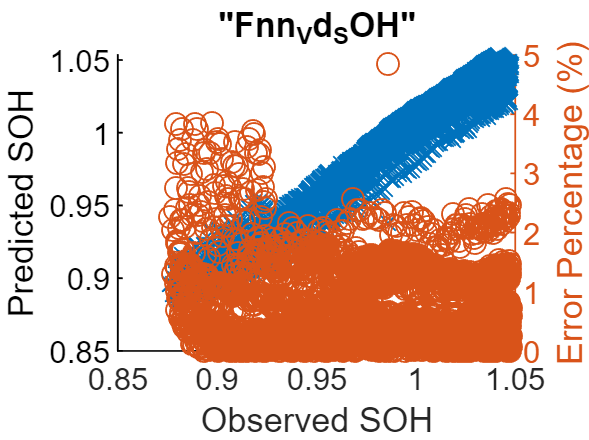


figure
hold on
plot(Y_test_SOH,Yfit_test_SOH,'x')
xlabel("Observed SOH")
ylabel("Predicted SOH")
%xlim([0 1.2]), ylim([0 1.2])

yyaxis right
ylabel('Error Percentage (%)')
plot(Y_test_SOH,Y_test_diff_percentage_VdSOH,'o');

hold off
%title 'mdl\_Fnn\_VdSOH - Test'
title "Fnn_Vd_SOH"

# Fnn Ic_DeltaSOH

yfit_trainValid_DeltaSOH = mdl_Fnn_IcDeltaSOH(xnorm_Ic([idxTrainAll idxValidAll ], :)')';
yfit_trainValid_DeltaSOH'

ans = 1×38367
    0.0611    0.0595    0.0596    0.0618    0.0619    0.0596    0.0621    0.0597    0.0620    0.0620    0.0618    0.0595    0.0594    0.0623    0.0622    0.0595    0.0595    0.0620    0.0594    0.0593    0.0591    0.0594    0.0620    0.0591    0.0592    0.0592    0.0664    0.0594    0.0773    0.0594


yfit_test_DeltaSOH = mdl_Fnn_IcDeltaSOH(xnorm_Ic( idxTestAll, :)')';
yfit_test_DeltaSOH'

ans = 1×4488
    0.0936    0.0958    0.0958    0.0971    0.0978    0.0992    0.0995    0.1003    0.1015    0.1022    0.1028    0.1047    0.1054    0.1057    0.1056    0.1066    0.1073    0.1078    0.1154    0.1162    0.1099    0.1088    0.1085    0.1150    0.1079    0.1082    0.1158    0.1099    0.1111    0.1131



y_trainValid_DeltaSOH'

ans = 1×38367
    0.0716    0.0716    0.0716    0.0715    0.0715    0.0715    0.0715    0.0716    0.0716    0.0717    0.0718    0.0719    0.0720    0.0722    0.0723    0.0725    0.0726    0.0727    0.0728    0.0729    0.0729    0.0729    0.0730    0.0730    0.0730    0.0730    0.0731    0.0731    0.0732    0.0733


y_test_DeltaSOH'

ans = 1×4488
    0.0885    0.0885    0.0885    0.0886    0.0887    0.0888    0.0890    0.0893    0.0897    0.0901    0.0905    0.0909    0.0914    0.0918    0.0923    0.0927    0.0931    0.0934    0.0937    0.0939    0.0941    0.0943    0.0944    0.0946    0.0948    0.0951    0.0954    0.0958    0.0963    0.0968



Yfit_trainValid_DeltaSOH = yfit_trainValid_DeltaSOH * yrate_DeltaSOH + ymin_DeltaSOH;
Yfit_test_DeltaSOH = yfit_test_DeltaSOH * yrate_DeltaSOH + ymin_DeltaSOH;
%Y_test_DeltaSOH = y_test_Ic_DeltaSOH * yrate_Ic_DeltaSOH + ymin_Ic_DeltaSOH;


MAE_IcDeltaSOH = mean(abs(Yfit_trainValid_DeltaSOH-Y_trainValid_DeltaSOH))

MAE_IcDeltaSOH = 1.0839e-04

adjMAE_IcDeltaSOH = MAE_IcDeltaSOH/range(Y_trainValid_DeltaSOH)

adjMAE_IcDeltaSOH = 0.0377

range(Y_trainValid_DeltaSOH) % Y_trainValid_DeltaSOH = range(X)는 X에 포함된 표본 데이터의 최댓값과 최솟값 간의 차이를 반환합니다.

ans = 0.0029


(Y_trainValid_DeltaSOH - Yfit_trainValid_DeltaSOH)'    % Errors

ans = 1×38367
1.0e+00 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000


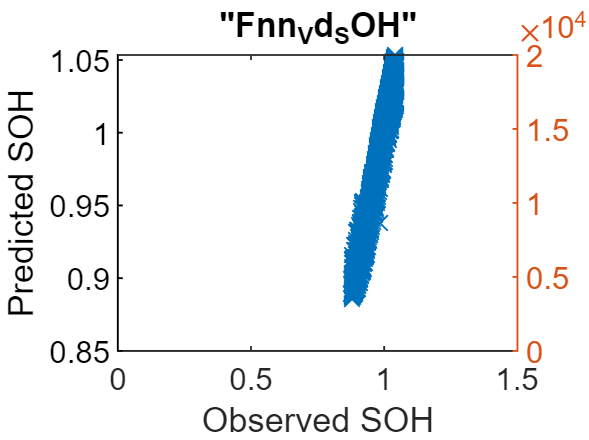

(Y_trainValid_DeltaSOH - Yfit_trainValid_DeltaSOH).^2;   % Squared Error
histogram((Y_trainValid_DeltaSOH - Yfit_trainValid_DeltaSOH).^2)

mean((Y_trainValid_DeltaSOH - Yfit_trainValid_DeltaSOH).^2);   % Mean Squared Error
RMSE_trainValid_IcDeltaSOH = sqrt(mean((Y_trainValid_DeltaSOH - Yfit_trainValid_DeltaSOH).^2))  % Root Mean Squared Error

RMSE_trainValid_IcDeltaSOH = 1.6167e-04

Y_trainValid_diff_IcDeltaSOH = horzcat(Y_trainValid_DeltaSOH,(Y_trainValid_DeltaSOH-Yfit_trainValid_DeltaSOH))

Y_trainValid_diff_IcDeltaSOH = 38367×2
1.0e+00 *

    0.0001    0.0000
    0.0001    0.0000
    0.0001    0.0000
    0.0001    0.0000
    0.0001    0.0000
    0.0001    0.0000
    0.0001    0.0000
    0.0001    0.0000
    0.0001    0.0000
    0.0001    0.0000


Y_trainValid_diff_percentage_IcDeltaSOH = abs(Y_trainValid_DeltaSOH-Yfit_trainValid_DeltaSOH)./Y_trainValid_DeltaSOH.*100

Y_trainValid_diff_percentage_IcDeltaSOH = 38367×1
   29.7541
   34.2484
   33.9365
   27.6991
   27.3034
   33.8641
   26.9514
   33.8053
   27.4097
   27.4682


Y_trainValid_diff_percentage_avg_IcDeltaSOH = sum(Y_trainValid_diff_percentage_IcDeltaSOH)/length(Y_trainValid_diff_percentage_IcDeltaSOH)

Y_trainValid_diff_percentage_avg_IcDeltaSOH = 33.6871

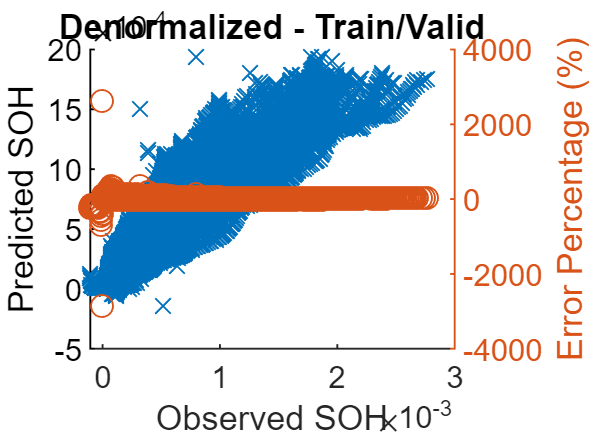

figure
hold on
plot(Y_trainValid_DeltaSOH,Yfit_trainValid_DeltaSOH,'x')
xlabel("Observed SOH")
ylabel("Predicted SOH")
%xlim([0 1.2]), ylim([0 1.2])

yyaxis right
ylabel('Error Percentage (%)')
plot(Y_trainValid_DeltaSOH,Y_trainValid_diff_percentage_IcDeltaSOH,'o');

hold off
title 'Denormalized - Train/Valid'


%%%%%%%%%%%%
RMSE_test_IcDeltaSOH = sqrt(mean((Y_test_DeltaSOH - Yfit_test_DeltaSOH).^2))

RMSE_test_IcDeltaSOH = 1.6485e-04

Y_test_DeltaSOH - Yfit_test_DeltaSOH

ans = 4488×1
1.0e-03 *

   -0.0147
   -0.0209
   -0.0210
   -0.0245
   -0.0262
   -0.0300
   -0.0301
   -0.0317
   -0.0340
   -0.0349


Y_test_diff_IcDeltaSOH = horzcat(Y_test_DeltaSOH,(Y_test_DeltaSOH-Yfit_test_DeltaSOH))

Y_test_diff_IcDeltaSOH = 4488×2
1.0e+00 *

    0.0001   -0.0000
    0.0001   -0.0000
    0.0001   -0.0000
    0.0001   -0.0000
    0.0002   -0.0000
    0.0002   -0.0000
    0.0002   -0.0000
    0.0002   -0.0000
    0.0002   -0.0000
    0.0002   -0.0000


Y_test_diff_percentage_IcDeltaSOH = abs(Y_test_DeltaSOH-Yfit_test_DeltaSOH)./Y_test_DeltaSOH.*100

Y_test_diff_percentage_IcDeltaSOH = 4488×1
    9.8388
   13.9873
   14.0075
   16.3748
   17.4617
   19.9216
   19.9218
   20.8241
   22.2080
   22.6368


Y_test_diff_percentage_avg_IcDeltaSOH = sum(Y_test_diff_percentage_IcDeltaSOH)/length(Y_test_diff_percentage_IcDeltaSOH)

Y_test_diff_percentage_avg_IcDeltaSOH = 26.3614

num = 1:length(Y_test_DeltaSOH);


result = horzcat(num',Y_test_DeltaSOH,(Y_test_DeltaSOH-Yfit_test_DeltaSOH),Y_test_diff_percentage_IcDeltaSOH);
result % 배터리 번호 / DeltaSOH 관찰값 / 오차 / 오차 퍼센티지 

result = 4488×4
    1.0000    0.0001   -0.0000    9.8388
    2.0000    0.0001   -0.0000   13.9873
    3.0000    0.0001   -0.0000   14.0075
    4.0000    0.0001   -0.0000   16.3748
    5.0000    0.0002   -0.0000   17.4617
    6.0000    0.0002   -0.0000   19.9216
    7.0000    0.0002   -0.0000   19.9218
    8.0000    0.0002   -0.0000   20.8241
    9.0000    0.0002   -0.0000   22.2080
   10.0000    0.0002   -0.0000   22.6368


result_mdl_Fnn_IcDeltaSOH = table(num',Y_test_DeltaSOH,(Y_test_DeltaSOH-Yfit_test_DeltaSOH),Y_test_diff_percentage_IcDeltaSOH);
result_mdl_Fnn_IcDeltaSOH.Properties.VariableNames = {'bat num','DeltaSOH','오차','오차비율'};
result_mdl_Fnn_IcDeltaSOH

result_mdl_Fnn_IcDeltaSOH = 4488×4 table
    bat num     DeltaSOH        오차        오차비율
    _______    __________    ___________    _______

       1       0.00014965    -1.4723e-05    9.8388 
       2       0.00014965    -2.0931e-05    13.987 
       3       0.00014968    -2.0967e-05    14.008 
       4       0.00014984    -2.4536e-05    16.375 
       5       0.00015013    -2.6216e-05    17.462 
       6       0.00015059    -2.9999e-05    19.922 
       7       0.00015124    -3.0129e-05    19.922 
       8       0.00015207    -3.1667e-05    20.824 
       9       0.00015306    -3.3991e-05    22.208 
      10       0.00015416    -3.4897e-05    22.637 
      11       0.00015536    -3.5491e-05    22.844 
      12       0.00015666    -3.9569e-05    25.258 
      13         0.000158    -4.0358e-05    25.543 
      14       0.00015932    -3.9843e-05    25.

result_mdl_Fnn_IcDeltaSOH_summary = table(RMSE_test_IcDeltaSOH,Y_test_diff_percentage_avg_IcDeltaSOH);
result_mdl_Fnn_IcDeltaSOH_summary.Properties.VariableNames = {'RMSE','평균오차비율'};
result_mdl_Fnn_IcDeltaSOH_summary 

result_mdl_Fnn_IcDeltaSOH_summary = 1×2 table
       RMSE       평균오차비율
    __________    __________

    0.00016485      26.361  




RMSE_test_IcDeltaSOH

RMSE_test_IcDeltaSOH = 1.6485e-04

Y_test_diff_percentage_avg_IcDeltaSOH

Y_test_diff_percentage_avg_IcDeltaSOH = 26.3614


figure
hold on
plot(Y_test_DeltaSOH,Yfit_test_DeltaSOH,'x')
xlabel("Observed SOH")
ylabel("Predicted SOH")
%xlim([0 1.2]), ylim([0 1.2])

yyaxis right
ylabel('Error Percentage (%)')
plot(Y_test_DeltaSOH,Y_test_diff_percentage_IcDeltaSOH,'o');

hold off
title "Fnn_Vc_DeltaSOH"


# Fnn Vd_DeltaSOH

yfit_trainValid_DeltaSOH = mdl_Fnn_VdDeltaSOH(xnorm_Vd([idxTrainAll idxValidAll ], :)')';
yfit_trainValid_DeltaSOH'

ans = 1×38367
    0.0962    0.0963    0.0974    0.0969    0.0962    0.0962    0.0975    0.0979    0.0977    0.0978    0.0978    0.0974    0.0971    0.0978    0.0981    0.0972    0.0982    0.0985    0.0985    0.0968    0.0959    0.0955    0.0962    0.0964    0.0972    0.0990    0.0990    0.0988    0.0987    0.0990


yfit_test_DeltaSOH = mdl_Fnn_VdDeltaSOH(xnorm_Vd( idxTestAll, :)')';
yfit_test_DeltaSOH'

ans = 1×4488
    0.0905    0.0918    0.0924    0.0927    0.0929    0.0934    0.0934    0.0932    0.0937    0.0937    0.0936    0.0942    0.0941    0.0926    0.0927    0.0946    0.0949    0.0954    0.0957    0.0963    0.0942    0.0908    0.0879    0.0862    0.0858    0.0851    0.0847    0.0852    0.0888    0.0945



y_trainValid_DeltaSOH'

ans = 1×38367
    0.0716    0.0716    0.0716    0.0715    0.0715    0.0715    0.0715    0.0716    0.0716    0.0717    0.0718    0.0719    0.0720    0.0722    0.0723    0.0725    0.0726    0.0727    0.0728    0.0729    0.0729    0.0729    0.0730    0.0730    0.0730    0.0730    0.0731    0.0731    0.0732    0.0733


y_test_DeltaSOH'

ans = 1×4488
    0.0885    0.0885    0.0885    0.0886    0.0887    0.0888    0.0890    0.0893    0.0897    0.0901    0.0905    0.0909    0.0914    0.0918    0.0923    0.0927    0.0931    0.0934    0.0937    0.0939    0.0941    0.0943    0.0944    0.0946    0.0948    0.0951    0.0954    0.0958    0.0963    0.0968



Yfit_trainValid_DeltaSOH = yfit_trainValid_DeltaSOH * yrate_DeltaSOH + ymin_DeltaSOH;
Yfit_test_DeltaSOH = yfit_test_DeltaSOH * yrate_DeltaSOH + ymin_DeltaSOH;
%Y_test_DeltaSOH = y_test_Vd_DeltaSOH * yrate_Vd_DeltaSOH + ymin_Vd_DeltaSOH;


MAE_VdDeltaSOH = mean(abs(Yfit_trainValid_DeltaSOH-Y_trainValid_DeltaSOH))

MAE_VdDeltaSOH = 1.1008e-04

adjMAE_VdDeltaSOH = MAE_VdDeltaSOH/range(Y_trainValid_DeltaSOH)

adjMAE_VdDeltaSOH = 0.0383

range(Y_trainValid_DeltaSOH) % Y_trainValid_DeltaSOH = range(X)는 X에 포함된 표본 데이터의 최댓값과 최솟값 간의 차이를 반환합니다.

ans = 0.0029


(Y_trainValid_DeltaSOH - Yfit_trainValid_DeltaSOH)'    % Errors

ans = 1×38367
1.0e+00 *

   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001


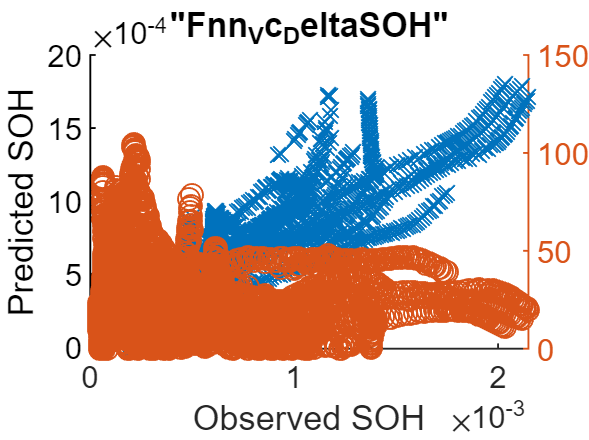

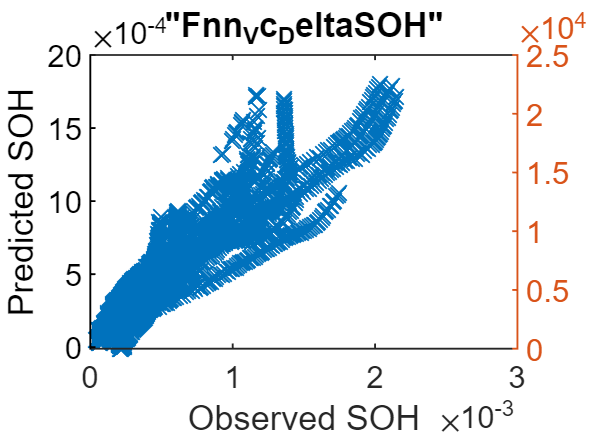

(Y_trainValid_DeltaSOH - Yfit_trainValid_DeltaSOH).^2;   % Squared Error
histogram((Y_trainValid_DeltaSOH - Yfit_trainValid_DeltaSOH).^2)

mean((Y_trainValid_DeltaSOH - Yfit_trainValid_DeltaSOH).^2);   % Mean Squared Error
RMSE_trainValid_VdDeltaSOH = sqrt(mean((Y_trainValid_DeltaSOH - Yfit_trainValid_DeltaSOH).^2))  % Root Mean Squared Error

RMSE_trainValid_VdDeltaSOH = 1.6909e-04

Y_trainValid_diff_VdDeltaSOH = horzcat(Y_trainValid_DeltaSOH,(Y_trainValid_DeltaSOH-Yfit_trainValid_DeltaSOH))

Y_trainValid_diff_VdDeltaSOH = 38367×2
1.0e+00 *

    0.0001   -0.0001
    0.0001   -0.0001
    0.0001   -0.0001
    0.0001   -0.0001
    0.0001   -0.0001
    0.0001   -0.0001
    0.0001   -0.0001
    0.0001   -0.0001
    0.0001   -0.0001
    0.0001   -0.0001


Y_trainValid_diff_percentage_VdDeltaSOH = abs(Y_trainValid_DeltaSOH-Yfit_trainValid_DeltaSOH)./Y_trainValid_DeltaSOH.*100

Y_trainValid_diff_percentage_VdDeltaSOH = 38367×1
   70.0560
   70.1301
   73.6244
   72.3335
   70.4262
   70.2150
   73.8191
   74.8664
   74.1598
   74.0760


Y_trainValid_diff_percentage_avg_VdDeltaSOH = sum(Y_trainValid_diff_percentage_VdDeltaSOH)/length(Y_trainValid_diff_percentage_VdDeltaSOH)

Y_trainValid_diff_percentage_avg_VdDeltaSOH = 34.8344

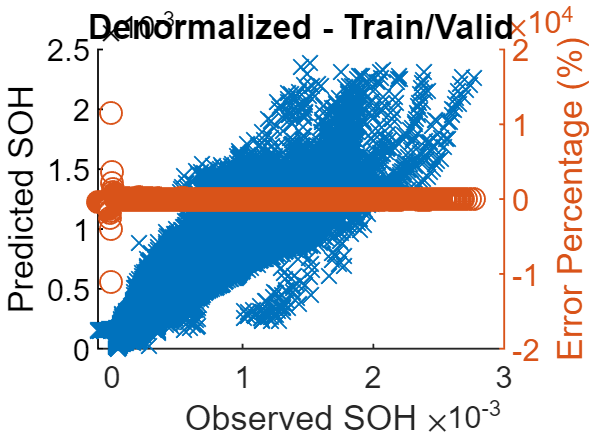

figure
hold on
plot(Y_trainValid_DeltaSOH,Yfit_trainValid_DeltaSOH,'x')
xlabel("Observed SOH")
ylabel("Predicted SOH")
%xlim([0 1.2]), ylim([0 1.2])

yyaxis right
ylabel('Error Percentage (%)')
plot(Y_trainValid_DeltaSOH,Y_trainValid_diff_percentage_VdDeltaSOH,'o');

hold off
title 'Denormalized - Train/Valid'


%%%%%%%%%%%%
RMSE_test_VdDeltaSOH = sqrt(mean((Y_test_DeltaSOH - Yfit_test_DeltaSOH).^2))

RMSE_test_VdDeltaSOH = 1.6277e-04

Y_test_DeltaSOH - Yfit_test_DeltaSOH

ans = 4488×1
1.0e-03 *

   -0.0058
   -0.0096
   -0.0111
   -0.0118
   -0.0122
   -0.0131
   -0.0127
   -0.0113
   -0.0117
   -0.0105


Y_test_diff_VdDeltaSOH = horzcat(Y_test_DeltaSOH,(Y_test_DeltaSOH-Yfit_test_DeltaSOH))

Y_test_diff_VdDeltaSOH = 4488×2
1.0e+00 *

    0.0001   -0.0000
    0.0001   -0.0000
    0.0001   -0.0000
    0.0001   -0.0000
    0.0002   -0.0000
    0.0002   -0.0000
    0.0002   -0.0000
    0.0002   -0.0000
    0.0002   -0.0000
    0.0002   -0.0000


Y_test_diff_percentage_VdDeltaSOH = abs(Y_test_DeltaSOH-Yfit_test_DeltaSOH)./Y_test_DeltaSOH.*100

Y_test_diff_percentage_VdDeltaSOH = 4488×1
    3.8938
    6.4203
    7.4189
    7.8854
    8.0962
    8.6941
    8.3648
    7.3983
    7.6501
    6.8298


Y_test_diff_percentage_avg_VdDeltaSOH = sum(Y_test_diff_percentage_VdDeltaSOH)/length(Y_test_diff_percentage_VdDeltaSOH)

Y_test_diff_percentage_avg_VdDeltaSOH = 32.6921

num = 1:length(Y_test_DeltaSOH);


result = horzcat(num',Y_test_DeltaSOH,(Y_test_DeltaSOH-Yfit_test_DeltaSOH),Y_test_diff_percentage_VdDeltaSOH);
result % 배터리 번호 / DeltaSOH 관찰값 / 오차 / 오차 퍼센티지 

result = 4488×4
    1.0000    0.0001   -0.0000    3.8938
    2.0000    0.0001   -0.0000    6.4203
    3.0000    0.0001   -0.0000    7.4189
    4.0000    0.0001   -0.0000    7.8854
    5.0000    0.0002   -0.0000    8.0962
    6.0000    0.0002   -0.0000    8.6941
    7.0000    0.0002   -0.0000    8.3648
    8.0000    0.0002   -0.0000    7.3983
    9.0000    0.0002   -0.0000    7.6501
   10.0000    0.0002   -0.0000    6.8298


result_mdl_Fnn_VdDeltaSOH = table(num',Y_test_DeltaSOH,(Y_test_DeltaSOH-Yfit_test_DeltaSOH),Y_test_diff_percentage_VdDeltaSOH);
result_mdl_Fnn_VdDeltaSOH.Properties.VariableNames = {'bat num','DeltaSOH','오차','오차비율'};
result_mdl_Fnn_VdDeltaSOH

result_mdl_Fnn_VdDeltaSOH = 4488×4 table
    bat num     DeltaSOH        오차        오차비율
    _______    __________    ___________    _______

       1       0.00014965     -5.827e-06     3.8938
       2       0.00014965    -9.6077e-06     6.4203
       3       0.00014968    -1.1105e-05     7.4189
       4       0.00014984    -1.1815e-05     7.8854
       5       0.00015013    -1.2155e-05     8.0962
       6       0.00015059    -1.3092e-05     8.6941
       7       0.00015124    -1.2651e-05     8.3648
       8       0.00015207    -1.1251e-05     7.3983
       9       0.00015306    -1.1709e-05     7.6501
      10       0.00015416    -1.0529e-05     6.8298
      11       0.00015536    -8.8795e-06     5.7154
      12       0.00015666    -9.5086e-06     6.0697
      13         0.000158    -7.8386e-06     4.9612
      14       0.00015932    -2.0775e-06     1.

result_mdl_Fnn_VdDeltaSOH_summary = table(RMSE_test_VdDeltaSOH,Y_test_diff_percentage_avg_VdDeltaSOH);
result_mdl_Fnn_VdDeltaSOH_summary.Properties.VariableNames = {'RMSE','평균오차비율'};
result_mdl_Fnn_VdDeltaSOH_summary 

result_mdl_Fnn_VdDeltaSOH_summary = 1×2 table
       RMSE       평균오차비율
    __________    __________

    0.00016277      32.692  




RMSE_test_VdDeltaSOH

RMSE_test_VdDeltaSOH = 1.6277e-04

Y_test_diff_percentage_avg_VdDeltaSOH

Y_test_diff_percentage_avg_VdDeltaSOH = 32.6921

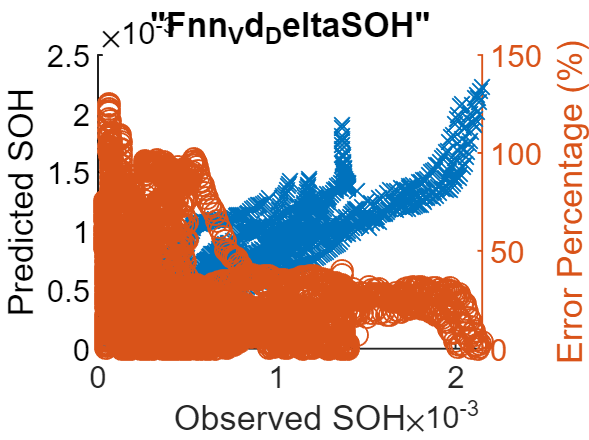


figure
hold on
plot(Y_test_DeltaSOH,Yfit_test_DeltaSOH,'x')
xlabel("Observed SOH")
ylabel("Predicted SOH")
%xlim([0 1.2]), ylim([0 1.2])

yyaxis right
ylabel('Error Percentage (%)')
plot(Y_test_DeltaSOH,Y_test_diff_percentage_VdDeltaSOH,'o');

hold off
title "Fnn_Vd_DeltaSOH"

# Fnn3 Ic_SOH

yfit_trainValid_SOH = mdl_Fnn3_IcSOH(xnorm_Ic([idxTrainAll idxValidAll ], :)')';
yfit_trainValid_SOH'

ans = 1×38367
    0.9625    0.9430    0.9439    0.9537    0.9550    0.9397    0.9551    0.9394    0.9553    0.9542    0.9474    0.9362    0.9358    0.9505    0.9516    0.9339    0.9336    0.9503    0.9321    0.9319    0.9319    0.9329    0.9488    0.9301    0.9285    0.9279    0.9455    0.9272    0.9474    0.9266


yfit_test_SOH = mdl_Fnn3_IcSOH(xnorm_Ic( idxTestAll, :)')';
yfit_test_SOH'

ans = 1×4488
    0.9338    0.9311    0.9310    0.9294    0.9287    0.9268    0.9264    0.9256    0.9241    0.9231    0.9222    0.9200    0.9190    0.9188    0.9189    0.9177    0.9166    0.9163    0.9255    0.9244    0.9135    0.9149    0.9155    0.9261    0.9162    0.9159    0.9249    0.9137    0.9120    0.9093



y_trainValid_SOH'

ans = 1×38367
    0.9878    0.9872    0.9867    0.9861    0.9855    0.9849    0.9843    0.9837    0.9832    0.9826    0.9820    0.9814    0.9808    0.9802    0.9796    0.9790    0.9784    0.9778    0.9772    0.9766    0.9760    0.9754    0.9748    0.9742    0.9736    0.9730    0.9724    0.9718    0.9712    0.9706


y_test_SOH'

ans = 1×4488
    0.9869    0.9861    0.9852    0.9843    0.9835    0.9826    0.9817    0.9809    0.9800    0.9791    0.9782    0.9773    0.9764    0.9755    0.9745    0.9736    0.9727    0.9717    0.9708    0.9698    0.9689    0.9679    0.9670    0.9660    0.9650    0.9641    0.9631    0.9621    0.9611    0.9601



Yfit_trainValid_SOH = yfit_trainValid_SOH * yrate_SOH + ymin_SOH;
Yfit_test_SOH = yfit_test_SOH * yrate_SOH + ymin_SOH;
%Y_test_SOH = y_test_Ic_SOH * yrate_Ic_SOH + ymin_Ic_SOH;


MAE_IcSOH = mean(abs(Yfit_trainValid_SOH-Y_trainValid_SOH))

MAE_IcSOH = 0.0036

adjMAE_IcSOH = MAE_IcSOH/range(Y_trainValid_SOH)

adjMAE_IcSOH = 0.0210

range(Y_trainValid_SOH) % Y_trainValid_SOH = range(X)는 X에 포함된 표본 데이터의 최댓값과 최솟값 간의 차이를 반환합니다.

ans = 0.1734


(Y_trainValid_SOH - Yfit_trainValid_SOH)'    % Errors

ans = 1×38367
    0.0044    0.0077    0.0074    0.0056    0.0053    0.0079    0.0051    0.0077    0.0048    0.0049    0.0060    0.0079    0.0078    0.0052    0.0049    0.0078    0.0078    0.0048    0.0078    0.0078    0.0077    0.0074    0.0045    0.0077    0.0078    0.0078    0.0047    0.0077    0.0041    0.0076


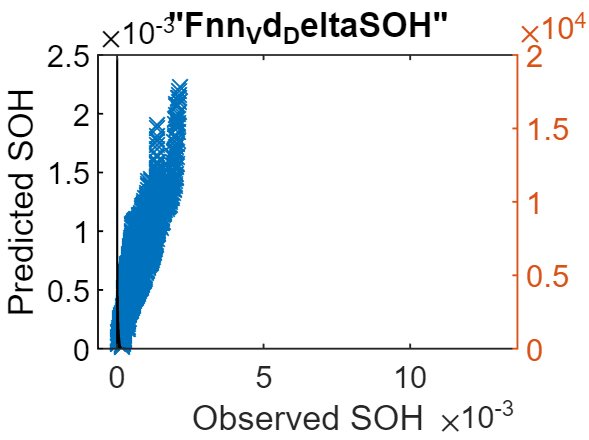

(Y_trainValid_SOH - Yfit_trainValid_SOH).^2;   % Squared Error
histogram((Y_trainValid_SOH - Yfit_trainValid_SOH).^2)

mean((Y_trainValid_SOH - Yfit_trainValid_SOH).^2);   % Mean Squared Error
RMSE_trainValid_IcSOH = sqrt(mean((Y_trainValid_SOH - Yfit_trainValid_SOH).^2))  % Root Mean Squared Error

RMSE_trainValid_IcSOH = 0.0046

Y_trainValid_diff_IcSOH = horzcat(Y_trainValid_SOH,(Y_trainValid_SOH-Yfit_trainValid_SOH))

Y_trainValid_diff_IcSOH = 38367×2
    1.0479    0.0044
    1.0478    0.0077
    1.0477    0.0074
    1.0476    0.0056
    1.0475    0.0053
    1.0474    0.0079
    1.0473    0.0051
    1.0472    0.0077
    1.0471    0.0048
    1.0470    0.0049


Y_trainValid_diff_percentage_IcSOH = abs(Y_trainValid_SOH-Yfit_trainValid_SOH)./Y_trainValid_SOH.*100

Y_trainValid_diff_percentage_IcSOH = 38367×1
    0.4195
    0.7340
    0.7092
    0.5362
    0.5063
    0.7495
    0.4849
    0.7361
    0.4628
    0.4707


Y_trainValid_diff_percentage_avg_IcSOH = sum(Y_trainValid_diff_percentage_IcSOH)/length(Y_trainValid_diff_percentage_IcSOH)

Y_trainValid_diff_percentage_avg_IcSOH = 0.3685

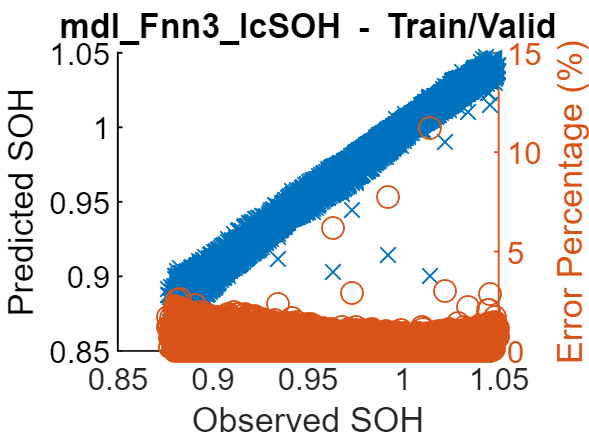

figure
hold on
plot(Y_trainValid_SOH,Yfit_trainValid_SOH,'x')
xlabel("Observed SOH")
ylabel("Predicted SOH")
%xlim([0 1.2]), ylim([0 1.2])

yyaxis right
ylabel('Error Percentage (%)')
plot(Y_trainValid_SOH,Y_trainValid_diff_percentage_IcSOH,'o');

hold off
title 'mdl\_Fnn3\_IcSOH - Train/Valid'


%%%%%%%%%%%%
RMSE_test_IcSOH = sqrt(mean((Y_test_SOH - Yfit_test_SOH).^2))

RMSE_test_IcSOH = 0.0047

Y_test_SOH - Yfit_test_SOH

ans = 4488×1
    0.0092
    0.0096
    0.0094
    0.0095
    0.0095
    0.0097
    0.0096
    0.0096
    0.0097
    0.0097


Y_test_diff_IcSOH = horzcat(Y_test_SOH,(Y_test_SOH-Yfit_test_SOH))

Y_test_diff_IcSOH = 4488×2
    1.0477    0.0092
    1.0476    0.0096
    1.0474    0.0094
    1.0473    0.0095
    1.0471    0.0095
    1.0470    0.0097
    1.0468    0.0096
    1.0467    0.0096
    1.0465    0.0097
    1.0464    0.0097


Y_test_diff_percentage_IcSOH = abs(Y_test_SOH-Yfit_test_SOH)./Y_test_SOH.*100

Y_test_diff_percentage_IcSOH = 4488×1
    0.8810
    0.9120
    0.8996
    0.9107
    0.9085
    0.9256
    0.9181
    0.9171
    0.9279
    0.9290


Y_test_diff_percentage_avg_IcSOH = sum(Y_test_diff_percentage_IcSOH)/length(Y_test_diff_percentage_IcSOH)

Y_test_diff_percentage_avg_IcSOH = 0.3904

num = 1:length(Y_test_SOH);


result = horzcat(num',Y_test_SOH,(Y_test_SOH-Yfit_test_SOH),Y_test_diff_percentage_IcSOH);
result % 배터리 번호 / SOH 관찰값 / 오차 / 오차 퍼센티지 

result = 4488×4
    1.0000    1.0477    0.0092    0.8810
    2.0000    1.0476    0.0096    0.9120
    3.0000    1.0474    0.0094    0.8996
    4.0000    1.0473    0.0095    0.9107
    5.0000    1.0471    0.0095    0.9085
    6.0000    1.0470    0.0097    0.9256
    7.0000    1.0468    0.0096    0.9181
    8.0000    1.0467    0.0096    0.9171
    9.0000    1.0465    0.0097    0.9279
   10.0000    1.0464    0.0097    0.9290


result_mdl_Fnn3_IcSOH = table(num',Y_test_SOH,(Y_test_SOH-Yfit_test_SOH),Y_test_diff_percentage_IcSOH);
result_mdl_Fnn3_IcSOH.Properties.VariableNames = {'bat num','SOH','오차','오차비율'};
result_mdl_Fnn3_IcSOH

result_mdl_Fnn3_IcSOH = 4488×4 table
    bat num     SOH        오차       오차비율
    _______    ______    _________    _______

       1       1.0477    0.0092305    0.88101
       2       1.0476    0.0095543    0.91205
       3       1.0474    0.0094222    0.89957
       4       1.0473    0.0095376    0.91071
       5       1.0471    0.0095129    0.90849
       6        1.047    0.0096908     0.9256
       7       1.0468    0.0096106    0.91808
       8       1.0467    0.0095988    0.91709
       9       1.0465    0.0097111    0.92795
      10       1.0464    0.0097211    0.92905
      11       1.0462    0.0097213     0.9292
      12        1.046     0.009946    0.95082
      13       1.0459    0.0099665    0.95293
      14       1.0457    0.0098426    0.94122
      15       1.0456    0.0096696    0.92482
      16       1.0454    0.0097056     0.9284


result_mdl_Fnn3_IcSOH_summary = table(RMSE_test_IcSOH,Y_test_diff_percentage_avg_IcSOH);
result_mdl_Fnn3_IcSOH_summary.Properties.VariableNames = {'RMSE','평균오차비율'};
result_mdl_Fnn3_IcSOH_summary 

result_mdl_Fnn3_IcSOH_summary = 1×2 table
      RMSE       평균오차비율
    _________    __________

    0.0047151     0.39039  




RMSE_test_IcSOH

RMSE_test_IcSOH = 0.0047

Y_test_diff_percentage_avg_IcSOH

Y_test_diff_percentage_avg_IcSOH = 0.3904

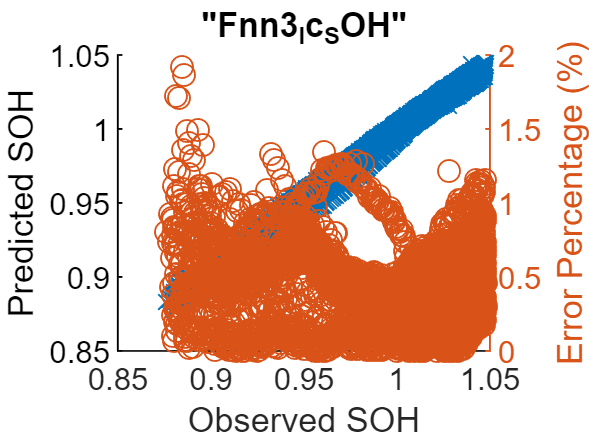


figure
hold on
plot(Y_test_SOH,Yfit_test_SOH,'x')
xlabel("Observed SOH")
ylabel("Predicted SOH")
%xlim([0 1.2]), ylim([0 1.2])

yyaxis right
ylabel('Error Percentage (%)')
plot(Y_test_SOH,Y_test_diff_percentage_IcSOH,'o');

hold off
%title 'mdl\_Fnn3\_IcSOH - Test'
title "Fnn3_Ic_SOH"

# Fnn3 Vd_SOH

yfit_trainValid_SOH = mdl_Fnn3_VdSOH(xnorm_Vd([idxTrainAll idxValidAll ], :)')';
yfit_trainValid_SOH'

ans = 1×38367
    0.9607    0.9616    0.9590    0.9576    0.9610    0.9608    0.9588    0.9582    0.9570    0.9580    0.9586    0.9597    0.9585    0.9604    0.9580    0.9581    0.9596    0.9581    0.9582    0.9574    0.9588    0.9581    0.9555    0.9570    0.9580    0.9561    0.9572    0.9560    0.9566    0.9558


yfit_test_SOH = mdl_Fnn3_VdSOH(xnorm_Vd( idxTestAll, :)')';
yfit_test_SOH'

ans = 1×4488
    0.9374    0.9375    0.9364    0.9331    0.9315    0.9326    0.9319    0.9344    0.9322    0.9313    0.9328    0.9276    0.9277    0.9299    0.9297    0.9235    0.9239    0.9225    0.9201    0.9197    0.9241    0.9208    0.9255    0.9216    0.9250    0.9198    0.9177    0.9171    0.9175    0.9138



y_trainValid_SOH'

ans = 1×38367
    0.9878    0.9872    0.9867    0.9861    0.9855    0.9849    0.9843    0.9837    0.9832    0.9826    0.9820    0.9814    0.9808    0.9802    0.9796    0.9790    0.9784    0.9778    0.9772    0.9766    0.9760    0.9754    0.9748    0.9742    0.9736    0.9730    0.9724    0.9718    0.9712    0.9706


y_test_SOH'

ans = 1×4488
    0.9869    0.9861    0.9852    0.9843    0.9835    0.9826    0.9817    0.9809    0.9800    0.9791    0.9782    0.9773    0.9764    0.9755    0.9745    0.9736    0.9727    0.9717    0.9708    0.9698    0.9689    0.9679    0.9670    0.9660    0.9650    0.9641    0.9631    0.9621    0.9611    0.9601



Yfit_trainValid_SOH = yfit_trainValid_SOH * yrate_SOH + ymin_SOH;
Yfit_test_SOH = yfit_test_SOH * yrate_SOH + ymin_SOH;
%Y_test_SOH = y_test_Vd_SOH * yrate_Vd_SOH + ymin_Vd_SOH;


MAE_VdSOH = mean(abs(Yfit_trainValid_SOH-Y_trainValid_SOH))

MAE_VdSOH = 0.0069

adjMAE_VdSOH = MAE_VdSOH/range(Y_trainValid_SOH)

adjMAE_VdSOH = 0.0397

range(Y_trainValid_SOH) % Y_trainValid_SOH = range(X)는 X에 포함된 표본 데이터의 최댓값과 최솟값 간의 차이를 반환합니다.

ans = 0.1734


(Y_trainValid_SOH - Yfit_trainValid_SOH)'    % Errors

ans = 1×38367
    0.0047    0.0044    0.0048    0.0049    0.0043    0.0042    0.0044    0.0044    0.0045    0.0043    0.0041    0.0038    0.0039    0.0034    0.0038    0.0036    0.0033    0.0034    0.0033    0.0033    0.0030    0.0030    0.0034    0.0030    0.0027    0.0029    0.0026    0.0027    0.0025    0.0026


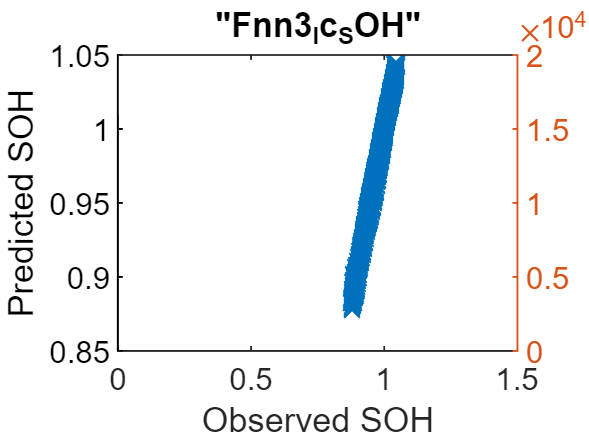

(Y_trainValid_SOH - Yfit_trainValid_SOH).^2;   % Squared Error
histogram((Y_trainValid_SOH - Yfit_trainValid_SOH).^2)

mean((Y_trainValid_SOH - Yfit_trainValid_SOH).^2);   % Mean Squared Error
RMSE_trainValid_VdSOH = sqrt(mean((Y_trainValid_SOH - Yfit_trainValid_SOH).^2))  % Root Mean Squared Error

RMSE_trainValid_VdSOH = 0.0089

Y_trainValid_diff_VdSOH = horzcat(Y_trainValid_SOH,(Y_trainValid_SOH-Yfit_trainValid_SOH))

Y_trainValid_diff_VdSOH = 38367×2
    1.0479    0.0047
    1.0478    0.0044
    1.0477    0.0048
    1.0476    0.0049
    1.0475    0.0043
    1.0474    0.0042
    1.0473    0.0044
    1.0472    0.0044
    1.0471    0.0045
    1.0470    0.0043


Y_trainValid_diff_percentage_VdSOH = abs(Y_trainValid_SOH-Yfit_trainValid_SOH)./Y_trainValid_SOH.*100

Y_trainValid_diff_percentage_VdSOH = 38367×1
    0.4492
    0.4244
    0.4591
    0.4718
    0.4063
    0.3994
    0.4238
    0.4241
    0.4344
    0.4085


Y_trainValid_diff_percentage_avg_VdSOH = sum(Y_trainValid_diff_percentage_VdSOH)/length(Y_trainValid_diff_percentage_VdSOH)

Y_trainValid_diff_percentage_avg_VdSOH = 0.6932

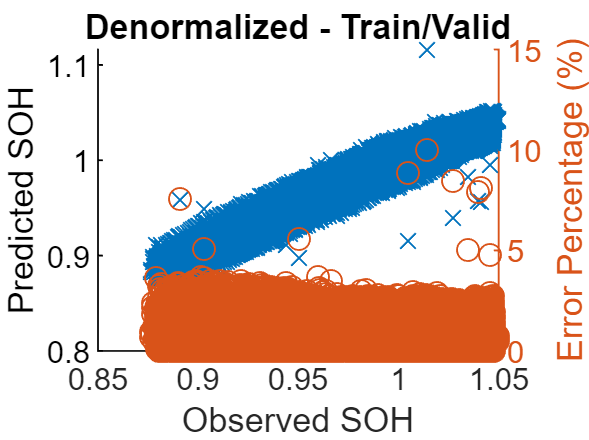

figure
hold on
plot(Y_trainValid_SOH,Yfit_trainValid_SOH,'x')
xlabel("Observed SOH")
ylabel("Predicted SOH")
%xlim([0 1.2]), ylim([0 1.2])

yyaxis right
ylabel('Error Percentage (%)')
plot(Y_trainValid_SOH,Y_trainValid_diff_percentage_VdSOH,'o');

hold off
title 'Denormalized - Train/Valid'


%%%%%%%%%%%%
RMSE_test_VdSOH = sqrt(mean((Y_test_SOH - Yfit_test_SOH).^2))

RMSE_test_VdSOH = 0.0074

Y_test_SOH - Yfit_test_SOH

ans = 4488×1
    0.0086
    0.0084
    0.0085
    0.0089
    0.0090
    0.0087
    0.0087
    0.0081
    0.0083
    0.0083


Y_test_diff_VdSOH = horzcat(Y_test_SOH,(Y_test_SOH-Yfit_test_SOH))

Y_test_diff_VdSOH = 4488×2
    1.0477    0.0086
    1.0476    0.0084
    1.0474    0.0085
    1.0473    0.0089
    1.0471    0.0090
    1.0470    0.0087
    1.0468    0.0087
    1.0467    0.0081
    1.0465    0.0083
    1.0464    0.0083


Y_test_diff_percentage_VdSOH = abs(Y_test_SOH-Yfit_test_SOH)./Y_test_SOH.*100

Y_test_diff_percentage_VdSOH = 4488×1
    0.8205
    0.8057
    0.8086
    0.8490
    0.8614
    0.8303
    0.8270
    0.7712
    0.7929
    0.7926


Y_test_diff_percentage_avg_VdSOH = sum(Y_test_diff_percentage_VdSOH)/length(Y_test_diff_percentage_VdSOH)

Y_test_diff_percentage_avg_VdSOH = 0.5745

num = 1:length(Y_test_SOH);


result = horzcat(num',Y_test_SOH,(Y_test_SOH-Yfit_test_SOH),Y_test_diff_percentage_VdSOH);
result % 배터리 번호 / SOH 관찰값 / 오차 / 오차 퍼센티지 

result = 4488×4
    1.0000    1.0477    0.0086    0.8205
    2.0000    1.0476    0.0084    0.8057
    3.0000    1.0474    0.0085    0.8086
    4.0000    1.0473    0.0089    0.8490
    5.0000    1.0471    0.0090    0.8614
    6.0000    1.0470    0.0087    0.8303
    7.0000    1.0468    0.0087    0.8270
    8.0000    1.0467    0.0081    0.7712
    9.0000    1.0465    0.0083    0.7929
   10.0000    1.0464    0.0083    0.7926


result_mdl_Fnn3_VdSOH = table(num',Y_test_SOH,(Y_test_SOH-Yfit_test_SOH),Y_test_diff_percentage_VdSOH);
result_mdl_Fnn3_VdSOH.Properties.VariableNames = {'bat num','SOH','오차','오차비율'};
result_mdl_Fnn3_VdSOH

result_mdl_Fnn3_VdSOH = 4488×4 table
    bat num     SOH        오차       오차비율
    _______    ______    _________    _______

       1       1.0477    0.0085965     0.8205
       2       1.0476    0.0084402     0.8057
       3       1.0474    0.0084689    0.80855
       4       1.0473    0.0088916    0.84903
       5       1.0471    0.0090203    0.86144
       6        1.047     0.008693     0.8303
       7       1.0468     0.008657    0.82698
       8       1.0467    0.0080718     0.7712
       9       1.0465    0.0082975    0.79287
      10       1.0464    0.0082932    0.79258
      11       1.0462    0.0078824    0.75343
      12        1.046    0.0086321    0.82521
      13       1.0459    0.0084602     0.8089
      14       1.0457     0.007914    0.75679
      15       1.0456    0.0077909    0.74514
      16       1.0454    0.0087044    0.83263


result_mdl_Fnn3_VdSOH_summary = table(RMSE_test_VdSOH,Y_test_diff_percentage_avg_VdSOH);
result_mdl_Fnn3_VdSOH_summary.Properties.VariableNames = {'RMSE','평균오차비율'};
result_mdl_Fnn3_VdSOH_summary 

result_mdl_Fnn3_VdSOH_summary = 1×2 table
      RMSE       평균오차비율
    _________    __________

    0.0074026     0.57452  




RMSE_test_VdSOH

RMSE_test_VdSOH = 0.0074

Y_test_diff_percentage_avg_VdSOH

Y_test_diff_percentage_avg_VdSOH = 0.5745

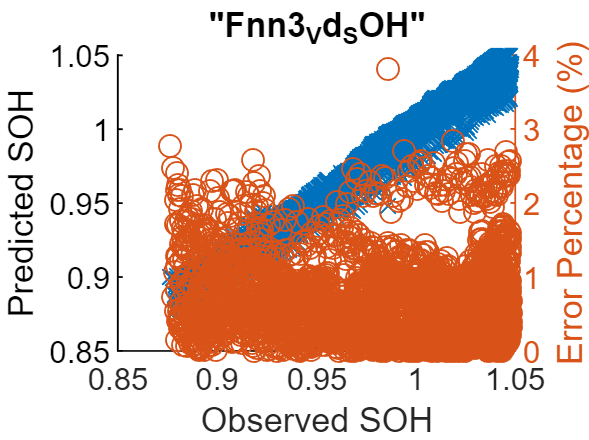


figure
hold on
plot(Y_test_SOH,Yfit_test_SOH,'x')
xlabel("Observed SOH")
ylabel("Predicted SOH")
%xlim([0 1.2]), ylim([0 1.2])

yyaxis right
ylabel('Error Percentage (%)')
plot(Y_test_SOH,Y_test_diff_percentage_VdSOH,'o');

hold off
title "Fnn3_Vd_SOH"

# Fnn3 Ic_DeltaSOH

yfit_trainValid_DeltaSOH = mdl_Fnn3_IcSOH(xnorm_Ic([idxTrainAll idxValidAll ], :)')';
yfit_trainValid_DeltaSOH'

ans = 1×38367
    0.9625    0.9430    0.9439    0.9537    0.9550    0.9397    0.9551    0.9394    0.9553    0.9542    0.9474    0.9362    0.9358    0.9505    0.9516    0.9339    0.9336    0.9503    0.9321    0.9319    0.9319    0.9329    0.9488    0.9301    0.9285    0.9279    0.9455    0.9272    0.9474    0.9266


yfit_test_DeltaSOH = mdl_Fnn3_IcSOH(xnorm_Ic( idxTestAll, :)')';
yfit_test_DeltaSOH'

ans = 1×4488
    0.9338    0.9311    0.9310    0.9294    0.9287    0.9268    0.9264    0.9256    0.9241    0.9231    0.9222    0.9200    0.9190    0.9188    0.9189    0.9177    0.9166    0.9163    0.9255    0.9244    0.9135    0.9149    0.9155    0.9261    0.9162    0.9159    0.9249    0.9137    0.9120    0.9093



y_trainValid_DeltaSOH'

ans = 1×38367
    0.0716    0.0716    0.0716    0.0715    0.0715    0.0715    0.0715    0.0716    0.0716    0.0717    0.0718    0.0719    0.0720    0.0722    0.0723    0.0725    0.0726    0.0727    0.0728    0.0729    0.0729    0.0729    0.0730    0.0730    0.0730    0.0730    0.0731    0.0731    0.0732    0.0733


y_test_DeltaSOH'

ans = 1×4488
    0.0885    0.0885    0.0885    0.0886    0.0887    0.0888    0.0890    0.0893    0.0897    0.0901    0.0905    0.0909    0.0914    0.0918    0.0923    0.0927    0.0931    0.0934    0.0937    0.0939    0.0941    0.0943    0.0944    0.0946    0.0948    0.0951    0.0954    0.0958    0.0963    0.0968



Yfit_trainValid_DeltaSOH = yfit_trainValid_DeltaSOH * yrate_DeltaSOH + ymin_DeltaSOH;
Yfit_test_DeltaSOH = yfit_test_DeltaSOH * yrate_DeltaSOH + ymin_DeltaSOH;
%Y_test_DeltaSOH = y_test_Ic_DeltaSOH * yrate_Ic_DeltaSOH + ymin_Ic_DeltaSOH;


MAE_IcDeltaSOH = mean(abs(Yfit_trainValid_DeltaSOH-Y_trainValid_DeltaSOH))

MAE_IcDeltaSOH = 0.0016

adjMAE_IcDeltaSOH = MAE_IcDeltaSOH/range(Y_trainValid_DeltaSOH)

adjMAE_IcDeltaSOH = 0.5647

range(Y_trainValid_DeltaSOH) % Y_trainValid_DeltaSOH = range(X)는 X에 포함된 표본 데이터의 최댓값과 최솟값 간의 차이를 반환합니다.

ans = 0.0029


(Y_trainValid_DeltaSOH - Yfit_trainValid_DeltaSOH)'    % Errors

ans = 1×38367
   -0.0026   -0.0025   -0.0025   -0.0025   -0.0025   -0.0025   -0.0025   -0.0025   -0.0025   -0.0025   -0.0025   -0.0025   -0.0025   -0.0025   -0.0025   -0.0025   -0.0025   -0.0025   -0.0025   -0.0025   -0.0025   -0.0025   -0.0025   -0.0025   -0.0025   -0.0025   -0.0025   -0.0025   -0.0025   -0.0025


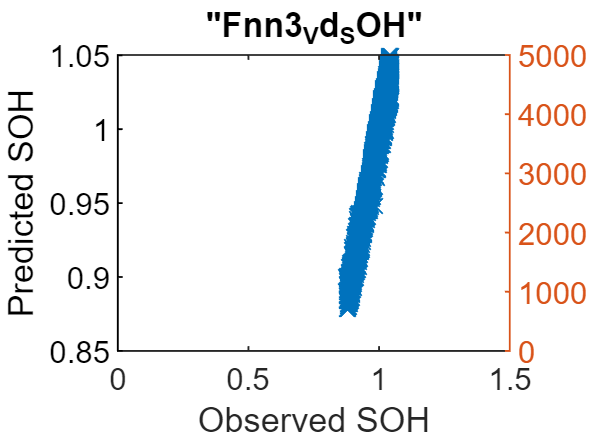

(Y_trainValid_DeltaSOH - Yfit_trainValid_DeltaSOH).^2;   % Squared Error
histogram((Y_trainValid_DeltaSOH - Yfit_trainValid_DeltaSOH).^2)

mean((Y_trainValid_DeltaSOH - Yfit_trainValid_DeltaSOH).^2);   % Mean Squared Error
RMSE_trainValid_IcDeltaSOH = sqrt(mean((Y_trainValid_DeltaSOH - Yfit_trainValid_DeltaSOH).^2))  % Root Mean Squared Error

RMSE_trainValid_IcDeltaSOH = 0.0018

Y_trainValid_diff_IcDeltaSOH = horzcat(Y_trainValid_DeltaSOH,(Y_trainValid_DeltaSOH-Yfit_trainValid_DeltaSOH))

Y_trainValid_diff_IcDeltaSOH = 38367×2
    0.0001   -0.0026
    0.0001   -0.0025
    0.0001   -0.0025
    0.0001   -0.0025
    0.0001   -0.0025
    0.0001   -0.0025
    0.0001   -0.0025
    0.0001   -0.0025
    0.0001   -0.0025
    0.0001   -0.0025


Y_trainValid_diff_percentage_IcDeltaSOH = abs(Y_trainValid_DeltaSOH-Yfit_trainValid_DeltaSOH)./Y_trainValid_DeltaSOH.*100

Y_trainValid_diff_percentage_IcDeltaSOH = 38367×1
1.0e+05 *

    0.0253
    0.0248
    0.0248
    0.0251
    0.0252
    0.0247
    0.0252
    0.0247
    0.0251
    0.0250


Y_trainValid_diff_percentage_avg_IcDeltaSOH = sum(Y_trainValid_diff_percentage_IcDeltaSOH)/length(Y_trainValid_diff_percentage_IcDeltaSOH)

Y_trainValid_diff_percentage_avg_IcDeltaSOH = 1.2813e+03

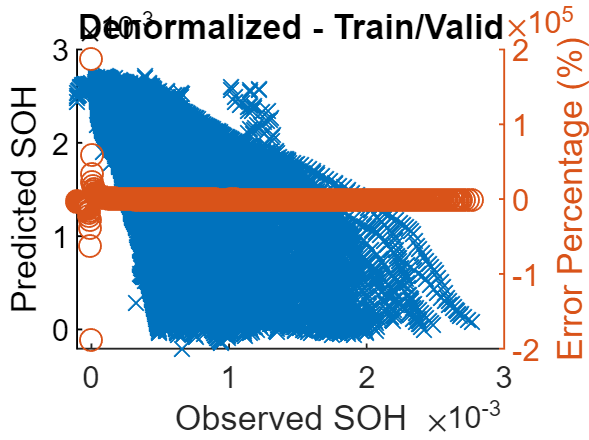

figure
hold on
plot(Y_trainValid_DeltaSOH,Yfit_trainValid_DeltaSOH,'x')
xlabel("Observed SOH")
ylabel("Predicted SOH")
%xlim([0 1.2]), ylim([0 1.2])

yyaxis right
ylabel('Error Percentage (%)')
plot(Y_trainValid_DeltaSOH,Y_trainValid_diff_percentage_IcDeltaSOH,'o');

hold off
title 'Denormalized - Train/Valid'


%%%%%%%%%%%%
RMSE_test_IcDeltaSOH = sqrt(mean((Y_test_DeltaSOH - Yfit_test_DeltaSOH).^2))

RMSE_test_IcDeltaSOH = 0.0018

Y_test_DeltaSOH - Yfit_test_DeltaSOH

ans = 4488×1
   -0.0024
   -0.0024
   -0.0024
   -0.0024
   -0.0024
   -0.0024
   -0.0024
   -0.0024
   -0.0024
   -0.0024


Y_test_diff_IcDeltaSOH = horzcat(Y_test_DeltaSOH,(Y_test_DeltaSOH-Yfit_test_DeltaSOH))

Y_test_diff_IcDeltaSOH = 4488×2
    0.0001   -0.0024
    0.0001   -0.0024
    0.0001   -0.0024
    0.0001   -0.0024
    0.0002   -0.0024
    0.0002   -0.0024
    0.0002   -0.0024
    0.0002   -0.0024
    0.0002   -0.0024
    0.0002   -0.0024


Y_test_diff_percentage_IcDeltaSOH = abs(Y_test_DeltaSOH-Yfit_test_DeltaSOH)./Y_test_DeltaSOH.*100

Y_test_diff_percentage_IcDeltaSOH = 4488×1
1.0e+03 *

    1.6239
    1.6186
    1.6180
    1.6133
    1.6086
    1.5998
    1.5917
    1.5809
    1.5672
    1.5535


Y_test_diff_percentage_avg_IcDeltaSOH = sum(Y_test_diff_percentage_IcDeltaSOH)/length(Y_test_diff_percentage_IcDeltaSOH)

Y_test_diff_percentage_avg_IcDeltaSOH = 1.2225e+03

num = 1:length(Y_test_DeltaSOH);


result = horzcat(num',Y_test_DeltaSOH,(Y_test_DeltaSOH-Yfit_test_DeltaSOH),Y_test_diff_percentage_IcDeltaSOH);
result % 배터리 번호 / DeltaSOH 관찰값 / 오차 / 오차 퍼센티지 

result = 4488×4
1.0e+03 *

    0.0010    0.0000   -0.0000    1.6239
    0.0020    0.0000   -0.0000    1.6186
    0.0030    0.0000   -0.0000    1.6180
    0.0040    0.0000   -0.0000    1.6133
    0.0050    0.0000   -0.0000    1.6086
    0.0060    0.0000   -0.0000    1.5998
    0.0070    0.0000   -0.0000    1.5917
    0.0080    0.0000   -0.0000    1.5809
    0.0090    0.0000   -0.0000    1.5672
    0.0100    0.0000   -0.0000    1.5535


result_mdl_Fnn3_IcDeltaSOH = table(num',Y_test_DeltaSOH,(Y_test_DeltaSOH-Yfit_test_DeltaSOH),Y_test_diff_percentage_IcDeltaSOH);
result_mdl_Fnn3_IcDeltaSOH.Properties.VariableNames = {'bat num','DeltaSOH','오차','오차비율'};
result_mdl_Fnn3_IcDeltaSOH

result_mdl_Fnn3_IcDeltaSOH = 4488×4 table
    bat num     DeltaSOH        오차       오차비율
    _______    __________    __________    _______

       1       0.00014965    -0.0024301    1623.9 
       2       0.00014965    -0.0024222    1618.6 
       3       0.00014968    -0.0024219      1618 
       4       0.00014984    -0.0024173    1613.3 
       5       0.00015013     -0.002415    1608.6 
       6       0.00015059    -0.0024091    1599.8 
       7       0.00015124    -0.0024073    1591.7 
       8       0.00015207    -0.0024041    1580.9 
       9       0.00015306    -0.0023987    1567.2 
      10       0.00015416    -0.0023949    1553.5 
      11       0.00015536    -0.0023911    1539.1 
      12       0.00015666    -0.0023835    1521.5 
      13         0.000158    -0.0023792    1505.9 
      14       0.00015932    -0.0023773    1492.1 
      15  

result_mdl_Fnn3_IcDeltaSOH_summary = table(RMSE_test_IcDeltaSOH,Y_test_diff_percentage_avg_IcDeltaSOH);
result_mdl_Fnn3_IcDeltaSOH_summary.Properties.VariableNames = {'RMSE','평균오차비율'};
result_mdl_Fnn3_IcDeltaSOH_summary 

result_mdl_Fnn3_IcDeltaSOH_summary = 1×2 table
      RMSE       평균오차비율
    _________    __________

    0.0017884      1222.5  




RMSE_test_IcDeltaSOH

RMSE_test_IcDeltaSOH = 0.0018

Y_test_diff_percentage_avg_IcDeltaSOH

Y_test_diff_percentage_avg_IcDeltaSOH = 1.2225e+03


figure
hold on
plot(Y_test_DeltaSOH,Yfit_test_DeltaSOH,'x')
xlabel("Observed SOH")
ylabel("Predicted SOH")
%xlim([0 1.2]), ylim([0 1.2])

yyaxis right
ylabel('Error Percentage (%)')
plot(Y_test_DeltaSOH,Y_test_diff_percentage_IcDeltaSOH,'o');

hold off
title "Fnn3_Ic_DeltaSOH"


# Fnn3 Vd_DeltaSOH

yfit_trainValid_DeltaSOH = mdl_Fnn3_VdDeltaSOH(xnorm_Vd([idxTrainAll idxValidAll ], :)')';
yfit_trainValid_DeltaSOH'

ans = 1×38367
    0.0786    0.0796    0.0798    0.0790    0.0784    0.0785    0.0797    0.0804    0.0794    0.0798    0.0803    0.0795    0.0791    0.0802    0.0800    0.0792    0.0806    0.0805    0.0806    0.0785    0.0772    0.0764    0.0770    0.0773    0.0788    0.0811    0.0808    0.0804    0.0806    0.0804


yfit_test_DeltaSOH = mdl_Fnn3_VdDeltaSOH(xnorm_Vd( idxTestAll, :)')';
yfit_test_DeltaSOH'

ans = 1×4488
    0.0722    0.0742    0.0743    0.0745    0.0752    0.0753    0.0756    0.0763    0.0760    0.0762    0.0762    0.0764    0.0772    0.0758    0.0750    0.0780    0.0778    0.0791    0.0793    0.0800    0.0773    0.0732    0.0707    0.0681    0.0680    0.0675    0.0672    0.0678    0.0715    0.0784



y_trainValid_DeltaSOH'

ans = 1×38367
    0.0716    0.0716    0.0716    0.0715    0.0715    0.0715    0.0715    0.0716    0.0716    0.0717    0.0718    0.0719    0.0720    0.0722    0.0723    0.0725    0.0726    0.0727    0.0728    0.0729    0.0729    0.0729    0.0730    0.0730    0.0730    0.0730    0.0731    0.0731    0.0732    0.0733


y_test_DeltaSOH'

ans = 1×4488
    0.0885    0.0885    0.0885    0.0886    0.0887    0.0888    0.0890    0.0893    0.0897    0.0901    0.0905    0.0909    0.0914    0.0918    0.0923    0.0927    0.0931    0.0934    0.0937    0.0939    0.0941    0.0943    0.0944    0.0946    0.0948    0.0951    0.0954    0.0958    0.0963    0.0968



Yfit_trainValid_DeltaSOH = yfit_trainValid_DeltaSOH * yrate_DeltaSOH + ymin_DeltaSOH;
Yfit_test_DeltaSOH = yfit_test_DeltaSOH * yrate_DeltaSOH + ymin_DeltaSOH;
%Y_test_DeltaSOH = y_test_Vd_DeltaSOH * yrate_Vd_DeltaSOH + ymin_Vd_DeltaSOH;


MAE_VdDeltaSOH = mean(abs(Yfit_trainValid_DeltaSOH-Y_trainValid_DeltaSOH))

MAE_VdDeltaSOH = 1.0158e-04

adjMAE_VdDeltaSOH = MAE_VdDeltaSOH/range(Y_trainValid_DeltaSOH)

adjMAE_VdDeltaSOH = 0.0353

range(Y_trainValid_DeltaSOH) % Y_trainValid_DeltaSOH = range(X)는 X에 포함된 표본 데이터의 최댓값과 최솟값 간의 차이를 반환합니다.

ans = 0.0029


(Y_trainValid_DeltaSOH - Yfit_trainValid_DeltaSOH)'    % Errors

ans = 1×38367
1.0e-03 *

   -0.0203   -0.0230   -0.0237   -0.0215   -0.0198   -0.0201   -0.0235   -0.0254   -0.0224   -0.0232   -0.0246   -0.0218   -0.0204   -0.0230   -0.0222   -0.0192   -0.0228   -0.0224   -0.0223   -0.0162   -0.0124   -0.0101   -0.0117   -0.0124   -0.0168   -0.0231   -0.0223   -0.0210   -0.0213   -0.0205


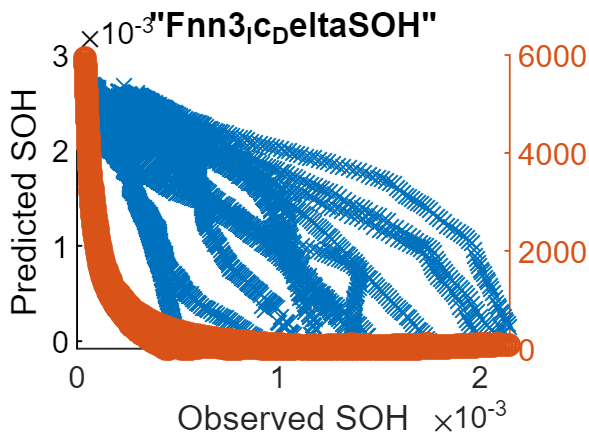

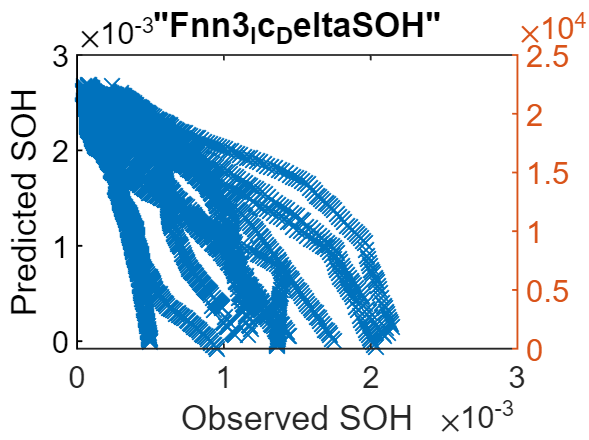

(Y_trainValid_DeltaSOH - Yfit_trainValid_DeltaSOH).^2;   % Squared Error
histogram((Y_trainValid_DeltaSOH - Yfit_trainValid_DeltaSOH).^2)

mean((Y_trainValid_DeltaSOH - Yfit_trainValid_DeltaSOH).^2);   % Mean Squared Error
RMSE_trainValid_VdDeltaSOH = sqrt(mean((Y_trainValid_DeltaSOH - Yfit_trainValid_DeltaSOH).^2))  % Root Mean Squared Error

RMSE_trainValid_VdDeltaSOH = 1.5819e-04

Y_trainValid_diff_VdDeltaSOH = horzcat(Y_trainValid_DeltaSOH,(Y_trainValid_DeltaSOH-Yfit_trainValid_DeltaSOH))

Y_trainValid_diff_VdDeltaSOH = 38367×2
1.0e+00 *

    0.0001   -0.0000
    0.0001   -0.0000
    0.0001   -0.0000
    0.0001   -0.0000
    0.0001   -0.0000
    0.0001   -0.0000
    0.0001   -0.0000
    0.0001   -0.0000
    0.0001   -0.0000
    0.0001   -0.0000


Y_trainValid_diff_percentage_VdDeltaSOH = abs(Y_trainValid_DeltaSOH-Yfit_trainValid_DeltaSOH)./Y_trainValid_DeltaSOH.*100

Y_trainValid_diff_percentage_VdDeltaSOH = 38367×1
   20.0458
   22.7304
   23.4567
   21.3145
   19.6629
   19.8891
   23.3258
   25.1582
   22.1923
   22.9331


Y_trainValid_diff_percentage_avg_VdDeltaSOH = sum(Y_trainValid_diff_percentage_VdDeltaSOH)/length(Y_trainValid_diff_percentage_VdDeltaSOH)

Y_trainValid_diff_percentage_avg_VdDeltaSOH = 29.2204

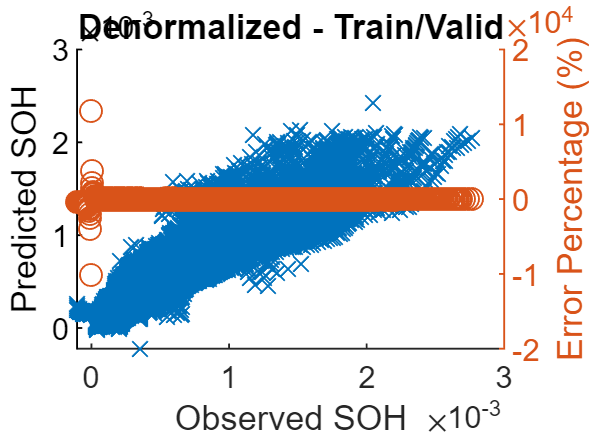

figure
hold on
plot(Y_trainValid_DeltaSOH,Yfit_trainValid_DeltaSOH,'x')
xlabel("Observed SOH")
ylabel("Predicted SOH")
%xlim([0 1.2]), ylim([0 1.2])

yyaxis right
ylabel('Error Percentage (%)')
plot(Y_trainValid_DeltaSOH,Y_trainValid_diff_percentage_VdDeltaSOH,'o');

hold off
title 'Denormalized - Train/Valid'


%%%%%%%%%%%%
RMSE_test_VdDeltaSOH = sqrt(mean((Y_test_DeltaSOH - Yfit_test_DeltaSOH).^2))

RMSE_test_VdDeltaSOH = 1.6150e-04

Y_test_DeltaSOH - Yfit_test_DeltaSOH

ans = 4488×1
1.0e-03 *

    0.0467
    0.0411
    0.0409
    0.0403
    0.0388
    0.0389
    0.0386
    0.0375
    0.0392
    0.0397


Y_test_diff_VdDeltaSOH = horzcat(Y_test_DeltaSOH,(Y_test_DeltaSOH-Yfit_test_DeltaSOH))

Y_test_diff_VdDeltaSOH = 4488×2
1.0e+00 *

    0.0001    0.0000
    0.0001    0.0000
    0.0001    0.0000
    0.0001    0.0000
    0.0002    0.0000
    0.0002    0.0000
    0.0002    0.0000
    0.0002    0.0000
    0.0002    0.0000
    0.0002    0.0000


Y_test_diff_percentage_VdDeltaSOH = abs(Y_test_DeltaSOH-Yfit_test_DeltaSOH)./Y_test_DeltaSOH.*100

Y_test_diff_percentage_VdDeltaSOH = 4488×1
   31.2269
   27.4757
   27.3271
   26.8985
   25.8254
   25.8567
   25.5274
   24.6840
   25.5904
   25.7837


Y_test_diff_percentage_avg_VdDeltaSOH = sum(Y_test_diff_percentage_VdDeltaSOH)/length(Y_test_diff_percentage_VdDeltaSOH)

Y_test_diff_percentage_avg_VdDeltaSOH = 27.6745

num = 1:length(Y_test_DeltaSOH);


result = horzcat(num',Y_test_DeltaSOH,(Y_test_DeltaSOH-Yfit_test_DeltaSOH),Y_test_diff_percentage_VdDeltaSOH);
result % 배터리 번호 / DeltaSOH 관찰값 / 오차 / 오차 퍼센티지 

result = 4488×4
    1.0000    0.0001    0.0000   31.2269
    2.0000    0.0001    0.0000   27.4757
    3.0000    0.0001    0.0000   27.3271
    4.0000    0.0001    0.0000   26.8985
    5.0000    0.0002    0.0000   25.8254
    6.0000    0.0002    0.0000   25.8567
    7.0000    0.0002    0.0000   25.5274
    8.0000    0.0002    0.0000   24.6840
    9.0000    0.0002    0.0000   25.5904
   10.0000    0.0002    0.0000   25.7837


result_mdl_Fnn3_VdDeltaSOH = table(num',Y_test_DeltaSOH,(Y_test_DeltaSOH-Yfit_test_DeltaSOH),Y_test_diff_percentage_VdDeltaSOH);
result_mdl_Fnn3_VdDeltaSOH.Properties.VariableNames = {'bat num','DeltaSOH','오차','오차비율'};
result_mdl_Fnn3_VdDeltaSOH

result_mdl_Fnn3_VdDeltaSOH = 4488×4 table
    bat num     DeltaSOH        오차       오차비율
    _______    __________    __________    _______

       1       0.00014965     4.673e-05    31.227 
       2       0.00014965    4.1116e-05    27.476 
       3       0.00014968    4.0904e-05    27.327 
       4       0.00014984    4.0305e-05    26.899 
       5       0.00015013    3.8773e-05    25.825 
       6       0.00015059    3.8937e-05    25.857 
       7       0.00015124    3.8607e-05    25.527 
       8       0.00015207    3.7537e-05    24.684 
       9       0.00015306    3.9168e-05     25.59 
      10       0.00015416    3.9748e-05    25.784 
      11       0.00015536    4.1051e-05    26.423 
      12       0.00015666    4.1713e-05    26.627 
      13         0.000158    4.0909e-05    25.892 
      14       0.00015932    4.6177e-05    28.983 
      15  

result_mdl_Fnn3_VdDeltaSOH_summary = table(RMSE_test_VdDeltaSOH,Y_test_diff_percentage_avg_VdDeltaSOH);
result_mdl_Fnn3_VdDeltaSOH_summary.Properties.VariableNames = {'RMSE','평균오차비율'};
result_mdl_Fnn3_VdDeltaSOH_summary 

result_mdl_Fnn3_VdDeltaSOH_summary = 1×2 table
      RMSE       평균오차비율
    _________    __________

    0.0001615      27.675  




RMSE_test_VdDeltaSOH

RMSE_test_VdDeltaSOH = 1.6150e-04

Y_test_diff_percentage_avg_VdDeltaSOH

Y_test_diff_percentage_avg_VdDeltaSOH = 27.6745

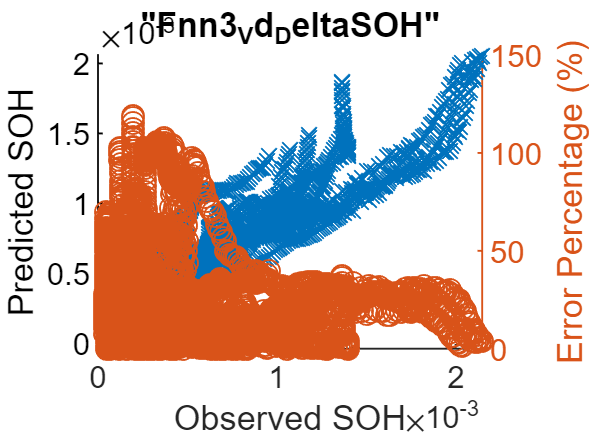


figure
hold on
plot(Y_test_DeltaSOH,Yfit_test_DeltaSOH,'x')
xlabel("Observed SOH")
ylabel("Predicted SOH")
%xlim([0 1.2]), ylim([0 1.2])

yyaxis right
ylabel('Error Percentage (%)')
plot(Y_test_DeltaSOH,Y_test_diff_percentage_VdDeltaSOH,'o');

hold off
title "Fnn3_Vd_DeltaSOH"

# 실험결과 

result_mdl_Linear_IcSOH

result_mdl_Linear_IcSOH = 4488×4 table
    bat num     SOH         오차        오차비율 
    _______    ______    ___________    ________

       1       1.0477     -0.0017427     0.16633
       2       1.0476      -0.001427     0.13622
       3       1.0474     -0.0015774      0.1506
       4       1.0473     -0.0014289     0.13644
       5       1.0471     -0.0014343     0.13697
       6        1.047     -0.0012436     0.11878
       7       1.0468     -0.0013339     0.12742
       8       1.0467     -0.0013058     0.12475
       9       1.0465     -0.0012203      0.1166
      10       1.0464       -0.00121     0.11564
      11       1.0462     -0.0012219     0.11679
      12        1.046    -0.00096732    0.092474
      13       1.0459    -0.00095181    0.091005
      14       1.0457     -0.0010458     0.10001
      15       1.0456     -0.0012275      0.1

result_mdl_Linear_VdSOH

result_mdl_Linear_VdSOH = 4488×4 table
    bat num     SOH        오차       오차비율
    _______    ______    _________    _______

       1       1.0477    0.0093326    0.89075
       2       1.0476    0.0097638    0.93204
       3       1.0474     0.010233    0.97696
       4       1.0473    0.0099388    0.94902
       5       1.0471    0.0097565    0.93175
       6        1.047     0.010161    0.97048
       7       1.0468    0.0088408    0.84454
       8       1.0467    0.0092065     0.8796
       9       1.0465    0.0091728    0.87652
      10       1.0464    0.0094658    0.90464
      11       1.0462    0.0076129    0.72767
      12        1.046     0.010251    0.98001
      13       1.0459    0.0090934    0.86944
      14       1.0457    0.0082982    0.79354
      15       1.0456    0.0087306    0.83501
      16       1.0454     0.010109    0.96698


result_mdl_Fnn_IcSOH

result_mdl_Fnn_IcSOH = 4488×4 table
    bat num     SOH        오차       오차비율
    _______    ______    _________    _______

       1       1.0477      0.00113    0.10786
       2       1.0476    0.0013818     0.1319
       3       1.0474    0.0012469    0.11904
       4       1.0473    0.0013331    0.12729
       5       1.0471    0.0013005     0.1242
       6        1.047    0.0014179    0.13543
       7       1.0468    0.0013311    0.12716
       8       1.0467    0.0013109    0.12524
       9       1.0465    0.0013772     0.1316
      10       1.0464     0.001356    0.12959
      11       1.0462    0.0013251    0.12665
      12        1.046    0.0015058    0.14395
      13       1.0459     0.001496    0.14304
      14       1.0457    0.0013806    0.13202
      15       1.0456     0.001194     0.1142
      16       1.0454    0.0012127    0.11601


result_mdl_Fnn_VdSOH

result_mdl_Fnn_VdSOH = 4488×4 table
    bat num     SOH        오차       오차비율
    _______    ______    _________    _______

       1       1.0477    0.0075435       0.72
       2       1.0476    0.0072594    0.69298
       3       1.0474    0.0071773    0.68524
       4       1.0473    0.0075529     0.7212
       5       1.0471    0.0077571     0.7408
       6        1.047    0.0074261     0.7093
       7       1.0468    0.0072188    0.68959
       8       1.0467    0.0067985    0.64954
       9       1.0465    0.0069702    0.66605
      10       1.0464    0.0070478    0.67356
      11       1.0462    0.0065872    0.62963
      12        1.046    0.0073948    0.70693
      13       1.0459    0.0071781    0.68632
      14       1.0457    0.0067542    0.64589
      15       1.0456    0.0066289      0.634
      16       1.0454    0.0075303    0.72032


result_mdl_Fnn3_IcSOH

result_mdl_Fnn3_IcSOH = 4488×4 table
    bat num     SOH        오차       오차비율
    _______    ______    _________    _______

       1       1.0477    0.0092305    0.88101
       2       1.0476    0.0095543    0.91205
       3       1.0474    0.0094222    0.89957
       4       1.0473    0.0095376    0.91071
       5       1.0471    0.0095129    0.90849
       6        1.047    0.0096908     0.9256
       7       1.0468    0.0096106    0.91808
       8       1.0467    0.0095988    0.91709
       9       1.0465    0.0097111    0.92795
      10       1.0464    0.0097211    0.92905
      11       1.0462    0.0097213     0.9292
      12        1.046     0.009946    0.95082
      13       1.0459    0.0099665    0.95293
      14       1.0457    0.0098426    0.94122
      15       1.0456    0.0096696    0.92482
      16       1.0454    0.0097056     0.9284


result_mdl_Fnn3_VdSOH

result_mdl_Fnn3_VdSOH = 4488×4 table
    bat num     SOH        오차       오차비율
    _______    ______    _________    _______

       1       1.0477    0.0085965     0.8205
       2       1.0476    0.0084402     0.8057
       3       1.0474    0.0084689    0.80855
       4       1.0473    0.0088916    0.84903
       5       1.0471    0.0090203    0.86144
       6        1.047     0.008693     0.8303
       7       1.0468     0.008657    0.82698
       8       1.0467    0.0080718     0.7712
       9       1.0465    0.0082975    0.79287
      10       1.0464    0.0082932    0.79258
      11       1.0462    0.0078824    0.75343
      12        1.046    0.0086321    0.82521
      13       1.0459    0.0084602     0.8089
      14       1.0457     0.007914    0.75679
      15       1.0456    0.0077909    0.74514
      16       1.0454    0.0087044    0.83263



result_mdl_Linear_IcSOH_summary

result_mdl_Linear_IcSOH_summary = 1×2 table
      RMSE      평균오차비율
    ________    __________

    0.006005     0.44441  


result_mdl_Linear_VdSOH_summary

result_mdl_Linear_VdSOH_summary = 1×2 table
      RMSE      평균오차비율
    ________    __________

    0.010161     0.77366  


result_mdl_Fnn_IcSOH_summary

result_mdl_Fnn_IcSOH_summary = 1×2 table
      RMSE       평균오차비율
    _________    __________

    0.0021202     0.16718  


result_mdl_Fnn_VdSOH_summary

result_mdl_Fnn_VdSOH_summary = 1×2 table
      RMSE       평균오차비율
    _________    __________

    0.0093153     0.71364  


result_mdl_Fnn3_IcSOH_summary

result_mdl_Fnn3_IcSOH_summary = 1×2 table
      RMSE       평균오차비율
    _________    __________

    0.0047151     0.39039  


result_mdl_Fnn3_VdSOH_summary

result_mdl_Fnn3_VdSOH_summary = 1×2 table
      RMSE       평균오차비율
    _________    __________

    0.0074026     0.57452  


result_mdl_Linear_IcDeltaSOH

result_mdl_Linear_IcDeltaSOH = 4488×4 table
    bat num     DeltaSOH        오차        오차비율
    _______    __________    ___________    _______

       1       0.00014965    -0.00016219    108.38 
       2       0.00014965    -0.00016367    109.37 
       3       0.00014968    -0.00016391    109.51 
       4       0.00014984    -0.00016426    109.63 
       5       0.00015013    -0.00016444    109.53 
       6       0.00015059    -0.00016486    109.48 
       7       0.00015124    -0.00016445    108.74 
       8       0.00015207    -0.00016386    107.75 
       9       0.00015306     -0.0001638    107.02 
      10       0.00015416    -0.00016321    105.87 
      11       0.00015536    -0.00016245    104.56 
      12       0.00015666    -0.00016219    103.53 
      13         0.000158    -0.00016138    102.14 
      14       0.00015932    -0.00016005    

result_mdl_Linear_VdDeltaSOH

result_mdl_Linear_VdDeltaSOH = 4488×4 table
    bat num     DeltaSOH        오차       오차비율
    _______    __________    __________    _______

       1       0.00014965    4.1917e-05    28.011 
       2       0.00014965    6.3629e-05     42.52 
       3       0.00014968    5.6566e-05    37.791 
       4       0.00014984    2.0018e-05    13.359 
       5       0.00015013    2.3766e-05     15.83 
       6       0.00015059    5.0417e-05     33.48 
       7       0.00015124    2.3898e-05    15.801 
       8       0.00015207    5.4046e-05     35.54 
       9       0.00015306    4.4323e-05    28.959 
      10       0.00015416    2.7604e-05    17.906 
      11       0.00015536    2.3432e-05    15.082 
      12       0.00015666    4.7347e-05    30.223 
      13         0.000158    3.5107e-05     22.22 
      14       0.00015932    2.8998e-05    18.201 
      15

result_mdl_Fnn_IcDeltaSOH

result_mdl_Fnn_IcDeltaSOH = 4488×4 table
    bat num     DeltaSOH        오차        오차비율
    _______    __________    ___________    _______

       1       0.00014965    -1.4723e-05    9.8388 
       2       0.00014965    -2.0931e-05    13.987 
       3       0.00014968    -2.0967e-05    14.008 
       4       0.00014984    -2.4536e-05    16.375 
       5       0.00015013    -2.6216e-05    17.462 
       6       0.00015059    -2.9999e-05    19.922 
       7       0.00015124    -3.0129e-05    19.922 
       8       0.00015207    -3.1667e-05    20.824 
       9       0.00015306    -3.3991e-05    22.208 
      10       0.00015416    -3.4897e-05    22.637 
      11       0.00015536    -3.5491e-05    22.844 
      12       0.00015666    -3.9569e-05    25.258 
      13         0.000158    -4.0358e-05    25.543 
      14       0.00015932    -3.9843e-05    25.

result_mdl_Fnn_VdDeltaSOH

result_mdl_Fnn_VdDeltaSOH = 4488×4 table
    bat num     DeltaSOH        오차        오차비율
    _______    __________    ___________    _______

       1       0.00014965     -5.827e-06     3.8938
       2       0.00014965    -9.6077e-06     6.4203
       3       0.00014968    -1.1105e-05     7.4189
       4       0.00014984    -1.1815e-05     7.8854
       5       0.00015013    -1.2155e-05     8.0962
       6       0.00015059    -1.3092e-05     8.6941
       7       0.00015124    -1.2651e-05     8.3648
       8       0.00015207    -1.1251e-05     7.3983
       9       0.00015306    -1.1709e-05     7.6501
      10       0.00015416    -1.0529e-05     6.8298
      11       0.00015536    -8.8795e-06     5.7154
      12       0.00015666    -9.5086e-06     6.0697
      13         0.000158    -7.8386e-06     4.9612
      14       0.00015932    -2.0775e-06     1.

result_mdl_Fnn3_IcDeltaSOH

result_mdl_Fnn3_IcDeltaSOH = 4488×4 table
    bat num     DeltaSOH        오차       오차비율
    _______    __________    __________    _______

       1       0.00014965    -0.0024301    1623.9 
       2       0.00014965    -0.0024222    1618.6 
       3       0.00014968    -0.0024219      1618 
       4       0.00014984    -0.0024173    1613.3 
       5       0.00015013     -0.002415    1608.6 
       6       0.00015059    -0.0024091    1599.8 
       7       0.00015124    -0.0024073    1591.7 
       8       0.00015207    -0.0024041    1580.9 
       9       0.00015306    -0.0023987    1567.2 
      10       0.00015416    -0.0023949    1553.5 
      11       0.00015536    -0.0023911    1539.1 
      12       0.00015666    -0.0023835    1521.5 
      13         0.000158    -0.0023792    1505.9 
      14       0.00015932    -0.0023773    1492.1 
      15  

result_mdl_Fnn3_VdDeltaSOH

result_mdl_Fnn3_VdDeltaSOH = 4488×4 table
    bat num     DeltaSOH        오차       오차비율
    _______    __________    __________    _______

       1       0.00014965     4.673e-05    31.227 
       2       0.00014965    4.1116e-05    27.476 
       3       0.00014968    4.0904e-05    27.327 
       4       0.00014984    4.0305e-05    26.899 
       5       0.00015013    3.8773e-05    25.825 
       6       0.00015059    3.8937e-05    25.857 
       7       0.00015124    3.8607e-05    25.527 
       8       0.00015207    3.7537e-05    24.684 
       9       0.00015306    3.9168e-05     25.59 
      10       0.00015416    3.9748e-05    25.784 
      11       0.00015536    4.1051e-05    26.423 
      12       0.00015666    4.1713e-05    26.627 
      13         0.000158    4.0909e-05    25.892 
      14       0.00015932    4.6177e-05    28.983 
      15  


result_mdl_Linear_IcDeltaSOH_summary

result_mdl_Linear_IcDeltaSOH_summary = 1×2 table
       RMSE       평균오차비율
    __________    __________

    0.00021444      39.691  


result_mdl_Linear_VdDeltaSOH_summary

result_mdl_Linear_VdDeltaSOH_summary = 1×2 table
       RMSE       평균오차비율
    __________    __________

    0.00014453      30.461  


result_mdl_Fnn_IcDeltaSOH_summary

result_mdl_Fnn_IcDeltaSOH_summary = 1×2 table
       RMSE       평균오차비율
    __________    __________

    0.00016485      26.361  


result_mdl_Fnn_VdDeltaSOH_summary

result_mdl_Fnn_VdDeltaSOH_summary = 1×2 table
       RMSE       평균오차비율
    __________    __________

    0.00016277      32.692  


result_mdl_Fnn3_IcDeltaSOH_summary

result_mdl_Fnn3_IcDeltaSOH_summary = 1×2 table
      RMSE       평균오차비율
    _________    __________

    0.0017884      1222.5  


result_mdl_Fnn3_VdDeltaSOH_summary

result_mdl_Fnn3_VdDeltaSOH_summary = 1×2 table
      RMSE       평균오차비율
    _________    __________

    0.0001615      27.675  



rmse_Linear_IcSOH = result_mdl_Linear_IcSOH_summary{:,1}

rmse_Linear_IcSOH = 0.0060

rmse_Linear_VdSOH = result_mdl_Linear_VdSOH_summary{:,1}

rmse_Linear_VdSOH = 0.0102

rmse_Fnn_IcSOH = result_mdl_Fnn_IcSOH_summary{:,1}

rmse_Fnn_IcSOH = 0.0021

rmse_Fnn_VdSOH = result_mdl_Fnn_VdSOH_summary{:,1}

rmse_Fnn_VdSOH = 0.0093

rmse_Fnn3_IcSOH = result_mdl_Fnn3_IcSOH_summary{:,1}

rmse_Fnn3_IcSOH = 0.0047

rmse_Fnn3_VdSOH =   result_mdl_Fnn3_VdSOH_summary{:,1}

rmse_Fnn3_VdSOH = 0.0074


rmse_Linear_IcDeltaSOH = result_mdl_Linear_IcDeltaSOH_summary{:,1}

rmse_Linear_IcDeltaSOH = 2.1444e-04

rmse_Linear_VdDeltaSOH = result_mdl_Linear_VdDeltaSOH_summary{:,1}

rmse_Linear_VdDeltaSOH = 1.4453e-04

rmse_Fnn_IcDeltaSOH = result_mdl_Fnn_IcDeltaSOH_summary{:,1}

rmse_Fnn_IcDeltaSOH = 1.6485e-04

rmse_Fnn_VdDeltaSOH = result_mdl_Fnn_VdDeltaSOH_summary{:,1}

rmse_Fnn_VdDeltaSOH = 1.6277e-04

rmse_Fnn3_IcDeltaSOH = result_mdl_Fnn3_IcDeltaSOH_summary{:,1}

rmse_Fnn3_IcDeltaSOH = 0.0018

rmse_Fnn3_VdDeltaSOH =   result_mdl_Fnn3_VdDeltaSOH_summary{:,1}

rmse_Fnn3_VdDeltaSOH = 1.6150e-04



mape_Linear_IcSOH = result_mdl_Linear_IcSOH_summary{:,2}

mape_Linear_IcSOH = 0.4444

mape_Linear_VdSOH = result_mdl_Linear_VdSOH_summary{:,2}

mape_Linear_VdSOH = 0.7737

mape_Fnn_IcSOH = result_mdl_Fnn_IcSOH_summary{:,2}

mape_Fnn_IcSOH = 0.1672

mape_Fnn_VdSOH = result_mdl_Fnn_VdSOH_summary{:,2}

mape_Fnn_VdSOH = 0.7136

mape_Fnn3_IcSOH = result_mdl_Fnn3_IcSOH_summary{:,2}

mape_Fnn3_IcSOH = 0.3904

mape_Fnn3_VdSOH = result_mdl_Fnn3_VdSOH_summary{:,2}

mape_Fnn3_VdSOH = 0.5745



mape_Linear_IcDeltaSOH = result_mdl_Linear_IcDeltaSOH_summary{:,2}

mape_Linear_IcDeltaSOH = 39.6910

mape_Linear_VdDeltaSOH = result_mdl_Linear_VdDeltaSOH_summary{:,2}

mape_Linear_VdDeltaSOH = 30.4611

mape_Fnn_IcDeltaSOH = result_mdl_Fnn_IcDeltaSOH_summary{:,2}

mape_Fnn_IcDeltaSOH = 26.3614

mape_Fnn_VdDeltaSOH = result_mdl_Fnn_VdDeltaSOH_summary{:,2}

mape_Fnn_VdDeltaSOH = 32.6921

mape_Fnn3_IcDeltaSOH = result_mdl_Fnn3_IcDeltaSOH_summary{:,2}

mape_Fnn3_IcDeltaSOH = 1.2225e+03

mape_Fnn3_VdDeltaSOH = result_mdl_Fnn3_VdDeltaSOH_summary{:,2}

mape_Fnn3_VdDeltaSOH = 27.6745



rmse_list = [ ... 
rmse_Linear_IcSOH ; ...    
rmse_Linear_VdSOH ; ...
rmse_Fnn_IcSOH ; ...
rmse_Fnn_VdSOH ; ...
rmse_Fnn3_IcSOH ; ...
rmse_Fnn3_VdSOH ... 
]

rmse_list =     0.0060
    0.0102
    0.0021
    0.0093
    0.0047
    0.0074



rmse_list1 = [ ... 
rmse_Linear_IcDeltaSOH ; ...    
rmse_Linear_VdDeltaSOH ; ...
rmse_Fnn_IcDeltaSOH ; ...
rmse_Fnn_VdDeltaSOH ; ...
rmse_Fnn3_IcDeltaSOH ; ...
rmse_Fnn3_VdDeltaSOH  ...   
]

rmse_list1 =     0.0002
    0.0001
    0.0002
    0.0002
    0.0018
    0.0002




mape_list = [ ... 
mape_Linear_IcSOH ; ...
mape_Linear_VdSOH ; ...
mape_Fnn_IcSOH ; ...
mape_Fnn_VdSOH ; ...
mape_Fnn3_IcSOH ; ...
mape_Fnn3_VdSOH ...
]

mape_list =     0.4444
    0.7737
    0.1672
    0.7136
    0.3904
    0.5745



mape_list1 = [ ... 
mape_Linear_IcDeltaSOH ; ...
mape_Linear_VdDeltaSOH ; ...
mape_Fnn_IcDeltaSOH ; ...
mape_Fnn_VdDeltaSOH ; ...
mape_Fnn3_IcDeltaSOH ; ...
mape_Fnn3_VdDeltaSOH  ...
]

mape_list1 = 1.0e+03 *

    0.0397
    0.0305
    0.0264
    0.0327
    1.2225
    0.0277




	
model_list = [ ... 
"Linear_Ic_SOH" ; ... 
"Linear_Vd_SOH" ; ... 
"Fnn_Ic_SOH" ; ... 
"Fnn_Vd_SOH" ; ... 
"Fnn3_Ic_SOH" ; ... 
"Fnn3_Vd_SOH" ...
]

model_list = 6×1 string array
    "Linear_Ic_SOH"
    "Linear_Vd_SOH"
    "Fnn_Ic_SOH"
    "Fnn_Vd_SOH"
    "Fnn3_Ic_SOH"
    "Fnn3_Vd_SOH"



model_list1 = [ ... 
"Linear_Ic_DeltaSOH" ; ... 
"Linear_Vd_DeltaSOH" ; ... 
"Fnn_Ic_DeltaSOH" ; ... 
"Fnn_Vd_DeltaSOH" ; ... 
"Fnn3_Ic_DeltaSOH" ; ... 
"Fnn3_Vd_DeltaSOH"  ... 
]

model_list1 = 6×1 string array
    "Linear_Ic_DeltaSOH"
    "Linear_Vd_DeltaSOH"
    "Fnn_Ic_DeltaSOH"
    "Fnn_Vd_DeltaSOH"
    "Fnn3_Ic_DeltaSOH"
    "Fnn3_Vd_DeltaSOH"


	
	
	
RowNames = [ ... 
'Linear_Ic_SOH' , ... 
'Linear_Vd_SOH' , ... 
'Fnn_Ic_SOH' , ... 
'Fnn_Vd_SOH' , ... 
'Fnn3_Ic_SOH' , ... 
'Fnn3_Vd_SOH' ...
]

RowNames = 'Linear_Ic_SOHLinear_Vd_SOHFnn_Ic_SOHFnn_Vd_SOHFnn3_Ic_SOHFnn3_Vd_SOH'


RowNames1 = [ ... 
'Linear_Ic_DeltaSOH' , ... 
'Linear_Vd_DeltaSOH' , ... 
'Fnn_Ic_DeltaSOH' , ... 
'Fnn_Vd_DeltaSOH' , ... 
'Fnn3_Ic_DeltaSOH' , ... 
'Fnn3_Vd_DeltaSOH'  ... 
]

RowNames1 = 'Linear_Ic_DeltaSOHLinear_Vd_DeltaSOHFnn_Ic_DeltaSOHFnn_Vd_DeltaSOHFnn3_Ic_DeltaSOHFnn3_Vd_DeltaSOH'

	
VariableNames = {'Model','RMSE','MAPE'}

VariableNames = 1×3 cell array
    {'Model'}    {'RMSE'}    {'MAPE'}




result_SOH = table( model_list, rmse_list , mape_list , 'VariableNames',VariableNames);
result_SOH.Properties.Description = 'Test Result : predict SOH';
result_SOH.Properties

ans =   TableProperties with properties:

             Description: 'Test Result : predict SOH'
                UserData: []
          DimensionNames: {'Row'  'Variables'}
           VariableNames: {'Model'  'RMSE'  'MAPE'}
    VariableDescriptions: {}
           VariableUnits: {}
      VariableContinuity: []
                RowNames: {}
        CustomProperties: No custom properties are set.
      Use addprop and rmprop to modify CustomProperties.


result_SOH.Properties.RowNames = model_list;
result_SOH

result_SOH = 6×3 table
                          Model           RMSE        MAPE  
                     _______________    _________    _______

    Linear_Ic_SOH    "Linear_Ic_SOH"     0.006005    0.44441
    Linear_Vd_SOH    "Linear_Vd_SOH"     0.010161    0.77366
    Fnn_Ic_SOH       "Fnn_Ic_SOH"       0.0021202    0.16718
    Fnn_Vd_SOH       "Fnn_Vd_SOH"       0.0093153    0.71364
    Fnn3_Ic_SOH      "Fnn3_Ic_SOH"      0.0047151    0.39039
    Fnn3_Vd_SOH      "Fnn3_Vd_SOH"      0.0074026    0.57452



result_DeltaSOH = table( model_list1, rmse_list1 , mape_list1 , 'VariableNames',VariableNames);
result_DeltaSOH.Properties.Description = 'Test Result : predict Delta SOH ';
result_DeltaSOH.Properties

ans =   TableProperties with properties:

             Description: 'Test Result : predict Delta SOH '
                UserData: []
          DimensionNames: {'Row'  'Variables'}
           VariableNames: {'Model'  'RMSE'  'MAPE'}
    VariableDescriptions: {}
           VariableUnits: {}
      VariableContinuity: []
                RowNames: {}
        CustomProperties: No custom properties are set.
      Use addprop and rmprop to modify CustomProperties.


result_DeltaSOH.Properties.RowNames = model_list1;
result_DeltaSOH

result_DeltaSOH = 6×3 table
                                 Model               RMSE        MAPE 
                          ____________________    __________    ______

    Linear_Ic_DeltaSOH    "Linear_Ic_DeltaSOH"    0.00021444    39.691
    Linear_Vd_DeltaSOH    "Linear_Vd_DeltaSOH"    0.00014453    30.461
    Fnn_Ic_DeltaSOH       "Fnn_Ic_DeltaSOH"       0.00016485    26.361
    Fnn_Vd_DeltaSOH       "Fnn_Vd_DeltaSOH"       0.00016277    32.692
    Fnn3_Ic_DeltaSOH      "Fnn3_Ic_DeltaSOH"       0.0017884    1222.5
    Fnn3_Vd_DeltaSOH      "Fnn3_Vd_DeltaSOH"       0.0001615    27.675


% result_mdl_Linear_IcDeltaRUL
% result_mdl_Linear_VdDeltaRUL
% result_mdl_Fnn_IcDeltaRUL
% result_mdl_Fnn_VdDeltaRUL
% result_mdl_Fnn3_IcDeltaRUL
% result_mdl_Fnn3_VdDeltaRUL
% 
% result_mdl_Linear_IcDeltaSOH_summary
% result_mdl_Linear_VdDeltaSOH_summary
% result_mdl_Fnn_IcDeltaSOH_summary
% result_mdl_Fnn_VdDeltaSOH_summary
% result_mdl_Fnn3_IcDeltaSOH_summary
% result_mdl_Fnn3_VdDeltaSOH_summary

save('ryan4_model_SOH.mat','result_mdl_Linear_IcSOH' ,'-append')
save('ryan4_model_SOH.mat','result_mdl_Linear_VdSOH' ,'-append')
save('ryan4_model_SOH.mat','result_mdl_Fnn_IcSOH' ,'-append')
save('ryan4_model_SOH.mat','result_mdl_Fnn_VdSOH' ,'-append')
save('ryan4_model_SOH.mat','result_mdl_Fnn3_IcSOH' ,'-append')
save('ryan4_model_SOH.mat','result_mdl_Fnn3_VdSOH' ,'-append')

save('ryan4_model_SOH.mat','result_mdl_Linear_IcSOH_summary' ,'-append')
save('ryan4_model_SOH.mat','result_mdl_Linear_VdSOH_summary' ,'-append')
save('ryan4_model_SOH.mat','result_mdl_Fnn_IcSOH_summary' ,'-append')
save('ryan4_model_SOH.mat','result_mdl_Fnn_VdSOH_summary' ,'-append')
save('ryan4_model_SOH.mat','result_mdl_Fnn3_IcSOH_summary' ,'-append')
save('ryan4_model_SOH.mat','result_mdl_Fnn3_VdSOH_summary' ,'-append')

save('ryan4_model_SOH.mat','result_mdl_Linear_IcDeltaSOH' ,'-append')
save('ryan4_model_SOH.mat','result_mdl_Linear_VdDeltaSOH' ,'-append')
save('ryan4_model_SOH.mat','result_mdl_Fnn_IcDeltaSOH' ,'-append')
save('ryan4_model_SOH.mat','result_mdl_Fnn_VdDeltaSOH' ,'-append')
save('ryan4_model_SOH.mat','result_mdl_Fnn3_IcDeltaSOH' ,'-append')
save('ryan4_model_SOH.mat','result_mdl_Fnn3_VdDeltaSOH' ,'-append')

save('ryan4_model_SOH.mat','result_mdl_Linear_IcDeltaSOH_summary' ,'-append')
save('ryan4_model_SOH.mat','result_mdl_Linear_VdDeltaSOH_summary' ,'-append')
save('ryan4_model_SOH.mat','result_mdl_Fnn_IcDeltaSOH_summary' ,'-append')
save('ryan4_model_SOH.mat','result_mdl_Fnn_VdDeltaSOH_summary' ,'-append')
save('ryan4_model_SOH.mat','result_mdl_Fnn3_IcDeltaSOH_summary' ,'-append')
save('ryan4_model_SOH.mat','result_mdl_Fnn3_VdDeltaSOH_summary' ,'-append')

% save('ryan4_model_SOH.mat','result_mdl_Linear_IcDeltaRUL' ,'-append')
% save('ryan4_model_SOH.mat','result_mdl_Linear_VdDeltaRUL' ,'-append')
% save('ryan4_model_SOH.mat','result_mdl_Fnn_IcDeltaRUL' ,'-append')
% save('ryan4_model_SOH.mat','result_mdl_Fnn_VdDeltaRUL' ,'-append')
% save('ryan4_model_SOH.mat','result_mdl_Fnn3_IcDeltaRUL' ,'-append')
% save('ryan4_model_SOH.mat','result_mdl_Fnn3_VdDeltaRUL' ,'-append')
% 
% save('ryan4_model_SOH.mat','result_mdl_Linear_IcDeltaRUL_summary' ,'-append')
% save('ryan4_model_SOH.mat','result_mdl_Linear_VdDeltaRUL_summary' ,'-append')
% save('ryan4_model_SOH.mat','result_mdl_Fnn_IcDeltaRUL_summary' ,'-append')
% save('ryan4_model_SOH.mat','result_mdl_Fnn_VdDeltaRUL_summary' ,'-append')
% save('ryan4_model_SOH.mat','result_mdl_Fnn3_IcDeltaRUL_summary' ,'-append')
% save('ryan4_model_SOH.mat','result_mdl_Fnn3_VdDeltaRUL_summary' ,'-append')

% https://kr.mathworks.com/help/matlab/data_analysis/linear-regression.html
% https://kr.mathworks.com/matlabcentral/answers/368689-how-to-define-a-custom-equation-in-fitlm-function-for-linear-regression